# Code for Analyzing & Visualizing ICESat-2 ATL06 Elevation Residuals for Reynolds Creek Experimental Watershed, Idaho

## Initialize

clear all; close all;
addpath('/users/ellynenderlin/Research/miscellaneous/general-code/','/users/ellynenderlin/Research/miscellaneous/general-code/cmocean/');
addpath('/Users/ellynenderlin/Research/NASA_CryoIdaho/ICESat2-snow-code/');

%DTM (be sure the path ends in a /)
DTM_path = '/Users/ellynenderlin/Research/NASA_CryoIdaho/mountains/RCEW/DEMs/';
DTM_name = 'RCEW_1m_WGS84UTM11_WGS84.tif';

%csv (be sure the path ends in a /)
csv_path = '/Users/ellynenderlin/Research/NASA_CryoIdaho/mountains/RCEW/';

%region and state outlines
shapefile_path = '/Users/ellynenderlin/Research/NASA_CryoIdaho/mountains/RCEW/ROIs/';
region_outline = 'RCEW-outline_WGS84-UTM11N.shp';
state_outline = 'Idaho-shapefile.shp';

%site abbreviation for file names
abbrev = 'RCEW';

%ICESat-2 product acronym
acronym = 'ATL08';

%seasonal colors
% wincolor = [43,131,186]/255;
% sprcolor = [99,99,99]/255;
% sumcolor = [215,25,28]/255;
% falcolor = [253,174,97]/255;
% seas_cmap = [wincolor; sprcolor; sumcolor; falcolor];
seas_cmap = [5,113,176; 202,0,32]/255;

%colorblind-friendly elevation residual colorramp
cblind_colors = [64,0,75; 	118,42,131;	153,112,171;...
    194,165,207;	231,212,232;	247,247,247;	217,240,211;...
    166,219,160;	90,174,97;	27,120,55;	0,68,27]/255;

%day of year info for date conversion
modays = [31 28 31 30 31 30 31 31 30 31 30 31]; cumdays = [0 cumsum(modays(1:end-1))];
leap_modays = [31 29 31 30 31 30 31 31 30 31 30 31]; leap_cumdays = [0 cumsum(leap_modays(1:end-1))];

%trendline specifications
warning off;
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
ft1 = fittype('poly2'); 
ft2 = fittype( 'a*(x-180)^2+b', 'independent', 'x', 'dependent', 'y' ); %ft2 = fittype('poly2');

%letters for subplot labels
alphabet = 'abcdefghijklmnopqrstuvwxyz';

## Load the ICESat-2 Data

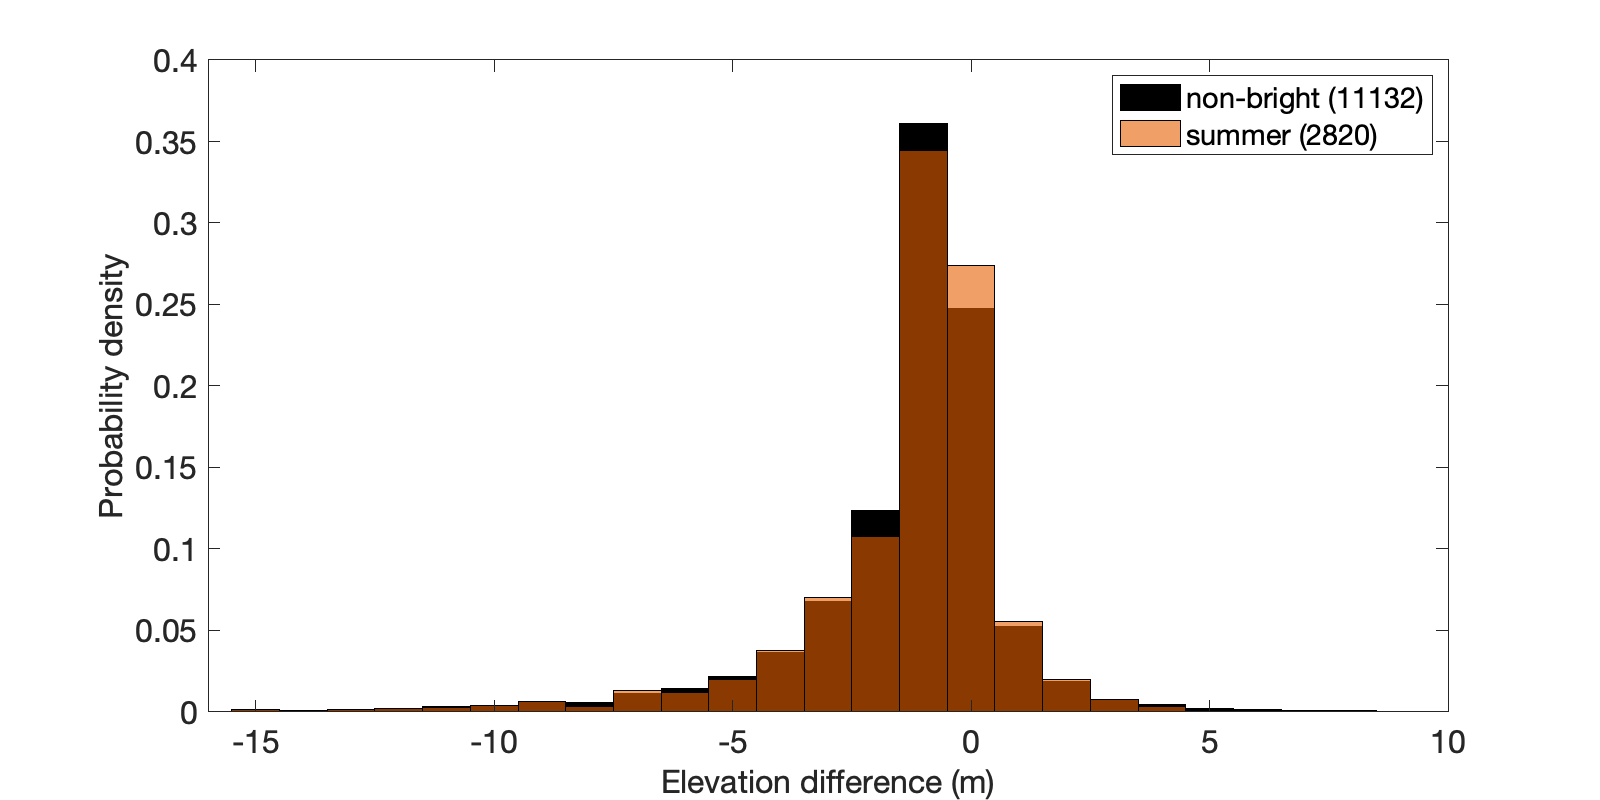

cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);
T = readtable([abbrev,'-ICESat2-',acronym,'-params.csv']); % read in parameters for reynolds creek or RCEW glacier

%uncomment below to display vertical biases
% snowline = 1400; coreg_season = 3; %must know these site-specific parameters
% if coreg_season == 2
%     disp(['Median +/- MAD spring bias = ',num2str(nanmedian(T.VerticalErrors(T.season==coreg_season & T.ReferenceElevation < snowline))),' +/- ',num2str(mad(T.VerticalErrors(T.season==coreg_season & T.ReferenceElevation < snowline),1)),' m'])
% else
%     disp(['Median +/- MAD summer bias = ',num2str(nanmedian(T.VerticalErrors(T.season==coreg_season))),' +/- ',num2str(mad(T.VerticalErrors(T.season==coreg_season),1)),' m'])
% end
% disp(['Vertical bias stats for ALL non-bright footprints = ',num2str(nanmedian(T.VerticalErrors(T.Brightness_Flag==0))),'+/-',num2str(mad(T.VerticalErrors(T.Brightness_Flag==0),1)),' m']);

%create histograms of elevation differences before vertical coregistration
unique_date = unique(T.date); summer_bias = [];
figure; set(gcf,'position',[0 0 800 400]);
h_footprints = histogram(T.VerticalErrors(T.Brightness_Flag==0),[-15.5:1:15.5],'Normalization','pdf'); hold on;
h_summerfeet = histogram(T.VerticalErrors(T.season==3),[-15.5:1:15.5],'Normalization','pdf');
h_footprints.FaceColor = [0 0 0]; h_footprints.FaceAlpha = 1;
h_summerfeet.FaceColor = seas_cmap(2,:);
set(gca,'fontsize',16,'xlim',[-16 10]);
histleg = legend(['non-bright (',num2str(sum(~isnan(T.VerticalErrors(T.Brightness_Flag==0)))),')'],['snow-off (',num2str(sum(~isnan(T.VerticalErrors(T.season==3)))),')']);
ylabel('Probability density','fontsize',16);
xlabel('Elevation difference (m)','fontsize',16); 
saveas(gcf,[abbrev,'-ICESat2-elevation-bias-histograms.eps'],'epsc');

## Load the DEM & catchment outline

%load the DEM
[A,R] = readgeoraster([DTM_path,DTM_name]);
Z.x = R.XWorldLimits(1)+0.5*R.CellExtentInWorldX:R.CellExtentInWorldX:R.XWorldLimits(end)-0.5*R.CellExtentInWorldX; % get a vector of x coords
Z.y = R.YWorldLimits(2)-0.5*R.CellExtentInWorldY:-R.CellExtentInWorldY:R.YWorldLimits(1)+0.5*R.CellExtentInWorldY; % get a vector of y coords
Z.z = double(A); clear A R;
Z.z(Z.z<0) = NaN;

%create a variable used to distinguish data according to year
for j = 1:ceil(range(T.date)); z(j).deciyear = 2018.75+(j-1); end

%load the catchment outline & state outline
cd_to_shp = ['cd ',shapefile_path]; eval(cd_to_shp);
S = shaperead(region_outline);
state = shaperead(state_outline);
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);

## Parse Into Seasons

%parse into seasons
iwin = find(T.season == 1);

filtered outliers


winT = T(iwin, :); % save the table of only winter values
ispr = find(T.season == 2);
sprT = T(ispr, :);
isum = find(T.season == 3);
sumT = T(isum, :);
ifal = find(T.season == 4);
falT = T(ifal, :);

% write seasonally-partitioned tables
writetable(winT, [csv_path,abbrev,'winT.csv']);
writetable(sprT, [csv_path,abbrev,'sprT.csv']);
writetable(sumT, [csv_path,abbrev,'sumT.csv']);
writetable(falT, [csv_path,abbrev,'falT.csv']);
disp('Exported seasonal data to csvs');

## Filter Outliers & Display Basic Statistics

%filter outliers with slopes >3xMAD from the median (Matlab's default outlier filter)

Exported seasonal data to csvs


slope_outliers = isoutlier(T.slope);
T.ruggedness(slope_outliers) = NaN;
T.ReferenceElevation(slope_outliers) = NaN;
T.slope(slope_outliers) = NaN;
T.VegHeight(slope_outliers) = NaN;
T.aspect(slope_outliers) = NaN;
T.differences(slope_outliers) = NaN;
clear slope_outliers;
disp('filtered outliers');

%set-up ranges of each terrain parameter
elev_extremes = isoutlier(T.ReferenceElevation);
elev_x = floor(min(T.ReferenceElevation(elev_extremes~=1))/10)*10:100:ceil(max(T.ReferenceElevation(elev_extremes~=1))/10)*10;
slope_x = 0:5:ceil(max(Tin.slope)/10)*10;
aspect_x = 0:10:360;
% rough_x = 0:1:5; %uncomment here & corresponding lines below if considering a roughness/ruggedness metric
vegheight_x = 0:0.25:2;

%statistics on seasonal elevation differences
disp('Median +/- MAD elevation residuals:')
disp(['Winter = ',num2str(nanmedian(winT.differences)),'+/-',num2str(mad(winT.differences,1))]);
disp(['Spring = ',num2str(nanmedian(sprT.differences)),'+/-',num2str(mad(sprT.differences,1))]);
disp(['Summer = ',num2str(nanmedian(sumT.differences)),'+/-',num2str(mad(sumT.differences,1))]);

Median +/- MAD elevation residuals:


disp(['Fall = ',num2str(nanmedian(falT.differences)),'+/-',num2str(mad(falT.differences,1))]);

Winter = 0.025955+/-0.66855


%split data into just snow-on (Oct-Mar) & snow-off (May-Sept) seasons

Spring = -0.13547+/-0.63638


fprintf('snow-on season = %1.4f +/- %1.4f m',nanmedian(T.differences(T.season == 1 | T.season == 2 | T.season == 4)),mad(T.differences(T.season == 1 | T.season == 2 | T.season == 4),1));

Summer = 0.0010552+/-0.64649


fprintf('snow-off season = %1.4f +/- %1.4f m',nanmedian(T.differences(T.season == 3)),mad(T.differences(T.season == 3),1));

Fall = -0.13981+/-0.66504



%snow identification via the brightness flag
%winter

snow-on season = -0.0417 +/- 0.6709 m

snow-off season = 0.0011 +/- 0.6576 m

disp('Winter snow brightness flagging:')
snow_dates = winT.date(winT.Brightness_Flag==1);
snow_dates = unique(snow_dates);
for i = 1:length(snow_dates)

Winter snow brightness flagging:


    snowy_win(i).date = snow_dates(i);
    snowy_win(i).alldiffs = winT.differences(winT.date==snow_dates(i));
    snowy_win(i).snowydiffs = winT.differences(winT.date==snow_dates(i) & winT.Brightness_Flag==1);
    snowy_win(i).snowfrac = length(snowy_win(i).snowydiffs)./length(snowy_win(i).alldiffs);
    decidate = snowy_win(i).date - floor(snowy_win(i).date);
    if mod(floor(snowy_win(i).date),4) ~= 0
        mo = find(cumdays<=decidate*365,1,'last');
        day = decidate*365-cumdays(mo);
    else
        mo = find(leap_cumdays<=decidate*366,1,'last');
        day = decidate*366-leap_cumdays(mo);
    end
    disp(['Snow on ',num2str(floor(snowy_win(i).date)),'/',num2str(mo),'/',num2str(day),' over ',num2str(snowy_win(i).snowfrac.*100),'% area (avg depth = ',num2str(nanmean(snowy_win(i).snowydiffs)),' m)'])
end

%spring
disp('Spring snow brightness flagging:')

Snow on 2019/1/30 over 4.6429% area (avg depth = 0.99581 m)
Snow on 2020/2/23 over 4.2205% area (avg depth = 0.98521 m)
Snow on 2020/2/26 over 3.103% area (avg depth = 0.85251 m)
Snow on 2021/2/21 over 9.1778% area (avg depth = 0.32649 m)
Snow on 2021/2/23 over 10.7011% area (avg depth = 0.55151 m)


snow_dates = sprT.date(sprT.Brightness_Flag==1);
snow_dates = unique(snow_dates);
if isempty(snow_dates)

Spring snow brightness flagging:


    disp('No snow flagged!')
else
    for i = 1:length(snow_dates)
        snowy_spr(i).date = snow_dates(i);
        snowy_spr(i).alldiffs = sprT.differences(sprT.date==snow_dates(i));
        snowy_spr(i).snowydiffs = sprT.differences(sprT.date==snow_dates(i) & sprT.Brightness_Flag==1);
        snowy_spr(i).snowfrac = length(snowy_spr(i).snowydiffs)./length(snowy_spr(i).alldiffs);
        disp(['Snow on ',num2str(snowy_spr(i).date),' over ',num2str(snowy_spr(i).snowfrac.*100),'% area (avg depth = ',num2str(nanmean(snowy_spr(i).snowydiffs)),' m)'])
    end
end

No snow flagged!


## Plot Histograms of Elevation Residuals

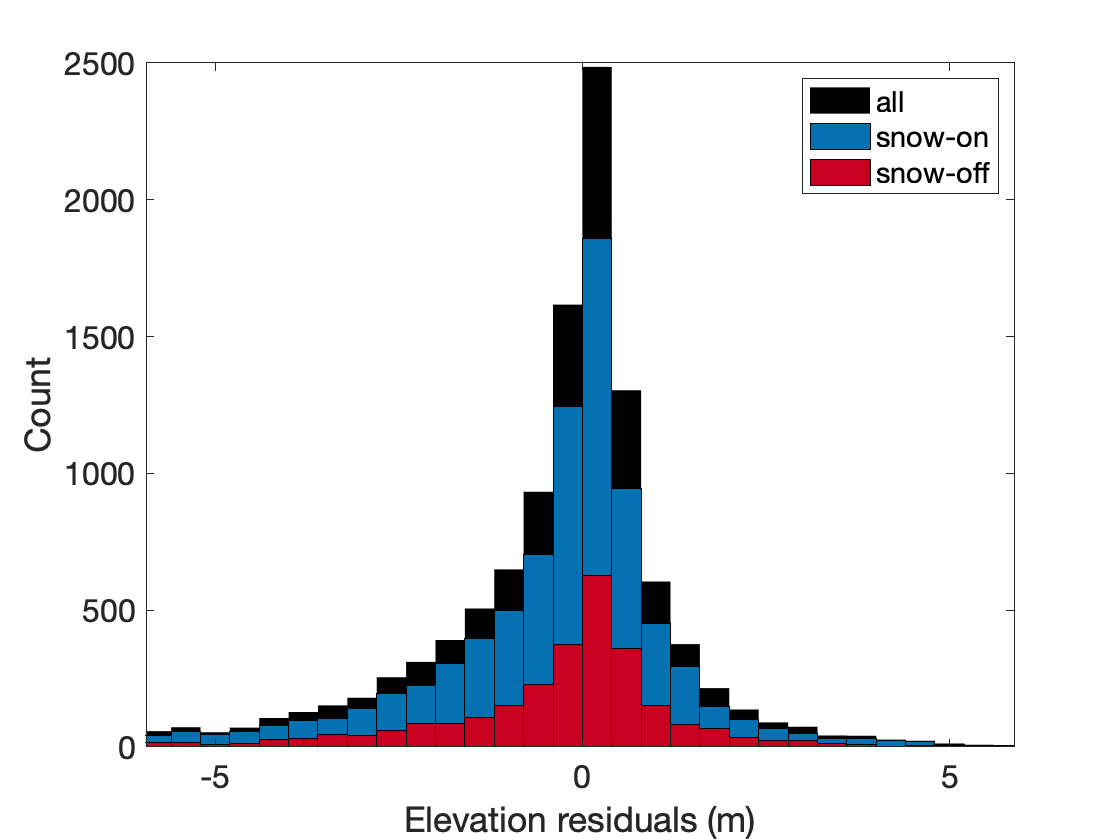

cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);

%specify the histogram bin width
binwidth = 0.4;

%set plot bounds
max_diff = max([nanmedian(T.differences)+6*1.4826*mad(T.differences,1),abs(nanmedian(T.differences)-6*1.4826*mad(T.differences,1))]);

%identify snow-on and snow-off data
acc_diff = T.differences(T.season == 1 | T.season == 2 | T.season == 4); acc_date = T.date(T.season == 1 | T.season == 2 | T.season == 4); 
abl_diff = T.differences(T.season == 3); abl_date = T.date(T.season == 3); 

%plot the histograms
figure;
h(1) = histogram(T.differences); h(1).BinWidth = binwidth; h(1).FaceColor = [0 0 0]; h(1).FaceAlpha = 1; h(1).EdgeColor = 'none'; hold on;
h(2) = histogram(acc_diff); h(2).BinWidth = binwidth; h(2).FaceColor = seas_cmap(1,:); h(2).FaceAlpha = 1;  h(2).EdgeColor = 'k'; hold on;
h(3) = histogram(abl_diff); h(3).BinWidth = binwidth; h(3).FaceColor = seas_cmap(2,:); h(3).FaceAlpha = 1;  h(3).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16,'xlim',[nanmedian(T.differences)-6*1.4826*mad(T.differences,1) nanmedian(T.differences)+6*1.4826*mad(T.differences,1)]); 
leg = legend(h,'all','snow-on','snow-off');
xlabel('Elevation residuals (m)'); ylabel('Count');
saveas(gcf,[abbrev,'_ICESat2residual_histograms.eps'],'epsc');


%histogram subplots according to hydrologic or mass balance year
figure; set(gcf,'position',[50 50 800 1000]); clear h;
for i = 1:length(z)
    subplot(length(z),1,i);
    h(1) = histogram(acc_diff(ceil(acc_date-z(i).deciyear)==1),'Normalization','pdf'); h(1).BinWidth = binwidth; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 1;  h(1).EdgeColor = 'k'; hold on;
    h(2) = histogram(abl_diff(ceil(abl_date-z(i).deciyear)==1),'Normalization','pdf'); h(2).BinWidth = binwidth; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
    set(gca,'fontsize',16,'xlim',[nanmedian(T.differences)-6*1.4826*mad(T.differences,1) nanmedian(T.differences)+6*1.4826*mad(T.differences,1)]); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
    if mod(floor(z(i).deciyear),4) ~= 0
        text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), [alphabet(i),') ',num2str(floor(z(i).deciyear)),'-',num2str(ceil(z(i).deciyear))], 'fontsize', 14)
    else
        text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), [alphabet(i),') ',num2str(floor(z(i).deciyear)),'-',num2str(ceil(z(i).deciyear))], 'fontsize', 14)
    end
    disp('Data for dates: ')
    alldates = T.date(ceil(T.date-z(i).deciyear)==1); alldates = unique(alldates);
    for j = 1:length(alldates)
        if mod(floor(alldates(j)),4) ~= 0
            disp([num2str(floor(alldates(j))),'/',num2str(find(cumdays<=(alldates(j)-floor(alldates(j)))*365,1,'last')),'/',num2str((alldates(j)-floor(alldates(j)))*365-cumdays(find(cumdays<=(alldates(j)-floor(alldates(j)))*365,1,'last')))]);
        else
            disp([num2str(floor(alldates(j))),'/',num2str(find(cumdays<=(alldates(j)-floor(alldates(j)))*366,1,'last')),'/',num2str((alldates(j)-floor(alldates(j)))*366-cumdays(find(cumdays<=(alldates(j)-floor(alldates(j)))*366,1,'last')))]);
        end
    end
    clear alldates;
    
    %statistics on seasonal elevation differences
    disp(['Median +/- MAD elevation residuals relative to: ',num2str(floor(z(i).deciyear)),'/',num2str(find(cumdays<=(z(i).deciyear-floor(z(i).deciyear))*365,1,'last')),'/',num2str((z(i).deciyear-floor(z(i).deciyear))*365-cumdays(find(cumdays<=(z(i).deciyear-floor(z(i).deciyear))*365,1,'last')))])
    fprintf('Snow-on median +/- MAD elevation residuals= %1.3f +/- %1.3f m',nanmedian(acc_diff(ceil(acc_date-z(i).deciyear)==1)),mad(acc_diff(ceil(acc_date-z(i).deciyear)==1),1));
    fprintf('Snow-off median +/- MAD elevation residuals= %1.3f +/- %1.3f m',nanmedian(abl_diff(ceil(abl_date-z(i).deciyear)==1)),mad(abl_diff(ceil(abl_date-z(i).deciyear)==1),1));
    
end

Data for dates: 


2018/11/26
2019/1/30
2019/2/25
2019/5/1
2019/5/27
2019/7/30
2019/8/26
2019/8/28


Median +/- MAD elevation residuals relative to: 2018/10/0.75


Snow-on median +/- MAD elevation residuals= -0.215 +/- 0.907 m

Snow-off median +/- MAD elevation residuals= 0.027 +/- 0.627 m

Data for dates: 


2019/10/29
2019/11/25


2020/1/26
2020/2/23
2020/2/26
2020/4/29
2020/5/25
2020/8/24
2020/8/27


Median +/- MAD elevation residuals relative to: 2019/10/0.75


Snow-on median +/- MAD elevation residuals= -0.081 +/- 0.652 m

Snow-off median +/- MAD elevation residuals= -0.183 +/- 0.712 m

Data for dates: 


2020/10/27
2020/11/23
2020/12/22


2021/1/23
2021/2/21
2021/2/23


Median +/- MAD elevation residuals relative to: 2020/10/0.75


Snow-on median +/- MAD elevation residuals= 0.054 +/- 0.644 m

Snow-off median +/- MAD elevation residuals= NaN +/- NaN m

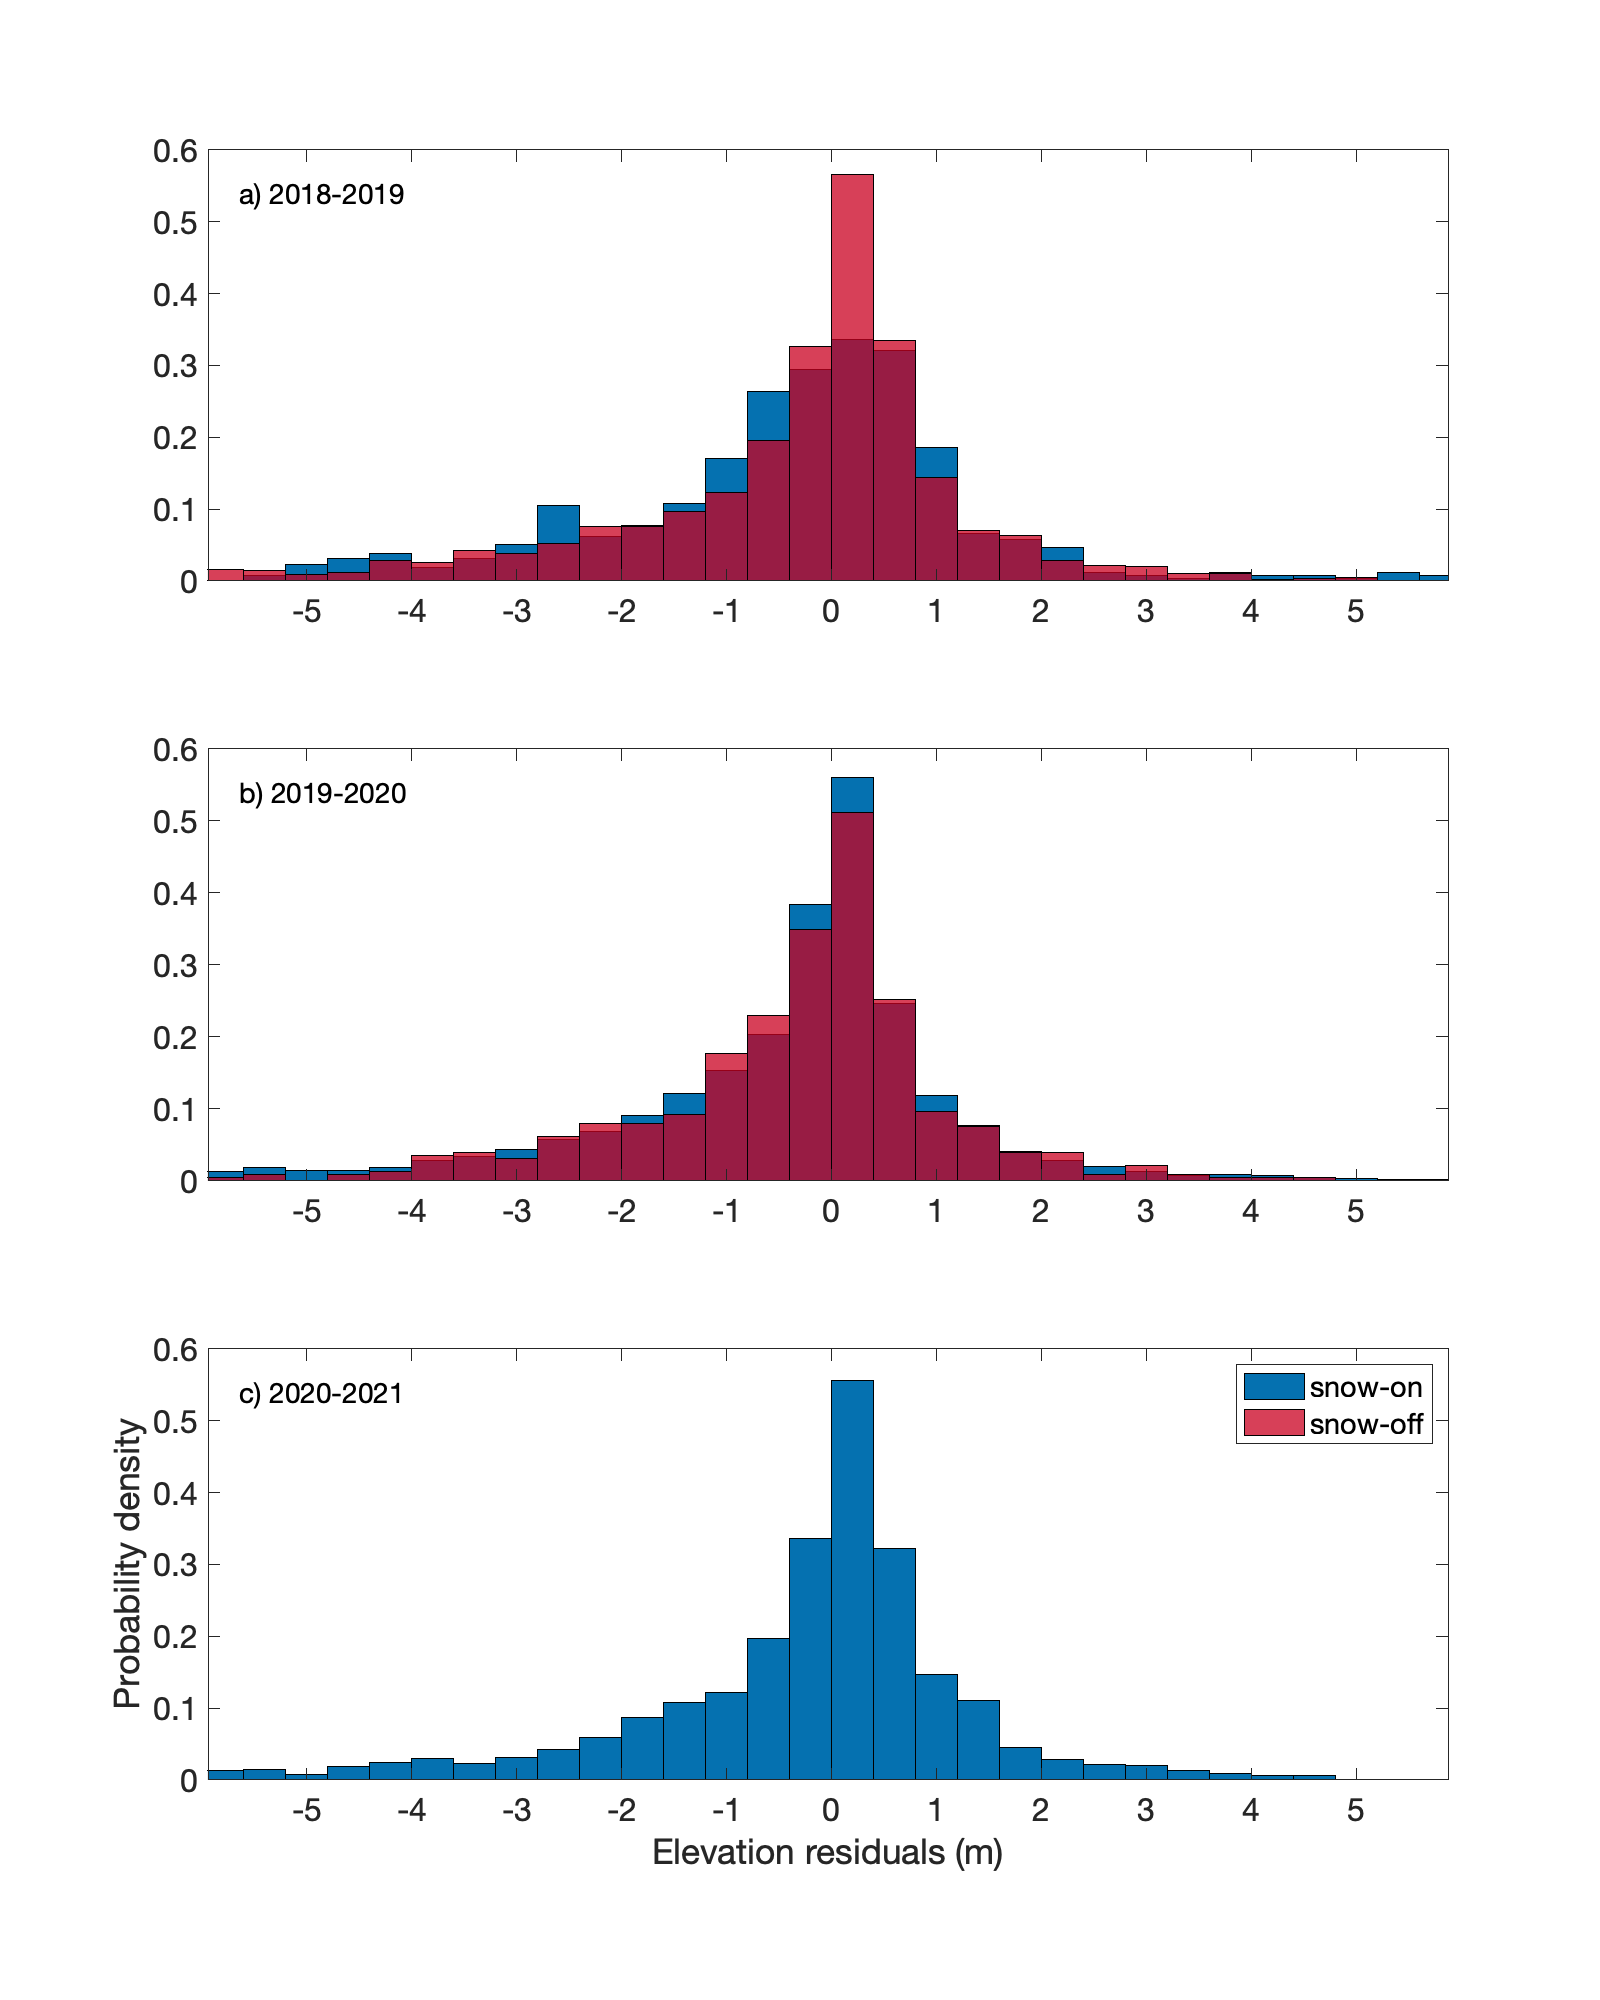

% leg = legend(h,'summer','autumn','winter','spring');
leg = legend(h,'snow-on','snow-off');
xlabel('Elevation residuals (m)'); ylabel('Probability density');
saveas(gcf,[abbrev,'_annual-ICESat2residual_histograms.eps'],'epsc');


%determine whether the histograms for each season are significantly different from the summer histogram using the
%two-sample Kolmogorov-Smirnov test (kstest function in Matlab)
disp('Assessing significance of elevation residuals wrt summer data')

Assessing significance of elevation residuals wrt summer data


for i = 2018:1:2020
    disp(num2str(i))
    %winter
    if sum(~isnan(winT.differences(ceil(winT.date-i)==1))) > 0
        win_sigtest = kstest2(winT.differences(ceil(winT.date-i)==1),sumT.differences);
        if win_sigtest == 1; disp('winter = significantly different'); else; disp('winter = not significantly different'); end
    end
    %spring
    if sum(~isnan(sprT.differences(ceil(sprT.date-i)==1))) > 0
        spr_sigtest = kstest2(sprT.differences(ceil(sprT.date-i)==1),sumT.differences);
        if spr_sigtest == 1; disp('spring = significantly different'); else; disp('spring = not significantly different'); end
    end
    %fall
    if sum(~isnan(falT.differences(ceil(falT.date-i)==1))) > 0
        fal_sigtest = kstest2(falT.differences(ceil(falT.date-i)==1),sumT.differences);
        if fal_sigtest == 1; disp('fall = significantly different'); else; disp('fall = not significantly different'); end
    end
end

2018


fall = significantly different


2019


winter = significantly different


spring = not significantly different


fall = significantly different


2020


winter = not significantly different


spring = significantly different


fall = significantly different


## Create Boxplots of Elevation Residuals With Respect To Terrain Parameters

Residuals vs. elevation R^2: 1st-degree = 0.43846 & 2nd-degree = 0.65584


Residuals vs. slope R^2: 1st-degree = 0.93461 & 2nd-degree = 0.95688


Residuals vs. aspect parabolic R^2 = 0.81301


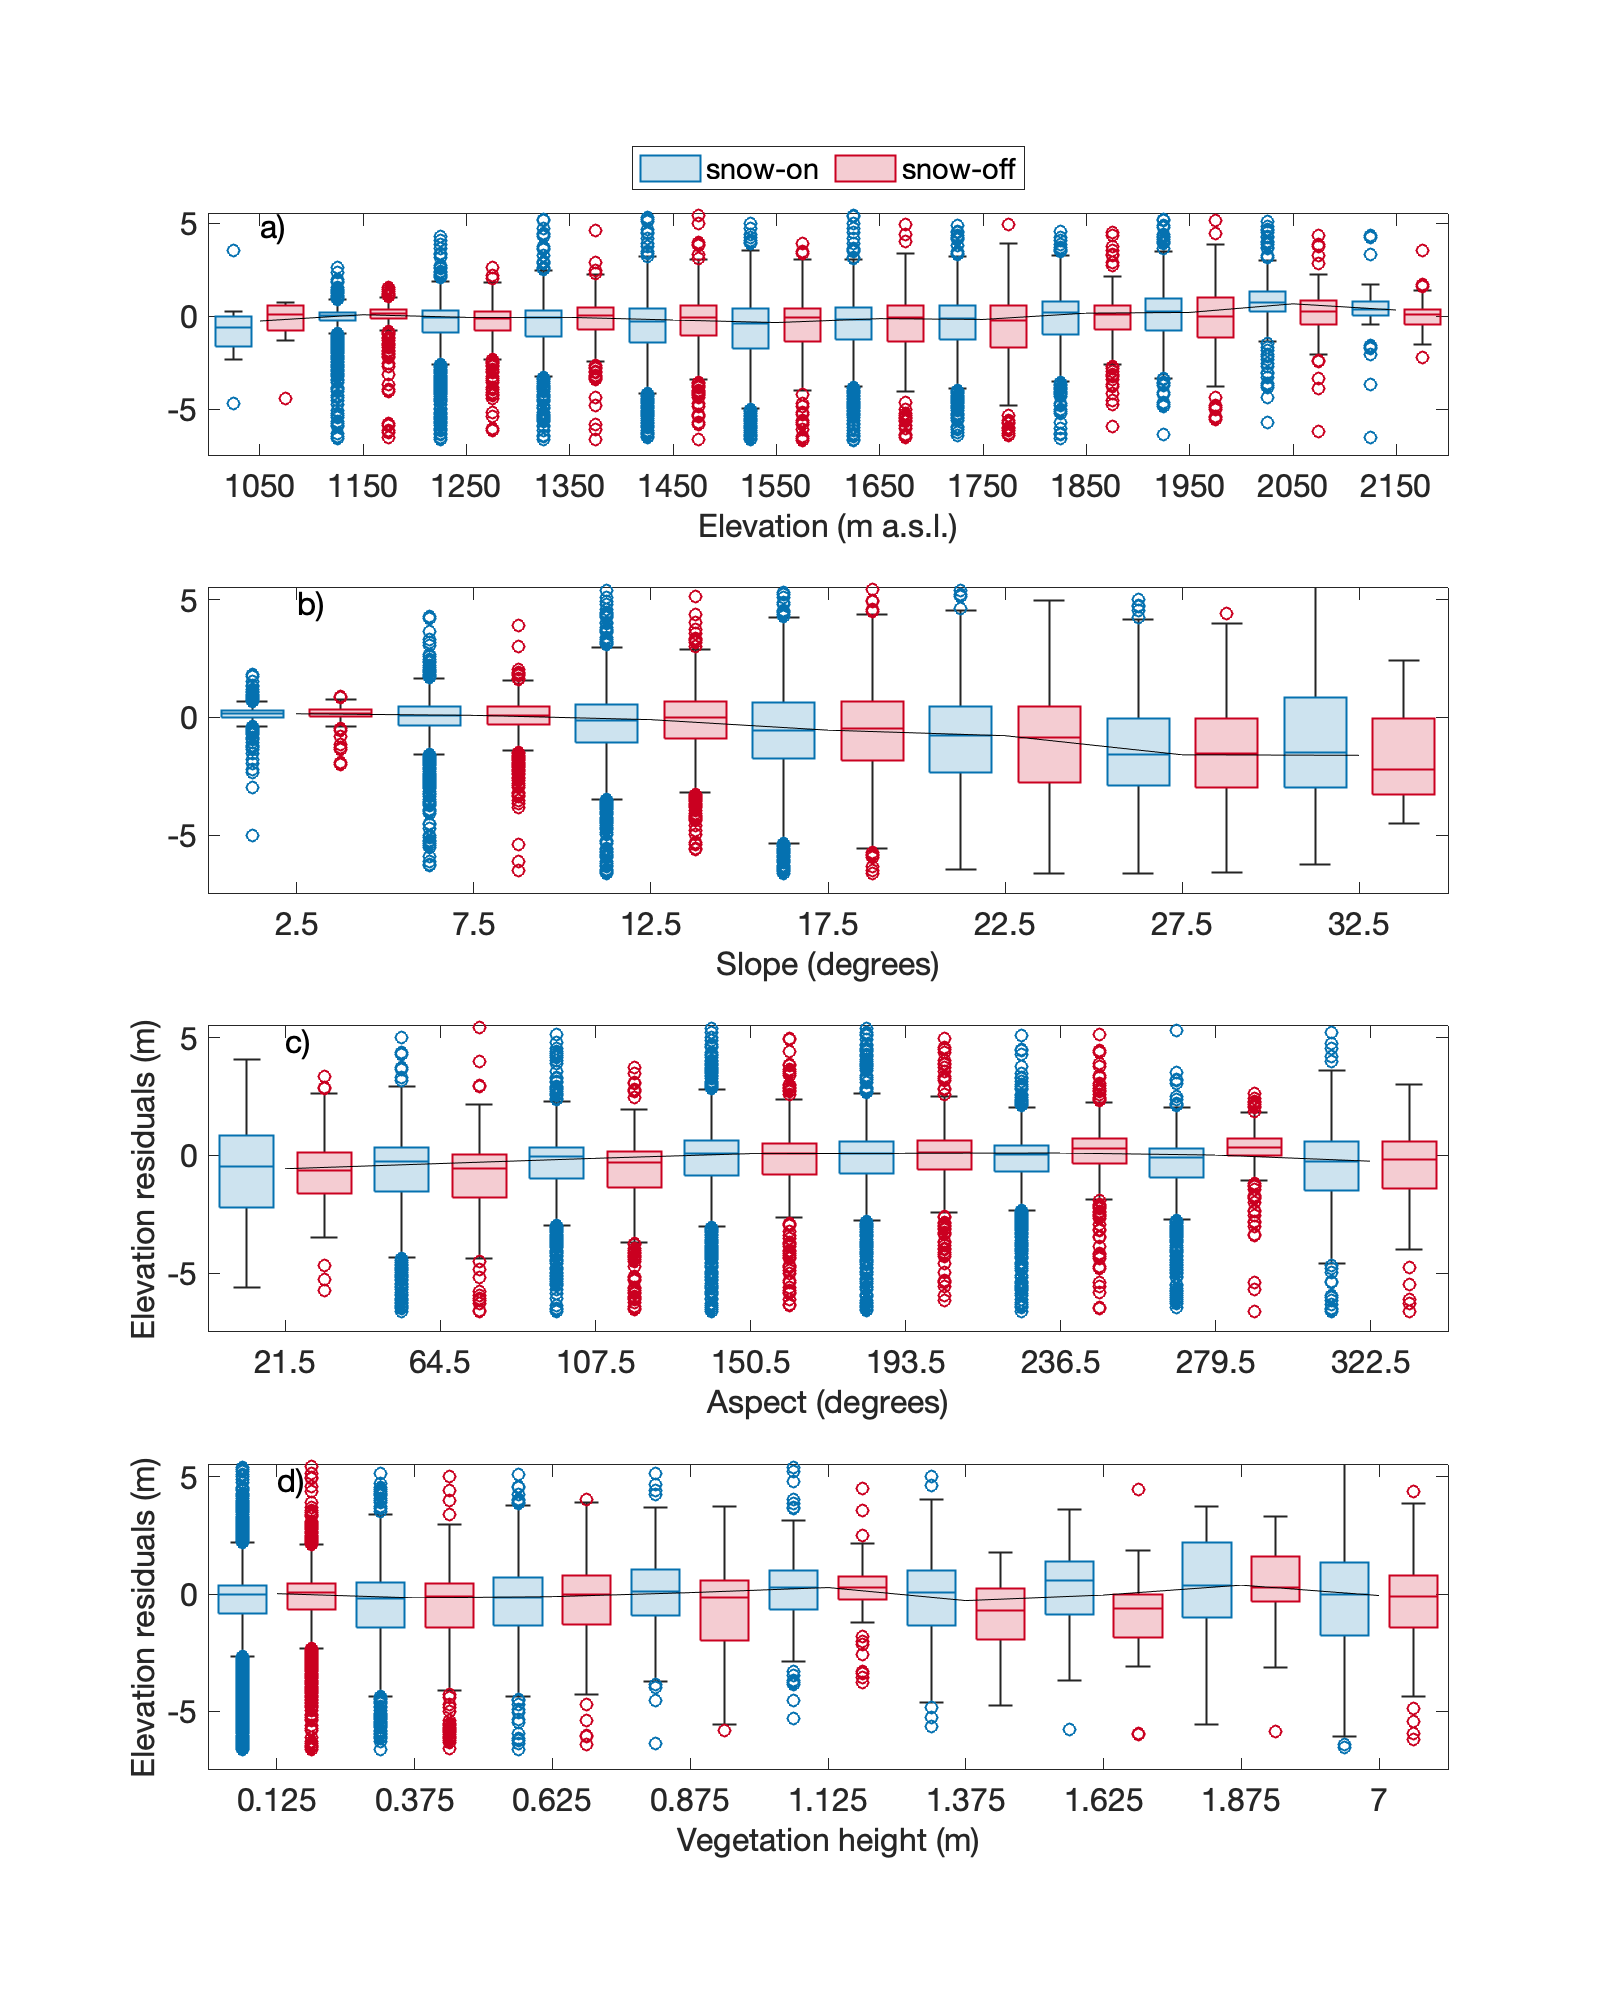

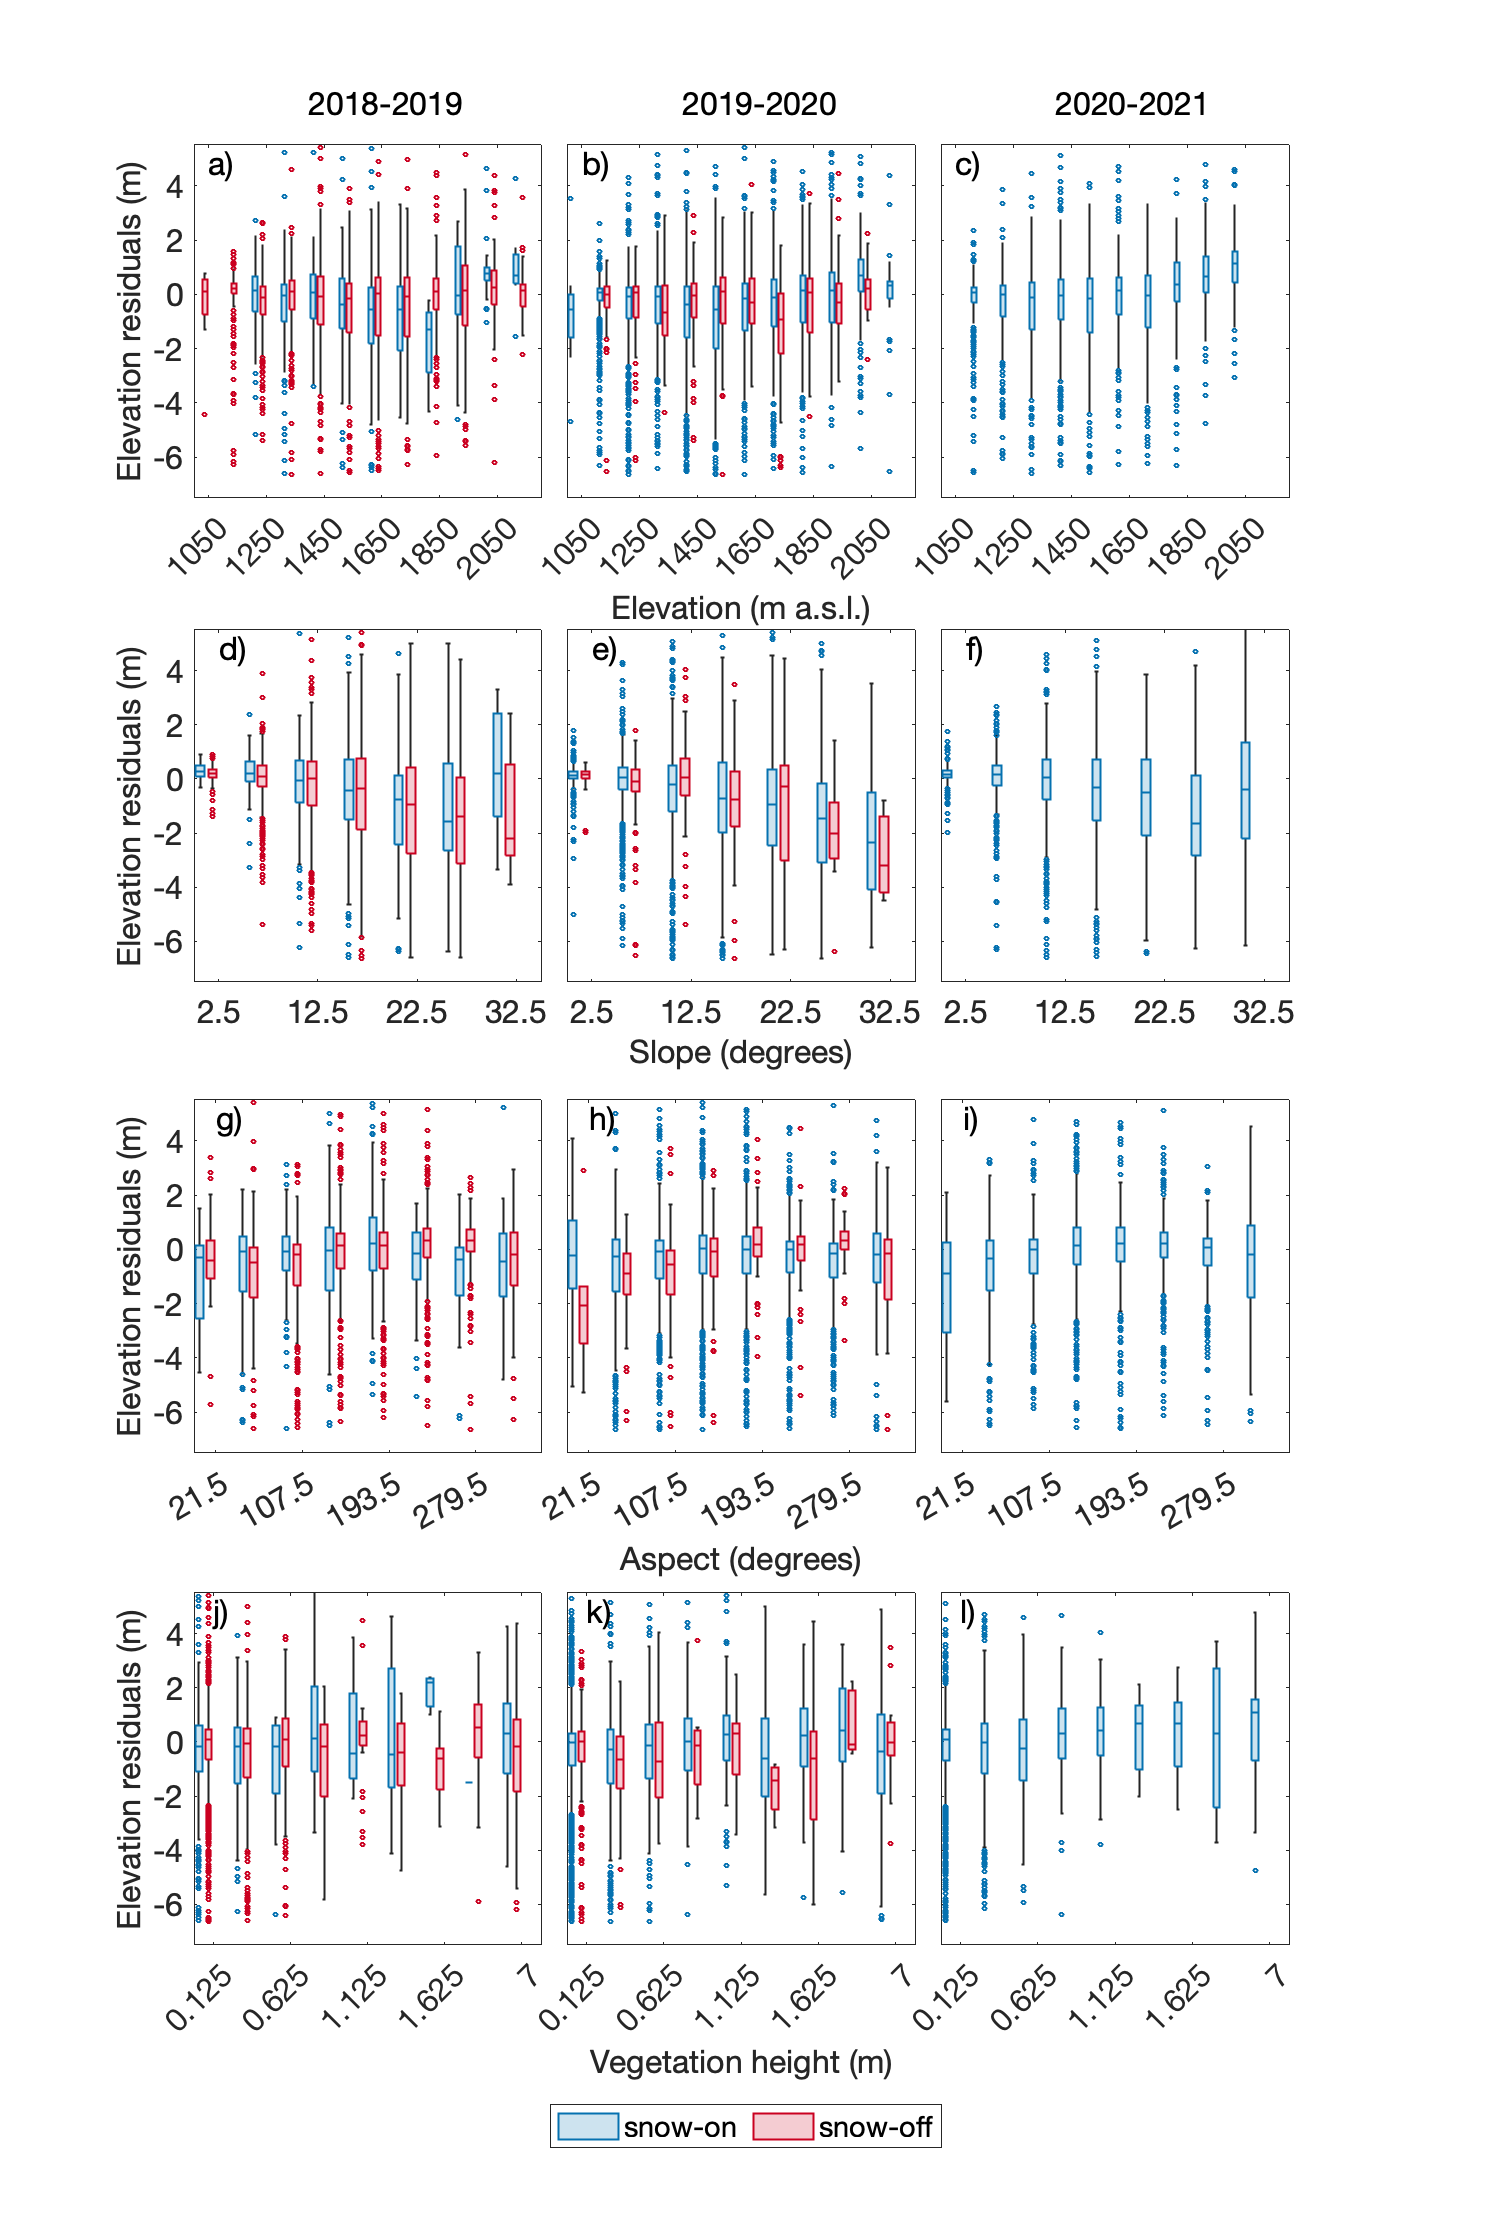

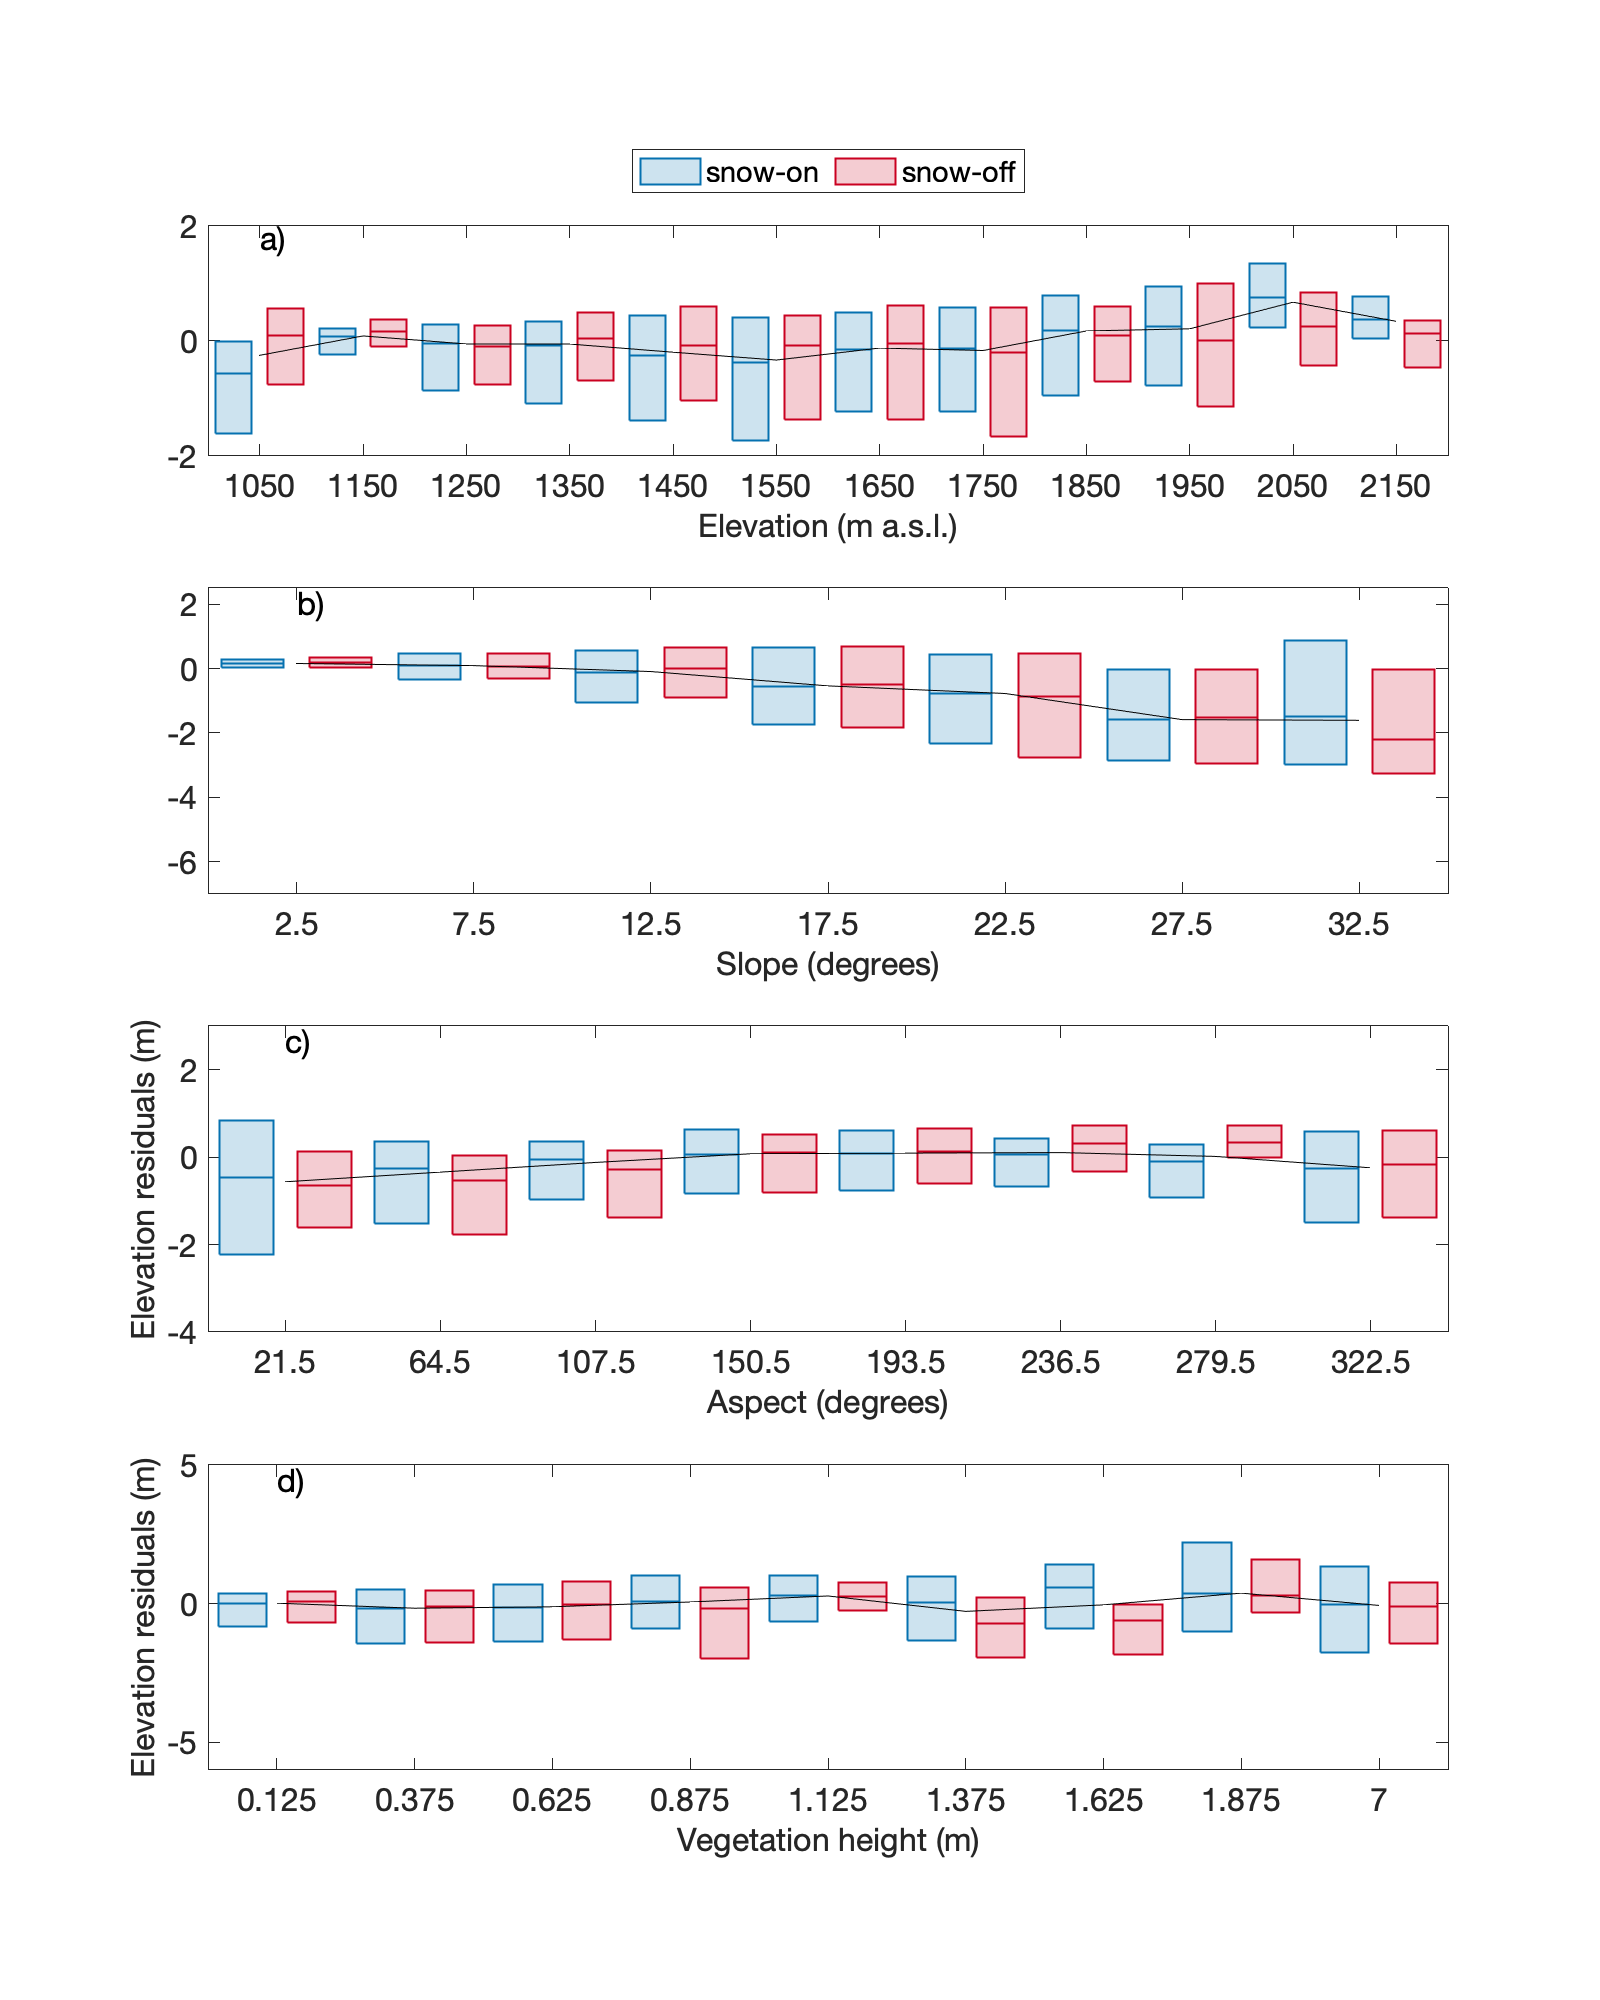

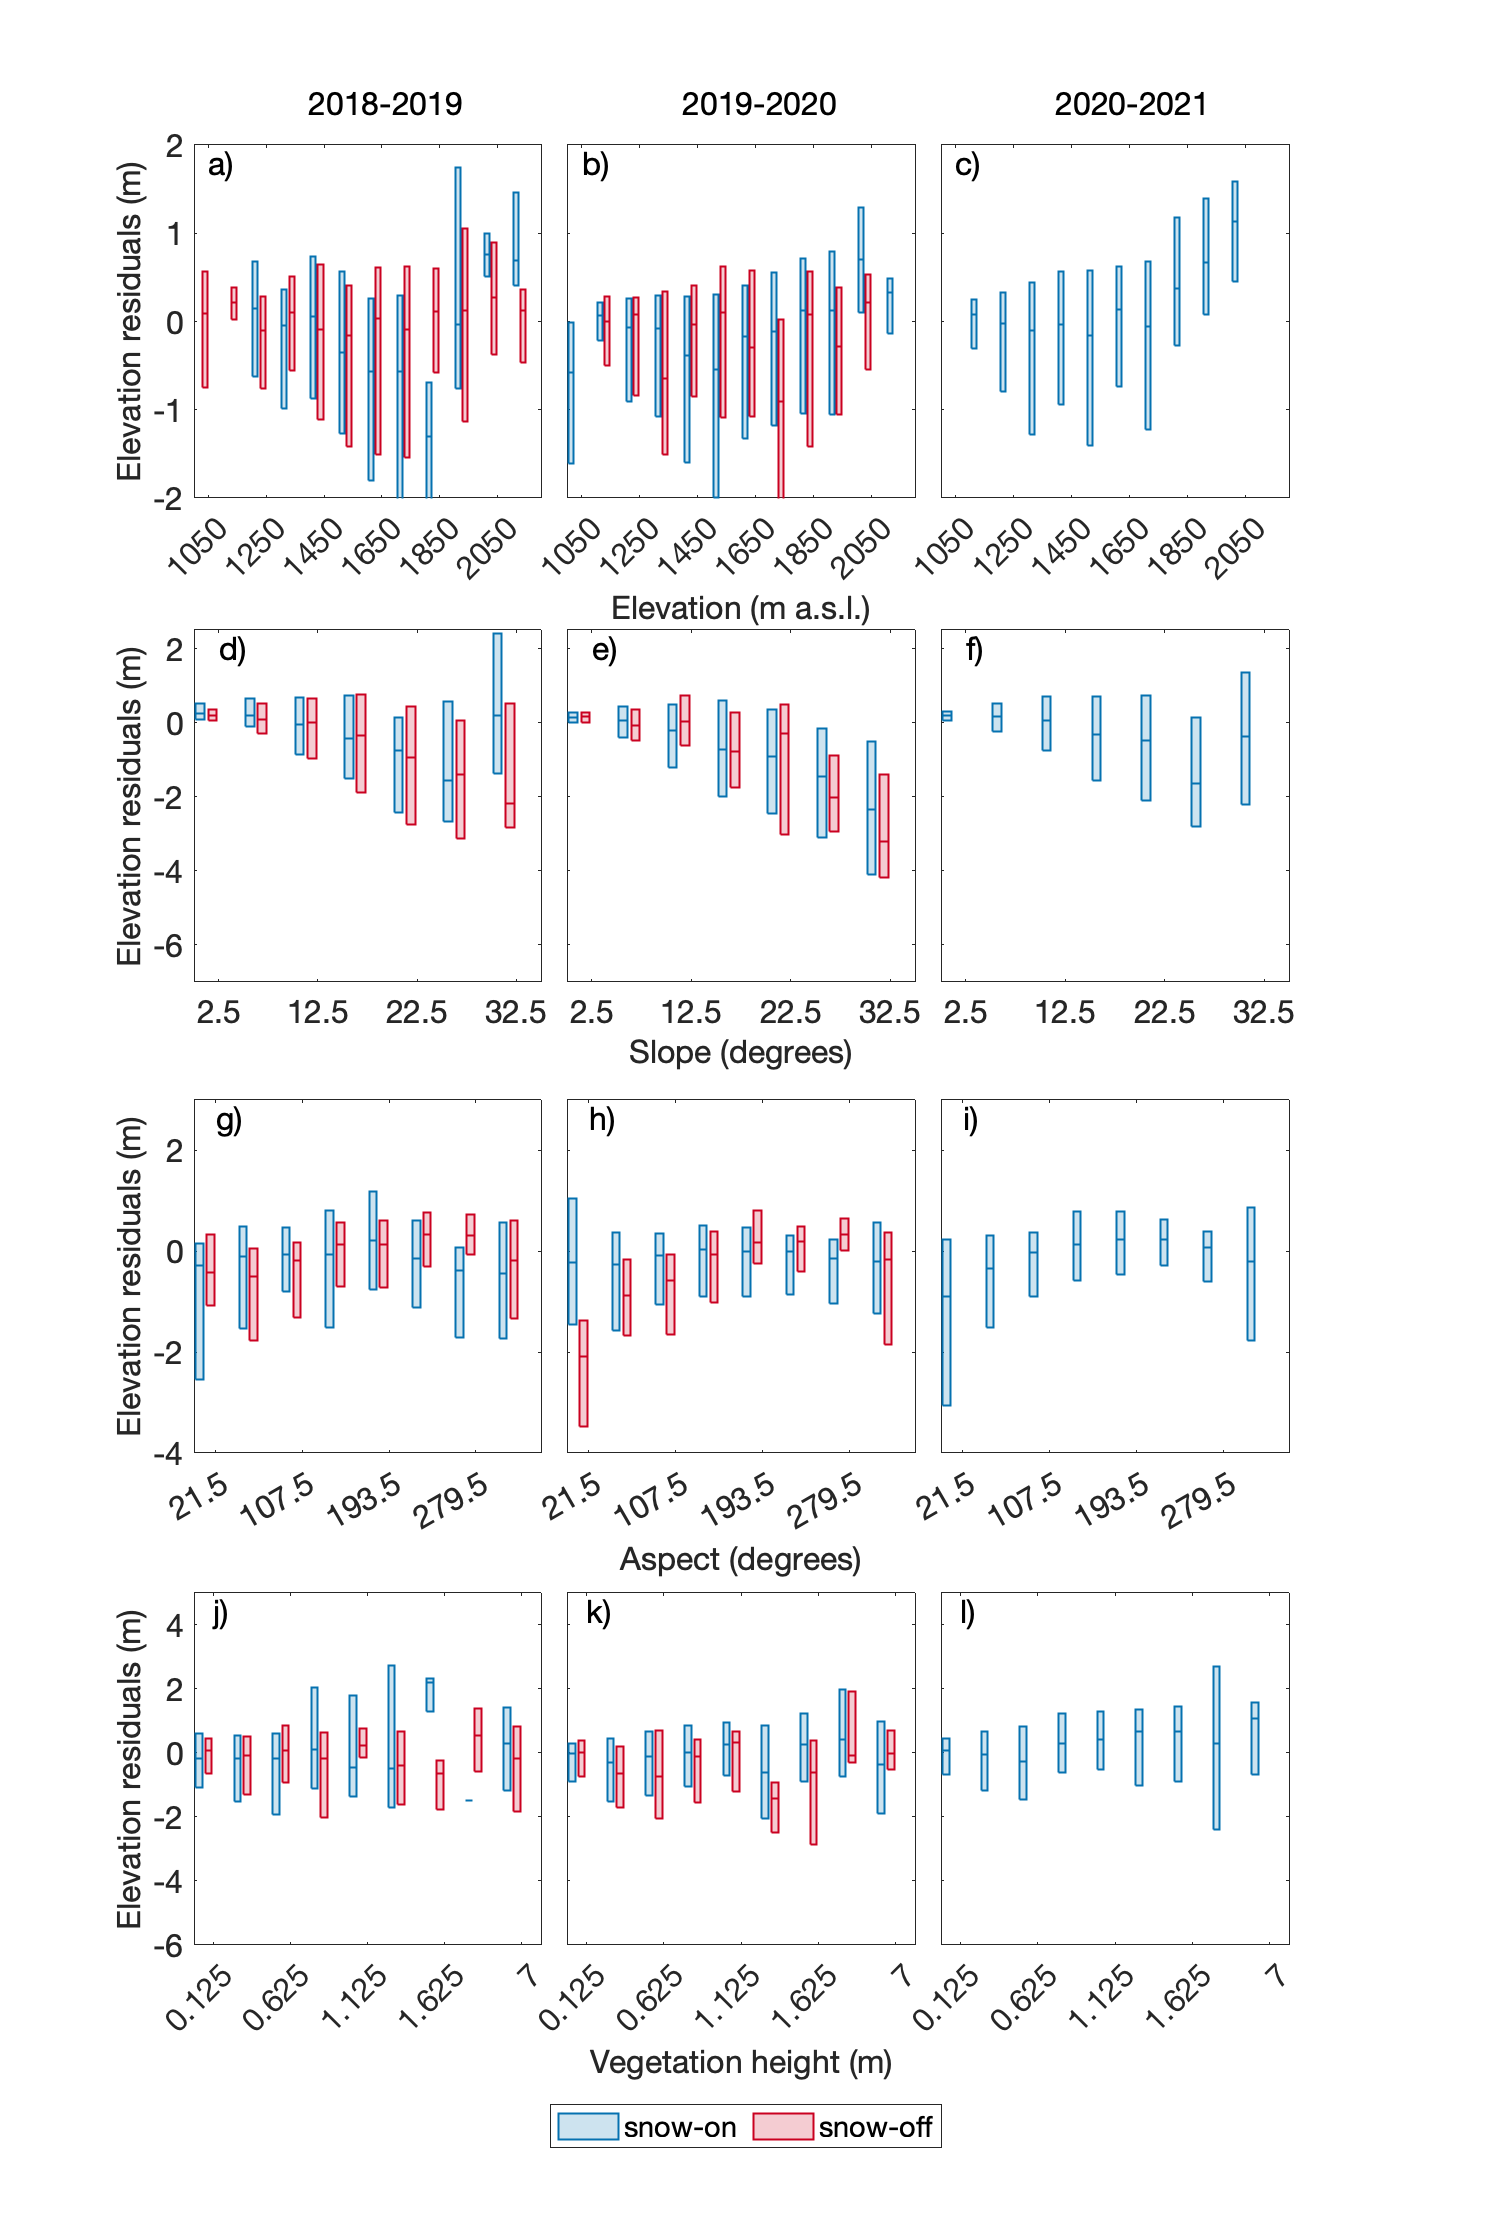

%uncomment while loops to automatically determine bin widths for each parameter by identifying the
%bin width that yields >100 observations for the complete dataset
%ELEVATION
h = histogram(T.ReferenceElevation(~isnan(T.differences)),[floor(min(elev_x)/100)*100:100:ceil(max(elev_x)/100)*100]);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
        elev_binwidth = h.BinWidth; elev_binedges = h.BinEdges;
        clear h;
%         break
%     end
% end
close(gcf);
%SLOPE
h = histogram(T.slope(~isnan(T.differences)),[0:5:max(slope_x)]);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
        slope_binwidth = h.BinWidth; slope_binedges = h.BinEdges;
        clear h;
%         break
%     end
% end
close(gcf);
%ASPECT
h = histogram(T.aspect(~isnan(T.differences)),8);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
        aspect_binwidth = h.BinWidth; aspect_binedges = h.BinEdges;
        clear h;
%         break
%     end
% end
close(gcf);
%VEGETATION HEIGHT
h = histogram(T.VegHeight(~isnan(T.differences)),[vegheight_x ceil(max(T.VegHeight))]);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
        vegheight_binwidth = h.BinWidth; vegheight_binedges = h.BinEdges;
        clear h;
%         break
%     end
% end
close(gcf);

%create boxplot colormaps
% boxplot_cmap = [wincolor; sprcolor; sumcolor; falcolor];
boxplot_cmap = seas_cmap;

%create boxcharts w/ and w/o whiskers+outliers
for p = 1:2
    
    %specify parameters
    if p == 1
        whiskerline = '-'; outliermarker = 'o';
        resid_ylims = [-7.5 5.5]; resid_elev_ylims = resid_ylims; 
        resid_slope_ylims = resid_ylims; resid_aspect_ylims = resid_ylims; 
        resid_vegheight_ylims = resid_ylims; 
    else
        whiskerline = 'none'; outliermarker = 'none';
        resid_ylims = [-3.5 2.5]; resid_elev_ylims = [-2 2]; 
        resid_slope_ylims = [-7 2.5]; resid_aspect_ylims = [-4 3]; 
        resid_vegheight_ylims = [-6 5]; 
    end
    
    
    %create boxcharts for each terrain parameter
    figure('position', [0 0 800 1000]);
    plot_boxwidth = 0.7; 
    %ELEVATION
    subplot(4,1,1);
    elev_binflag = zeros(size(T.differences,1),1);
    for j = 1:length(elev_binedges)-1
        binref = find(T.ReferenceElevation>=elev_binedges(j) & T.ReferenceElevation<elev_binedges(j+1));
        elev_binflag(binref,1) = nanmean(elev_binedges(j:j+1)); clear binref;
    end
    resids_elev = T.differences(elev_binflag>0); elev_seasflag = T.season(elev_binflag>0); elev_binflag(elev_binflag==0) = [];
    elev_seasflag(isnan(resids_elev)) = []; elev_binflag(isnan(resids_elev)) = []; resids_elev(isnan(resids_elev)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    elev_seasflag(elev_seasflag == 1 | elev_seasflag == 2 | elev_seasflag == 4) = 1; elev_seasflag(elev_seasflag == 3) = 2;
    %filter crazy outliers
    resids_elev(resids_elev > nanmedian(T.differences)+10*mad(T.differences,1)) = NaN;
    resids_elev(resids_elev < nanmedian(T.differences)-10*mad(T.differences,1)) = NaN;
    b = boxchart(categorical(elev_binflag),resids_elev(:,1),'GroupByColor',elev_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_elev(:,1),categorical(elev_binflag),'median');
    plot(medianresid,'-','color','k'); hold off; elevbin = unique(elev_binflag);
    if p == 1
        [~,gof1] = fit(elevbin(~isnan(medianresid)),medianresid(~isnan(medianresid)),'poly1'); [~,gof2] = fit(elevbin(~isnan(medianresid)),medianresid(~isnan(medianresid)),'poly2');
        disp(['Residuals vs. elevation R^2: 1st-degree = ',num2str(gof1.rsquare),' & 2nd-degree = ',num2str(gof2.rsquare)]);
        clear gof1 gof2;
    end
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_elev_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
%     leg = legend('winter','spring','summer','autumn','location','northoutside','orientation','horizontal');
    leg = legend('snow-on','snow-off','location','northoutside','orientation','horizontal');
    xlabel('Elevation (m a.s.l.)','fontsize',16); %ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'a)','fontsize',16);
    %SLOPE
    subplot(4,1,2);
    slope_binflag = zeros(size(T.differences,1),1);
    for j = 1:length(slope_binedges)-1
        binref = find(T.slope>=slope_binedges(j) & T.slope<slope_binedges(j+1));
        slope_binflag(binref,1) = nanmean(slope_binedges(j:j+1)); clear binref;
    end
    resids_slope = T.differences(slope_binflag>0); slope_seasflag = T.season(slope_binflag>0); slope_binflag(slope_binflag==0) = [];
    slope_seasflag(isnan(resids_slope)) = []; slope_binflag(isnan(resids_slope)) = []; resids_slope(isnan(resids_slope)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    slope_seasflag(slope_seasflag == 1 | slope_seasflag == 2 | slope_seasflag == 4) = 1; slope_seasflag(slope_seasflag == 3) = 2;
    %filter crazy outliers
    resids_slope(resids_slope > nanmedian(T.differences)+10*mad(T.differences,1)) = NaN;
    resids_slope(resids_slope < nanmedian(T.differences)-10*mad(T.differences,1)) = NaN;
    b = boxchart(categorical(slope_binflag),resids_slope(:,1),'GroupByColor',slope_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_slope(:,1),categorical(slope_binflag),'median');
    plot(medianresid,'-','color','k'); hold off; slopebin = unique(slope_binflag);
    if p == 1
        [~,gof1] = fit(slopebin(~isnan(medianresid)),medianresid(~isnan(medianresid)),'poly1'); [~,gof2] = fit(slopebin(~isnan(medianresid)),medianresid(~isnan(medianresid)),'poly2');
        disp(['Residuals vs. slope R^2: 1st-degree = ',num2str(gof1.rsquare),' & 2nd-degree = ',num2str(gof2.rsquare)]);
        clear gof1 gof2;
    end
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_slope_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
    % leg = legend('winter','spring','summer','autumn','location','southeast');
    xlabel('Slope (degrees)','fontsize',16); %ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'b)','fontsize',16);
    %ASPECT
    subplot(4,1,3);
    aspect_binflag = zeros(size(T.differences,1),1);
    for j = 1:length(aspect_binedges)-1
        binref = find(T.aspect>=aspect_binedges(j) & T.aspect<aspect_binedges(j+1));
        aspect_binflag(binref,1) = nanmean(aspect_binedges(j:j+1)); clear binref;
    end
    resids_aspect = T.differences(aspect_binflag>0); aspect_seasflag = T.season(aspect_binflag>0); aspect_binflag(aspect_binflag==0) = [];
    aspect_seasflag(isnan(resids_aspect)) = []; aspect_binflag(isnan(resids_aspect)) = []; resids_aspect(isnan(resids_aspect)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    aspect_seasflag(aspect_seasflag == 1 | aspect_seasflag == 2 | aspect_seasflag == 4) = 1; aspect_seasflag(aspect_seasflag == 3) = 2;
    %filter crazy outliers
    resids_aspect(resids_aspect > nanmedian(T.differences)+10*mad(T.differences,1)) = NaN;
    resids_aspect(resids_aspect < nanmedian(T.differences)-10*mad(T.differences,1)) = NaN;
    b = boxchart(categorical(aspect_binflag),resids_aspect(:,1),'GroupByColor',aspect_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_aspect(:,1),categorical(aspect_binflag),'median');
    plot(medianresid,'-','color','k'); hold off; 
    if p == 1
    [~,gof1] = fit(unique(aspect_binflag),medianresid,ft2);
    disp(['Residuals vs. aspect parabolic R^2 = ',num2str(gof1.rsquare)]);
    clear gof1;
    end
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_aspect_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
    xlabel('Aspect (degrees)','fontsize',16); ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'c)','fontsize',16);
    %VEGETATION HEIGHT
    subplot(4,1,4);
    aspect_binflag = zeros(size(T.differences,1),1);
    for j = 1:length(vegheight_binedges)-1
        binref = find(T.VegHeight>=vegheight_binedges(j) & T.VegHeight<vegheight_binedges(j+1));
        vegheight_binflag(binref,1) = nanmean(vegheight_binedges(j:j+1)); clear binref;
    end
    resids_vegheight = T.differences(vegheight_binflag>0); vegheight_seasflag = T.season(vegheight_binflag>0); vegheight_binflag(vegheight_binflag==0) = [];
    vegheight_seasflag(isnan(resids_vegheight)) = []; vegheight_binflag(isnan(resids_vegheight)) = []; resids_vegheight(isnan(resids_vegheight)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    vegheight_seasflag(vegheight_seasflag == 1 | vegheight_seasflag == 2 | vegheight_seasflag == 4) = 1; vegheight_seasflag(vegheight_seasflag == 3) = 2;
    %filter crazy outliers
    resids_vegheight(resids_vegheight > nanmedian(T.differences)+10*mad(T.differences,1)) = NaN;
    resids_vegheight(resids_vegheight < nanmedian(T.differences)-10*mad(T.differences,1)) = NaN;
    b = boxchart(categorical(vegheight_binflag),resids_vegheight(:,1),'GroupByColor',vegheight_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_vegheight(:,1),categorical(vegheight_binflag),'median');
    plot(medianresid,'-','color','k'); hold off; clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_vegheight_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
    xlabel('Vegetation height (m)','fontsize',16); ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'d)','fontsize',16);
    %save figure
    if p == 1
        saveas(gcf,[abbrev,'_ICESat2residuals-vs-terrain_boxplots.eps'],'epsc');
    else
        saveas(gcf,[abbrev,'_ICESat2residuals-vs-terrain_whiskerless-boxplots.eps'],'epsc');
    end
    
    
    %divide according to year as well (subplot rows = parameters, columns = years of data)
    figure('Position',[0 0 800 1200]);
    subplot_boxwidth = 0.7; subplot_markersize = 2;
    %ELEVATION
    elev_binflag = zeros(size(T.differences,1),1);
    for j = 1:length(elev_binedges)-1
        binref = find(T.ReferenceElevation>=elev_binedges(j) & T.ReferenceElevation<elev_binedges(j+1));
        elev_binflag(binref,1) = nanmean(elev_binedges(j:j+1)); clear binref;
    end
    resids_elev = T.differences(elev_binflag~=0); elev_seasflag = T.season(elev_binflag~=0); elev_binflag(elev_binflag==0) = [];
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    elev_seasflag(elev_seasflag == 1 | elev_seasflag == 2 | elev_seasflag == 4) = 1; elev_seasflag(elev_seasflag == 3) = 2;
    %filter crazy outliers
    resids_elev(resids_elev > nanmedian(T.differences)+10*mad(T.differences,1)) = NaN;
    resids_elev(resids_elev < nanmedian(T.differences)-10*mad(T.differences,1)) = NaN;
    for j = 1:length(z)
        dyear = T.date(elev_binflag~=0) - z(j).deciyear;
        resids_elev_annual = resids_elev(ceil(dyear)==1); elev_seasflag_annual = elev_seasflag(ceil(dyear)==1); elev_binflag_annual = elev_binflag(ceil(dyear)==1);
        resids_elev_annual = resids_elev_annual(elev_binflag_annual>0); elev_seasflag_annual = elev_seasflag_annual(elev_binflag_annual>0); elev_binflag_annual(elev_binflag_annual==0) = [];
        elev_seasflag_annual(isnan(resids_elev_annual)) = []; elev_binflag_annual(isnan(resids_elev_annual)) = []; resids_elev_annual(isnan(resids_elev_annual)) = [];
        subplot(4,length(z),j);
        b = boxchart(categorical([elev_binflag_annual(elev_binflag_annual>0); repmat(unique(elev_binflag(elev_binflag>0)),4,1)]),[resids_elev_annual(elev_binflag_annual>0); NaN(4*length(unique(elev_binflag(elev_binflag>0))),1)],...
            'GroupByColor',[elev_seasflag_annual(elev_binflag_annual>0);ones(length(unique(elev_binflag(elev_binflag>0))),1);2*ones(length(unique(elev_binflag(elev_binflag>0))),1);3*ones(length(unique(elev_binflag(elev_binflag>0))),1);4*ones(length(unique(elev_binflag(elev_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_elev_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.01 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Elevation (m a.s.l.)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.01 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
            set(gca,'position',[pos(1)-0.06 pos(2)+0.01 pos(3)+0.02 pos(4)])
        end
        pos = get(gca,'position');
        annotation('textbox',[pos(1)+0.3*pos(3) pos(2)+pos(4)+0.01 0.1 0.02],'string',[num2str(floor(z(j).deciyear)),'-',num2str(ceil(z(j).deciyear))],'fontsize',16,'edgecolor','none');
        ylims = get(gca,'ylim');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(j),')'],'fontsize',16);
        clear dyear b;
    end
    %SLOPE
    slope_binflag = zeros(size(T.slope,1),1);
    for j = 1:length(slope_binedges)-1
        binref = find(T.slope>=slope_binedges(j) & T.slope<slope_binedges(j+1));
        slope_binflag(binref,1) = nanmean(slope_binedges(j:j+1)); clear binref;
    end
    resids_slope = T.differences; slope_seasflag = T.season;
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    slope_seasflag(slope_seasflag == 1 | slope_seasflag == 2 | slope_seasflag == 4) = 1; slope_seasflag(slope_seasflag == 3) = 2;
    %filter crazy outliers
    resids_slope(resids_slope > nanmedian(T.differences)+10*mad(T.differences,1)) = NaN;
    resids_slope(resids_slope < nanmedian(T.differences)-10*mad(T.differences,1)) = NaN;
    for j = 1:length(z)
        dyear = T.date - z(j).deciyear;
        resids_slope_annual = resids_slope(ceil(dyear)==1); slope_seasflag_annual = slope_seasflag(ceil(dyear)==1); slope_binflag_annual = slope_binflag(ceil(dyear)==1);
        subplot(4,length(z),length(z)+j);
        b = boxchart(categorical([slope_binflag_annual(slope_binflag_annual>0); repmat(unique(slope_binflag(slope_binflag>0)),4,1)]),[resids_slope_annual(slope_binflag_annual>0); NaN(4*length(unique(slope_binflag(slope_binflag>0))),1)],...
            'GroupByColor',[slope_seasflag_annual(slope_binflag_annual>0);ones(length(unique(slope_binflag(slope_binflag>0))),1);2*ones(length(unique(slope_binflag(slope_binflag>0))),1);3*ones(length(unique(slope_binflag(slope_binflag>0))),1);4*ones(length(unique(slope_binflag(slope_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_slope_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.0125 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Slope (degrees)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.0125 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
%             leg = legend('winter','spring','summer','autumn','location','southoutside','orientation','horizontal');
            leg = legend('snow-on','snow-off','location','southoutside','orientation','horizontal');
            set(gca,'position',[pos(1)-0.06 pos(2)+0.0125 pos(3)+0.02 pos(4)])
        end
        ylims = get(gca,'ylim');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(length(z)+j),')'],'fontsize',16);
        clear dyear b;
    end
    %ASPECT
    aspect_binflag = zeros(size(T.aspect,1),1);
    for j = 1:length(aspect_binedges)-1
        binref = find(T.aspect>=aspect_binedges(j) & T.aspect<aspect_binedges(j+1));
        aspect_binflag(binref,1) = nanmean(aspect_binedges(j:j+1)); clear binref;
    end
    resids_aspect = T.differences; aspect_seasflag = T.season;
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    aspect_seasflag(aspect_seasflag == 1 | aspect_seasflag == 2 | aspect_seasflag == 4) = 1; aspect_seasflag(aspect_seasflag == 3) = 2;
    %filter crazy outliers
    resids_aspect(resids_aspect > nanmedian(T.differences)+10*mad(T.differences,1)) = NaN;
    resids_aspect(resids_aspect < nanmedian(T.differences)-10*mad(T.differences,1)) = NaN;
    for j = 1:length(z)
        dyear = T.date - z(j).deciyear;
        resids_aspect_annual = resids_aspect(ceil(dyear)==1); aspect_seasflag_annual = aspect_seasflag(ceil(dyear)==1); aspect_binflag_annual = aspect_binflag(ceil(dyear)==1);
        subplot(4,length(z),2*length(z)+j);
        b = boxchart(categorical([aspect_binflag_annual(aspect_binflag_annual>0); repmat(unique(aspect_binflag(aspect_binflag>0)),4,1)]),[resids_aspect_annual(aspect_binflag_annual>0); NaN(4*length(unique(aspect_binflag(aspect_binflag>0))),1)],...
            'GroupByColor',[aspect_seasflag_annual(aspect_binflag_annual>0);ones(length(unique(aspect_binflag(aspect_binflag>0))),1);2*ones(length(unique(aspect_binflag(aspect_binflag>0))),1);3*ones(length(unique(aspect_binflag(aspect_binflag>0))),1);4*ones(length(unique(aspect_binflag(aspect_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_aspect_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.021 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Aspect (degrees)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.021 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
            set(gca,'position',[pos(1)-0.06 pos(2)+0.021 pos(3)+0.02 pos(4)])
        end
        ylims = get(gca,'ylim');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(2*length(z)+j),')'],'fontsize',16);
        clear dyear b;
    end
    %VEGETATION HEIGHT
    vegheight_binflag = zeros(size(T.VegHeight,1),1);
    for j = 1:length(vegheight_binedges)-1
        binref = find(T.VegHeight>=vegheight_binedges(j) & T.VegHeight<vegheight_binedges(j+1));
        vegheight_binflag(binref,1) = nanmean(vegheight_binedges(j:j+1)); clear binref;
    end
    resids_vegheight = T.differences; vegheight_seasflag = T.season;
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    vegheight_seasflag(vegheight_seasflag == 1 | vegheight_seasflag == 2 | vegheight_seasflag == 4) = 1; vegheight_seasflag(vegheight_seasflag == 3) = 2;
    %filter crazy outliers
    resids_vegheight(resids_vegheight > nanmedian(T.differences)+10*mad(T.differences,1)) = NaN;
    resids_vegheight(resids_vegheight < nanmedian(T.differences)-10*mad(T.differences,1)) = NaN;
    for j = 1:length(z)
        dyear = T.date - z(j).deciyear;
        resids_vegheight_annual = resids_vegheight(ceil(dyear)==1); vegheight_seasflag_annual = vegheight_seasflag(ceil(dyear)==1); vegheight_binflag_annual = vegheight_binflag(ceil(dyear)==1);
        subplot(4,length(z),3*length(z)+j);
        b = boxchart(categorical([vegheight_binflag_annual(vegheight_binflag_annual>0); repmat(unique(vegheight_binflag(vegheight_binflag>0)),4,1)]),[resids_vegheight_annual(vegheight_binflag_annual>0); NaN(4*length(unique(vegheight_binflag(vegheight_binflag>0))),1)],...
            'GroupByColor',[vegheight_seasflag_annual(vegheight_binflag_annual>0);ones(length(unique(vegheight_binflag(vegheight_binflag>0))),1);2*ones(length(unique(vegheight_binflag(vegheight_binflag>0))),1);3*ones(length(unique(vegheight_binflag(vegheight_binflag>0))),1);4*ones(length(unique(vegheight_binflag(vegheight_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_vegheight_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.02 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Vegetation height (m)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.02 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
            set(gca,'position',[pos(1)-0.06 pos(2)+0.02 pos(3)+0.02 pos(4)])
        end
        ylims = get(gca,'ylim');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(3*length(z)+j),')'],'fontsize',16);
        clear dyear b;
    end
    legpos = get(leg,'position'); set(leg,'position',[0.5-(0.5*legpos(3)) 0.04 legpos(3) legpos(4)]);
    %save figure
    if p == 1
        saveas(gcf,[abbrev,'_ICESat2residuals-vs-terrain_annual-boxplots.eps'],'epsc');
    else
        saveas(gcf,[abbrev,'_ICESat2residuals-vs-terrain_whiskerless-annual-boxplots.eps'],'epsc');
    end
end

clear pos* resid*;


## Plot Histograms of Terrain Parameters

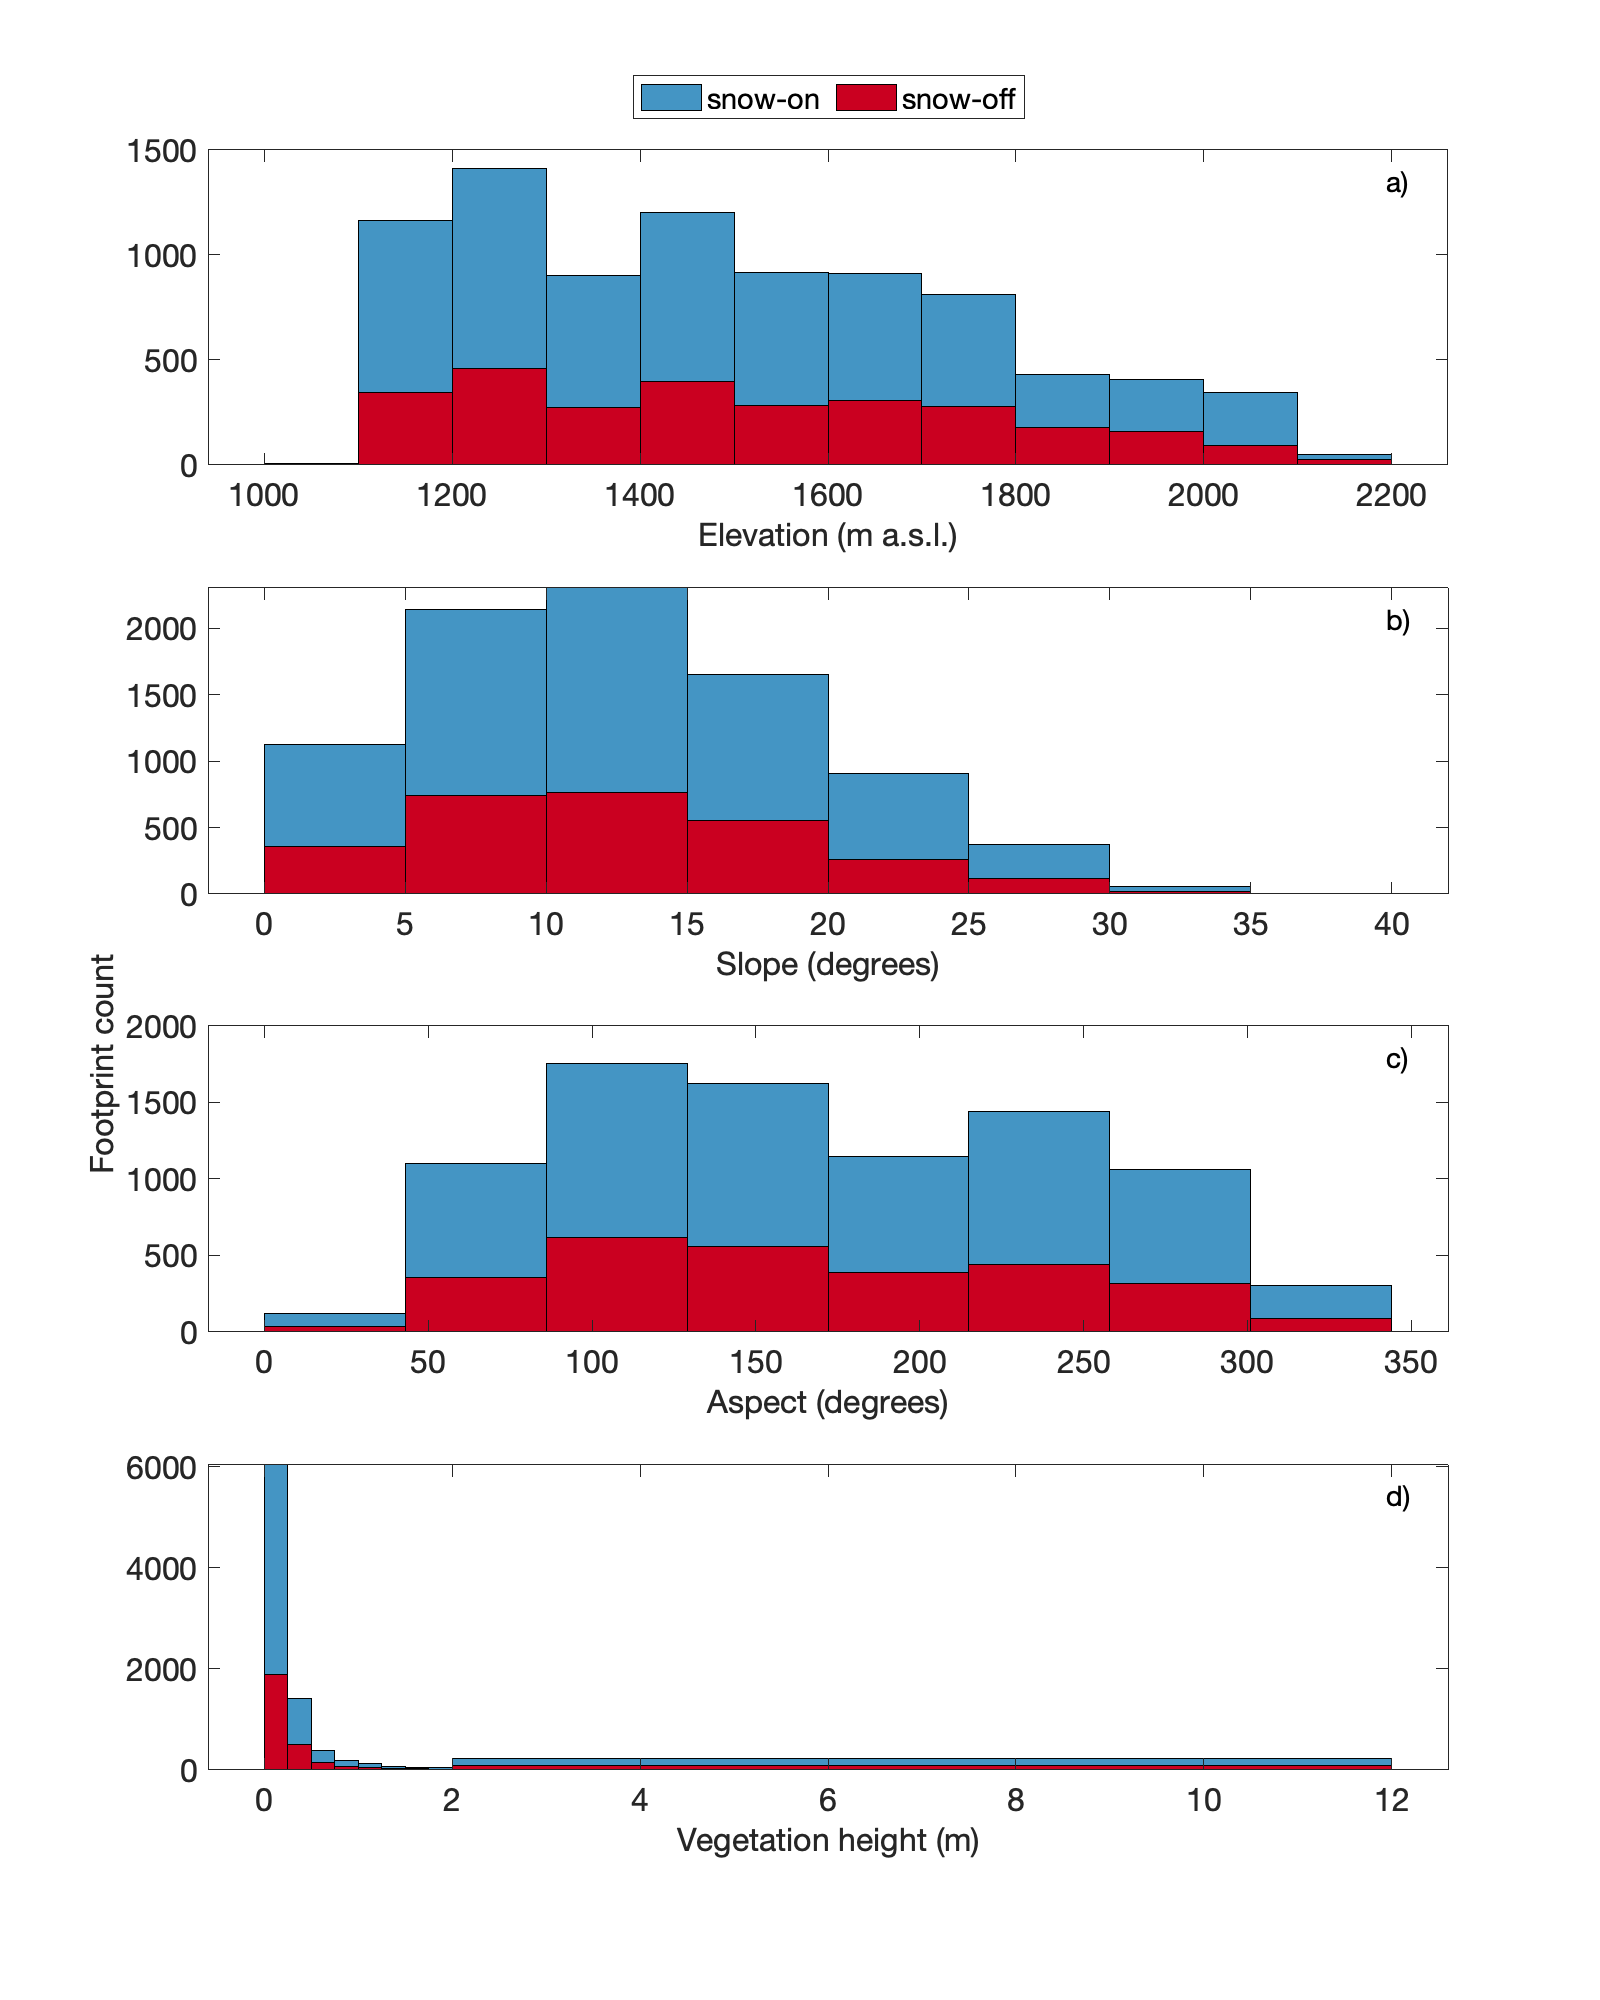

%subplots of seasonal distributions of each terrain parameter to include as
%a supplemental figure to support wonky steep slope & high elevation results (too few observations)

%run previous section to get binwidths
figure; set(gcf,'position',[50 50 800 1000]); clear h;
subplot(4,1,1);
h(1) = histogram(T.ReferenceElevation((T.season==1 | T.season == 2 | T.season == 4))); h(1).BinEdges = elev_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(T.ReferenceElevation((T.season==3))); h(2).BinEdges = elev_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'a) ', 'fontsize', 14);
xlabel('Elevation (m a.s.l.)','fontsize',16); pos = get(gca,'position');
legh = legend(h,'snow-on','snow-off','location','northoutside','orientation','horizontal');
set(gca,'position',pos); clear h pos;
subplot(4,1,2);
h(1) = histogram(T.slope((T.season==1 | T.season == 2 | T.season == 4))); h(1).BinEdges = slope_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(T.slope((T.season==3))); h(2).BinEdges = slope_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'b) ', 'fontsize', 14);
xlabel('Slope (degrees)','fontsize',16);
subplot(4,1,3);
h(1) = histogram(T.aspect((T.season==1 | T.season == 2 | T.season == 4))); h(1).BinEdges = aspect_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(T.aspect((T.season==3))); h(2).BinEdges = aspect_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'c) ', 'fontsize', 14);
xlabel('Aspect (degrees)','fontsize',16); ylbl = ylabel('Footprint count','fontsize',16); set(ylbl,'position',[ylbl.Position(1) 1750 ylbl.Position(3)]);
subplot(4,1,4);
h(1) = histogram(T.VegHeight((T.season==1 | T.season == 2 | T.season == 4))); h(1).BinEdges = vegheight_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(T.VegHeight((T.season==3))); h(2).BinEdges = vegheight_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'd) ', 'fontsize', 14);
xlabel('Vegetation height (m)','fontsize',16); 

%save the figure
saveas(gcf,[abbrev,'_ICESat2terrain_histograms.eps'],'epsc');

## Create a Reference ICESat-2 Elevation Residuals Maps

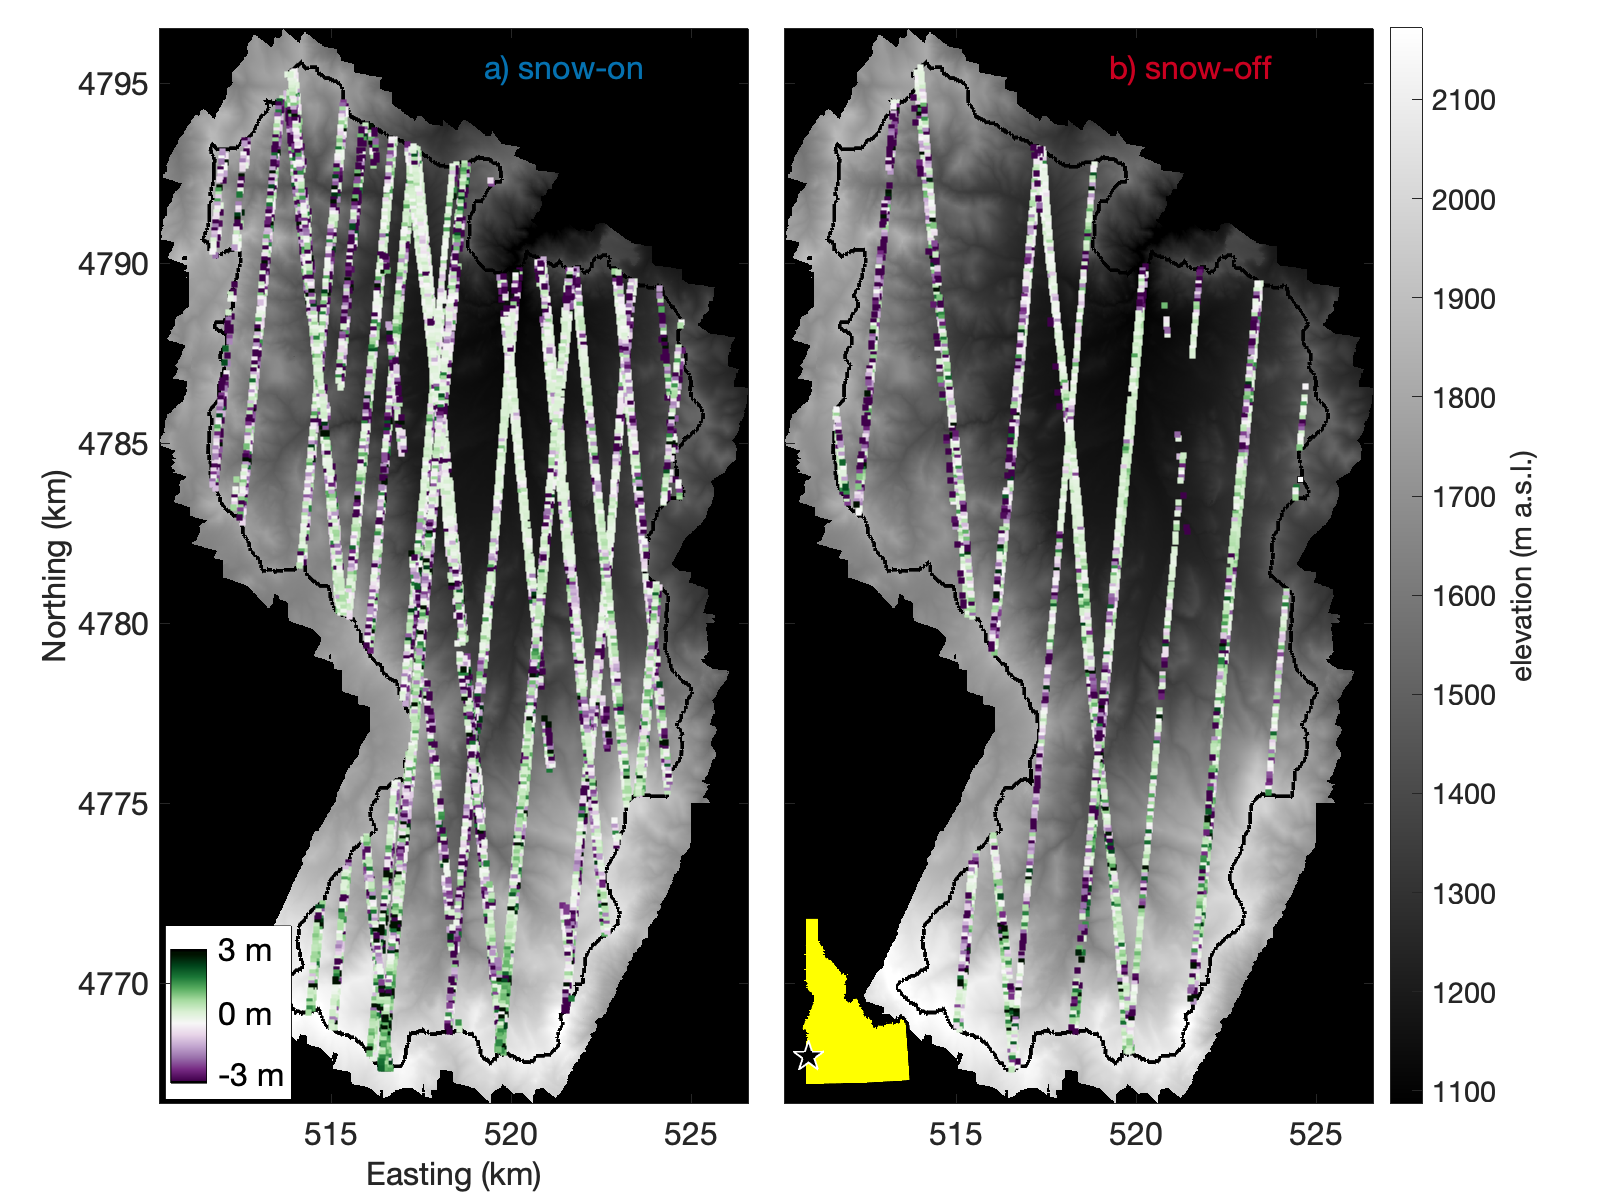

cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);

%set limits of elevation residuals for color stretching
max_residual = 3; %ceil(max(T.('raw_differences'))) %swap this in if you want to stretch colors over the full range of residuals

%set elevation range for maps
xmax = max(max(Z.x)); xmin = min(min(Z.x)); ymax = max(max(Z.y)); ymin = min(min(Z.y));
elev_lims = [min(min(T.ReferenceElevation)) max(max(T.ReferenceElevation))];
elevmap = Z(1).z; elevmap(elevmap<min(elev_lims)) = min(elev_lims)+1;

%create a more detailed colorramp for the elevation residuals than the
%11-color import from colorbrewer
resids_cmap = cblind_colors;
while size(resids_cmap,1) < 500
    for j = 1:2*size(resids_cmap,1)
        if mod(j,2) ~= 0
            new_cmap(j,:) = resids_cmap(ceil(j/2),:);
        else
            if j < 2*size(resids_cmap,1)
                new_cmap(j,:) = resids_cmap(ceil(j/2),:) + 0.5*diff(resids_cmap(ceil(j/2):ceil(j/2)+1,:));
            else
                new_cmap(j,:) = resids_cmap(ceil(j/2),:) + 0.5*diff(resids_cmap(ceil(j/2)-1:ceil(j/2),:));
            end
        end
    end
    resids_cmap = new_cmap; clear new_cmap;
    resids_cmap(resids_cmap<0) = 0;
%     disp(size(resids_cmap,1))
end


%create color matrices for each season
multiplier = size(resids_cmap,1)/(2*max_residual); %solve for a multiplier to map data values onto a colorramp
%snow-on season
acc_diff = T.differences(T.season == 1 | T.season == 2 | T.season == 4); acc_x = T.Easting(T.season == 1 | T.season == 2 | T.season == 4); acc_y = T.Northing(T.season == 1 | T.season == 2 | T.season == 4);
acc_x(isnan(acc_diff)) = []; acc_y(isnan(acc_diff)) = []; acc_diff(isnan(acc_diff)) = [];
acc_colormat = ones(length(acc_diff),3);
for j = 1:length(acc_diff)
    cref = round((acc_diff(j)+max_residual)*multiplier);
    if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
    acc_colormat(j,:) = resids_cmap(cref,:);
end
acc_colormat(acc_colormat<0) = 0;
%snow-off season
abl_diff = T.differences(T.season == 3); abl_x = T.Easting(T.season == 3); abl_y = T.Northing(T.season == 3);
abl_x(isnan(abl_diff)) = []; abl_y(isnan(abl_diff)) = []; abl_diff(isnan(abl_diff)) = [];
abl_colormat = ones(length(abl_diff),3);
for j = 1:length(abl_diff)
    cref = round((abl_diff(j)+max_residual)*multiplier);
    if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
    abl_colormat(j,:) = resids_cmap(cref,:);
end
abl_colormat(abl_colormat<0) = 0;

%create the DEM map
RCEWmap = figure; set(gcf,'position',[0 0 800 600],'DefaultTextFontSize', 16);
asl_cmap = colormap(gray(5001));
for i = 1:2
    subplot(1,2,i)
    imagesc(Z.x,Z.y,elevmap); axis xy equal; % colormap gray;
    colormap(gca,asl_cmap); set(gca,'clim',elev_lims);
    set(gca,'fontsize',16,'xlim',[min(Z.x) max(Z.x)]); hold on; drawnow;
    xticks = get(gca,'xtick'); yticks = get(gca,'ytick');
    subpos = get(gca,'position');
    
    %plot the shapefile outline
    plot([S.X S.X(1)],[S.Y S.Y(1)],'-k','linewidth',2,'marker','none'); hold on;
    
    %set axis labels
    if i == 1
        set(gca,'xticklabels',xticks/1000,'yticklabels',yticks/1000);
    else
        set(gca,'xticklabels',[],'yticklabels',[]);
    end
    if i == 2
        cbar = colorbar; cbar.Label.String = 'elevation (m a.s.l.)';
        set(cbar,'location','eastoutside','orientation','vertical')
    elseif i == 1
        xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
    end
    
    %add data & labels
    if i == 1
        scatter(acc_x,acc_y,17,acc_colormat,'filled','s','MarkerEdgeColor','w','LineWidth',1); hold on;
        scatter(acc_x,acc_y,16,acc_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;
        
        %add colorramp
        rectangle('Position',[xmin+150 ymin+100 3500 5*size(resids_cmap,1)+1300],'facecolor','w','edgecolor','k'); %colorramp legend background
        rectangle('Position',[xmin+300 ymin+5*1+550 1000 5*size(resids_cmap,1)+200],'facecolor','k');
        for j = 1:size(resids_cmap,1)
            plot(squeeze([xmin+315; xmin+1285]),squeeze([ymin+5*j+650; ymin+5*j+650]),'color',resids_cmap(j,:),'linewidth',1.5); hold on;
        end
        text(xmin+1600,ymin+4.95*size(resids_cmap,1)+800,[num2str(max_residual),' m'],'color','k','fontsize',16);
        text(xmin+1600,ymin+2.4*size(resids_cmap,1)+800,'0 m','color','k','fontsize',16);
        text(xmin+1600,ymin+800,['-',num2str(max_residual),' m'],'color','k','fontsize',16);
        text(xmax-0.3*(xmax-xmin),ymax-1050,'a) snow-on','color',seas_cmap(1,:),'fontsize',16,'BackgroundColor','w');
        set(gca,'yticklabel',yticks/1000);
        
        %enlarge subplot
        set(gca,'position',[subpos(1)-0.03 subpos(2)-0.03 1.1*subpos(3) 1.1*subpos(4)])
    elseif i == 2
        scatter(abl_x,abl_y,17,abl_colormat,'filled','s','MarkerEdgeColor','w','LineWidth',1); hold on;
        scatter(abl_x,abl_y,16,abl_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;
        text(xmax-0.3*(xmax-xmin),ymax-1050,'b) snow-off','color',seas_cmap(2,:),'fontsize',16,'BackgroundColor','w');
        set(gca,'yticklabel',[]);
        %enlarge subplot
        set(gca,'position',[subpos(1)-0.08 subpos(2)-0.03 1.1*subpos(3) 1.1*subpos(4)])
    end
    drawnow; hold on;
end

% %overlay a state map in an open corner
% inset_ax = axes('Position', [0.435, 0.09, 0.20, 0.15]);
% % inset_ax = axes('Position', [0.25, 0.117, 0.12, 0.12]);
% fill([state.X(1:end-1) state.X(1)],[state.Y(1:end-1) state.Y(1)],[0 0 0],'facecolor',[1 1 0],'linewidth',2); hold on;
% plot(inset_ax,nanmean(S.X),nanmean(S.Y),'pk','linewidth',1,'markersize',16,'markerfacecolor','k','markeredgecolor','w'); axis xy equal;
% set(inset_ax,'ylim',[4620000 5450000],'XTick',[],'YTick',[],'color','none','XColor','none','YColor','none');

%save!
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);
saveas(gcf,[abbrev,'_ICESat2residuals-map.eps'],'epsc');

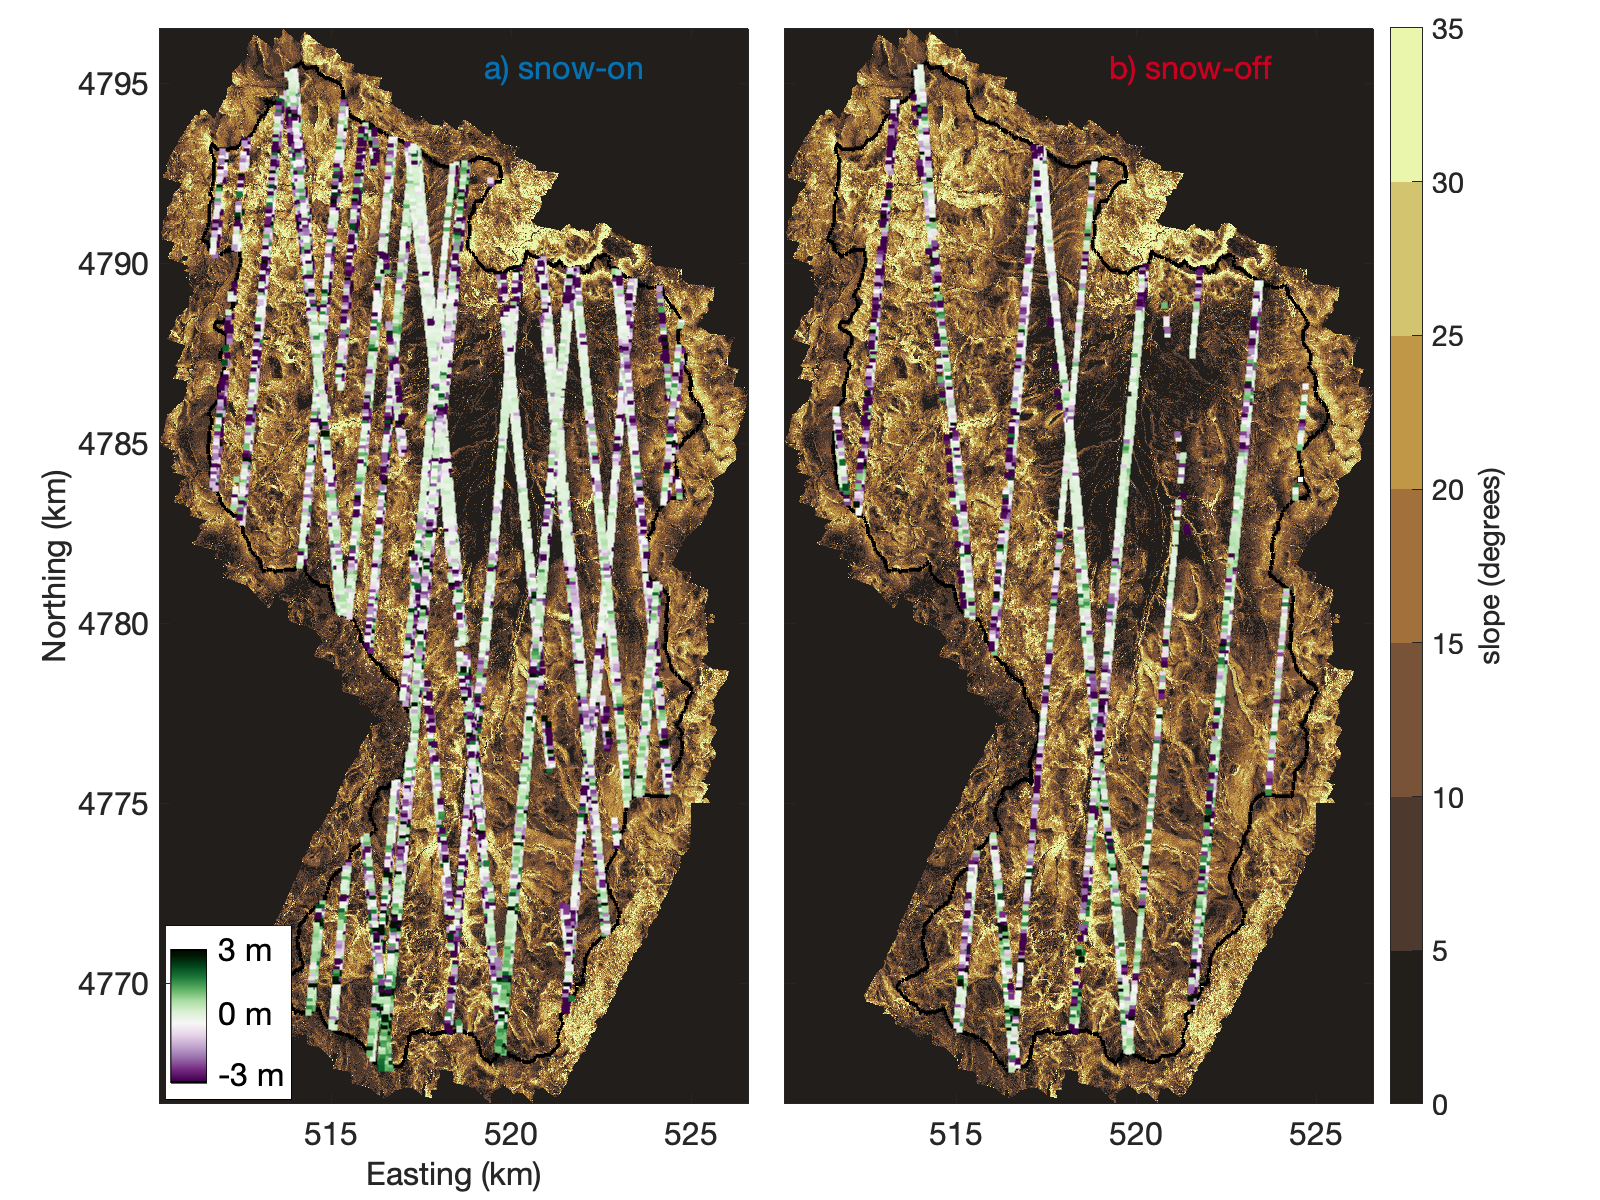


%create a map of residuals overlain on slope
% cd DEMs
% slopefile = dir('*slope.tif');
% slopemap = readgeoraster(slopefile(1).name);
RCEW_slopemap = figure; set(gcf,'position',[0 0 800 600],'DefaultTextFontSize', 16);
clear slope_cmap; slope_cmap = cmocean('turbid',7); slope_cmap = flipud(slope_cmap);
for i = 1:2
    subplot(1,2,i)
    imagesc(Z.x,Z.y,slopemap); %contour(Z.x,Z.y,slopemap,slope_x); 
    axis xy equal; colormap(gca,slope_cmap); set(gca,'clim',[0 35]);
    set(gca,'fontsize',16,'xlim',[min(Z.x) max(Z.x)]); hold on; drawnow;
    xticks = get(gca,'xtick'); yticks = get(gca,'ytick');
    subpos = get(gca,'position');
    
    %plot the shapefile outline
    plot([S.X S.X(1)],[S.Y S.Y(1)],'-k','linewidth',2,'marker','none'); hold on;
    
    %set axis labels
    if i == 1
        set(gca,'xticklabels',xticks/1000,'yticklabels',yticks/1000);
    else
        set(gca,'xticklabels',[],'yticklabels',[]);
    end
    if i == 2
        cbar = colorbar; cbar.Label.String = 'slope (degrees)';
        set(cbar,'location','eastoutside','orientation','vertical')
    elseif i == 1
        xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
    end
    
    %add data & labels
    if i == 1
        scatter(acc_x,acc_y,17,acc_colormat,'filled','s','MarkerEdgeColor','w','LineWidth',1); hold on;
        scatter(acc_x,acc_y,16,acc_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;
        
        %add colorramps
        rectangle('Position',[xmin+150 ymin+100 3500 5*size(resids_cmap,1)+1300],'facecolor','w','edgecolor','k'); %colorramp legend background
        rectangle('Position',[xmin+300 ymin+5*1+550 1000 5*size(resids_cmap,1)+200],'facecolor','k');
        %plot the colorramp
        for j = 1:size(resids_cmap,1)
            plot(squeeze([xmin+315; xmin+1285]),squeeze([ymin+5*j+650; ymin+5*j+650]),'color',resids_cmap(j,:),'linewidth',1.5); hold on;
        end
        text(xmin+1600,ymin+4.95*size(resids_cmap,1)+800,[num2str(max_residual),' m'],'color','k','fontsize',16);
        text(xmin+1600,ymin+2.4*size(resids_cmap,1)+800,'0 m','color','k','fontsize',16);
        text(xmin+1600,ymin+800,['-',num2str(max_residual),' m'],'color','k','fontsize',16);
        text(xmax-0.3*(xmax-xmin),ymax-1050,'a) snow-on','color',seas_cmap(1,:),'fontsize',16,'BackgroundColor','w');
        set(gca,'yticklabel',yticks/1000);
        
        %enlarge subplot
        set(gca,'position',[subpos(1)-0.03 subpos(2)-0.03 1.1*subpos(3) 1.1*subpos(4)])
    elseif i == 2
        scatter(abl_x,abl_y,17,abl_colormat,'filled','s','MarkerEdgeColor','w','LineWidth',1); hold on;
        scatter(abl_x,abl_y,16,abl_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;
        text(xmax-0.3*(xmax-xmin),ymax-1050,'b) snow-off','color',seas_cmap(2,:),'fontsize',16,'BackgroundColor','w');
        set(gca,'yticklabel',[]);
        %enlarge subplot
        set(gca,'position',[subpos(1)-0.08 subpos(2)-0.03 1.1*subpos(3) 1.1*subpos(4)])
    end
    drawnow; hold on;
end

%save!
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);
saveas(gcf,[abbrev,'_ICESat2residuals-slopemap.eps'],'epsc');

##     Plot a map of "snow-on" footprints using the ATL08 brightness_flag

%identify snowy footprints
snow = find(T.Brightness_Flag==1);

%create colormap for snowy footprints (using 'multiplier' specified in previous section)
snow_diff = T.differences(snow); snow_x = T.Easting(snow); snow_y = T.Northing(snow);
snow_x(isnan(snow_diff)) = []; snow_y(isnan(snow_diff)) = []; snow_diff(isnan(snow_diff)) = [];
snow_colormat = ones(length(snow_diff),3);
for j = 1:length(snow_diff)
    cref = round((snow_diff(j)+max_residual)*multiplier);
    if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
    snow_colormat(j,:) = resids_cmap(cref,:);
end
snow_colormat(snow_colormat<0) = 0;

%create the map
clear pl;
snowmap = figure; set(gcf,'position',[0 0 800 800],'DefaultTextFontSize', 16);
map_ax = axes;
imagesc(Z.x,Z.y,Z.z); axis xy equal; % colormap gray; 
cmap = cmocean('topo',10001); colormap(gca,cmap(5001:end,:)); hold on; drawnow;
set(gca,'fontsize',16,'xlim',[min(Z.x) max(Z.x)]);
xticks = get(gca,'xtick'); yticks = get(gca,'ytick');
set(gca,'xticklabels',xticks/1000,'yticklabels',yticks/1000);
xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
cbar = colorbar; set(gca,'clim',[1000 2000]); cbar.Label.String = 'elevation (m a.s.l.)';

%plot the shapefile outline
plot([S.X S.X(1)],[S.Y S.Y(1)],'-','color','k','linewidth',3); hold on;

%plot snowy footprints
scatter(snow_x,snow_y,17,snow_colormat,'filled','s','MarkerEdgeColor','w','LineWidth',1); hold on;
scatter(snow_x,snow_y,16,snow_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;

%add colorramps
rectangle('Position',[max(Z.x)-5100+250 min(Z.y)+250 1500+800 4*length(resids_cmap)+3500],'facecolor','w'); %colorramp legend background
rectangle('Position',[max(Z.x)-5100+475 min(Z.y)+4*1+510 550 4*length(resids_cmap)+80],'facecolor','k');
for i = 1:length(resids_cmap)
    plot(squeeze([max(Z.x)-5100+500; max(Z.x)-5100+1000]),squeeze([min(Z.y)+4*i+550; min(Z.y)+4*i+550]),'color',resids_cmap(i,:),'linewidth',1.5); hold on;
end
text(xmin+1600,ymin+4.95*size(resids_cmap,1)+800,[num2str(max_residual),' m'],'color','k','fontsize',16);
text(xmin+1600,ymin+2.4*size(resids_cmap,1)+800,'0 m','color','k','fontsize',16);
text(xmin+1600,ymin+800,['-',num2str(max_residual),' m'],'color','k','fontsize',16);

%save!
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);
saveas(gcf,[abbrev,'_ICESat2brightness-map.eps'],'epsc');


## Create NDSI maps to corroborate/refute brightness_flag

disp('Must have run 2 preceding mapping sections first to create color maps')

%navigate to Landsat directory & identify image folders
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);
cd Landsats
L8s = dir('LC08*');

%grid the DEM coordinates for interpolation to the NDSI maps
[Zxgrid,Zygrid] = meshgrid(Z.x,Z.y);

%loop through folders & create NDSI maps
disp('Creating NDSI map time series...')
NDSIprof = figure('position',[0 0 800 800]); season_cmap = cmocean('phase',12);
for j = 1:length(L8s)
    disp([num2str(j),' of ',num2str(length(L8s))]);
%     cd_to_date = ['cd ',L8s(j).name]; eval(cd_to_date);
%     
%     %load bands 3 (Green) & 6 (SWIR)
%     ims = dir('LC08*.TIF');
%     if contains(version,'2019')
%         [I3,R3] = geotiffread(ims(5).name);
%         [I6,~] = geotiffread(ims(8).name);
%     else
%         [I3,R3] = readgeoraster(ims(5).name);
%         [I6,~] = readgeoraster(ims(8).name);
%     end
%     clear ims;
%     
%     %calculate NDSI
%     NDSI(j).datestring = L8s(j).name(18:25);
%     if mod(str2num(NDSI(j).datestring(1:4)),4)~=0
%         NDSI(j).date = str2num(NDSI(j).datestring(1:4))+(cumdays(str2num(NDSI(j).datestring(5:6)))+str2num(NDSI(j).datestring(7:8)))./sum(modays);
%     else
%         NDSI(j).date = str2num(NDSI(j).datestring(1:4))+(leap_cumdays(str2num(NDSI(j).datestring(5:6)))+str2num(NDSI(j).datestring(7:8)))./sum(leap_modays);
%     end
%     NDSIdate(j) = NDSI(j).date; %add decimal date to a matrix to help w/ sorting
%     NDSI(j).x = R3.XWorldLimits(1):R3.SampleSpacingInWorldX:R3.XWorldLimits(2);
%     NDSI(j).y = R3.YWorldLimits(2):-R3.SampleSpacingInWorldY:R3.YWorldLimits(1);
%     NDSI(j).map = single((double(I3)-double(I6))./(double(I3)+double(I6)));
%     
%     %mask values outside the catchment
%     [xgrid,ygrid] = meshgrid(NDSI(j).x,NDSI(j).y);
%     in = inpolygon(xgrid,ygrid,S.X,S.Y);
%     ROImask = zeros(size(xgrid)); ROImask(in) = 1;
%     NDSI(j).map(ROImask==0) = NaN;
%     clear in;
%     
%     %interpolate the DEM to the NDSI map
%     NDSI_Z = interp2(Zxgrid,Zygrid,Z.z,xgrid,ygrid);
%     NDSI_Z(ROImask==0) = NaN;
%     
%     %extract the mean NDSI for elevation bins
%     for k = 1:floor(range(NDSI_Z(~isnan(NDSI_Z)))/100)
%         elevbin_ref = find(NDSI_Z >= min(NDSI_Z(~isnan(NDSI_Z)))+((k-1)*100) & NDSI_Z < min(NDSI_Z(~isnan(NDSI_Z)))+(k*100));
%         NDSI(j).elevbin(k) = min(NDSI_Z(~isnan(NDSI_Z)))+((k-1)*100)+50;
%         NDSI(j).elevmean(k) = nanmean(NDSI_Z(elevbin_ref));
%         NDSI(j).mapmean(k) = nanmean(NDSI(j).map(elevbin_ref));
%         clear elevbin_ref;
%     end
    
    %plot the data
    if j == 1
        %plot lines for a legend with a different color for each month
        for p = 1:12
            pl(p) = plot(NDSI(j).elevbin(1),NDSI(j).mapmean(1),'-','linewidth',2,'color',season_cmap(p,:)); hold on;
        end
        
        %plot lines for a legend with different colors for seasons in line with the rest of the figures
        for p = 1:4
            pl(p) = plot(NDSI(j).elevbin(1),NDSI(j).mapmean(1),'-','linewidth',2,'color',seas_cmap(p,:)); hold on;
        end
    end
%     %use a monthly color map
%     plot(NDSI(j).elevbin,NDSI(j).mapmean,'-','linewidth',2,'color',season_cmap(str2num(NDSI(j).datestring(5:6)),:)); hold on;
    %use a seasonal color map
    plot(NDSI(j).elevbin,NDSI(j).mapmean,'-','linewidth',2,'color',seas_cmap(ceil(str2num(NDSI(j).datestring(5:6))./3),:)); hold on;
    drawnow;
    
%     %clear variables & move on
%     clear I3 R3 I6 R6 in xgrid ygrid NDSI_Z ROImask;
%     cd ..
end
set(gca,'fontsize',16,'ylim',[-0.25 0.65]); xlims = get(gca,'xlim');  
% colorref = 3*T.season(T.Brightness_Flag==1);
% scatter(T.ReferenceElevation(T.Brightness_Flag==1),0.65*ones(size(T.ReferenceElevation(T.Brightness_Flag==1))),[],season_cmap(colorref,:)); hold on;
plot([min(xlims) max(xlims)],[0.4 0.4],'--k','linewidth',1.5); set(gca,'xlim',xlims);
xlabel('Elevation (m a.s.l.)','fontsize',16); ylabel('NDSI','fontsize',16); 

%extract NDSI profiles for the closest dates bracketing the snow obervations from the ICESat-2 brightness flag
NDSIscatter = figure('position',[0 0 400 800]);
snow_dates = T.date(T.Brightness_Flag==1);
snow_dates = unique(snow_dates);
for j = 1:length(snow_dates)
    %specify date and coordinates of transect
    ndsi(j).date = snow_dates(j);
    daterefs = find(T.date == snow_dates(j));
    ndsi(j).x = T.Easting(daterefs); ndsi(j).y = T.Northing(daterefs);
    
%     %identify closest dates & pull NDSI profiles from maps
%     preceder = find(NDSIdate<=snow_dates(j),1,'last');
%     ndsi(j).early_transect = interp2(NDSI(preceder).x,NDSI(preceder).y,NDSI(preceder).map,ndsi(j).x,ndsi(j).y);
%     clear preceder xgrid ygrid;
%     follower = find(NDSIdate>snow_dates(j),1,'first');
%     ndsi(j).late_transect = interp2(NDSI(follower).x,NDSI(follower).y,NDSI(follower).map,ndsi(j).x,ndsi(j).y);
%     clear follower xgrid ygrid;
%     ndsi(j).bright = T.Brightness_Flag(daterefs);
    
    %create colormaps
    %profiles
    snowd = T.differences(daterefs); snowz = T.ReferenceElevation(daterefs); snowseas = T.season(daterefs);
    snow = find(ndsi(j).bright==1); 
    for k = 1:length(snow)
        colorref = abs(ceil(snowd(snow(k))*100));
        if colorref > length(win_cmap); colorref = length(win_cmap); end %if it exceeds the max, set as the max
        if colorref == 0; colorref = 1; end %if residual is zero
        
        %determine color based on season
        if snowseas(k) == 1
            snow_colors(k,:) = win_cmap(colorref,:);
        elseif snowseas(k) == 2
            snow_colors(k,:) = spr_cmap(colorref,:);
        end
    end
    %scatterplots
    bright_colors = repmat(ndsi(j).bright,1,3);
    if unique(T.season(daterefs)) == 1
        bright_colors = wincolor.*bright_colors;
    elseif unique(T.season(daterefs)) == 2
        bright_colors = sprcolor.*bright_colors;
    elseif unique(T.season(daterefs)) == 3
        bright_colors = sumcolor.*bright_colors;
    end
    
    %add to the figures
    figure(NDSIprof);
    scatter(snowz(snow),max([ndsi(j).early_transect(snow) ndsi(j).late_transect(snow)],[],2),24,snow_colors,'filled','s','MarkerEdgeColor',seas_cmap(unique(T.season(daterefs)),:),'LineWidth',0.5); hold on;
    clear colorref snow_colors snow snowd snowz snowseas;
    figure(NDSIscatter);
    subplot(length(snow_dates),1,j);
    scatter(T.differences(daterefs),ndsi(j).early_transect,[],bright_colors,'filled'); hold on;
    scatter(T.differences(daterefs),ndsi(j).late_transect,[],bright_colors,'filled'); hold on;
    set(gca,'fontsize',16,'xlim',[0 3],'ylim',[0.4 0.65]);
    clear daterefs bright_colors;
end
xlabel('Elevation residual (m)','fontsize',16); ylabel('NDSI','fontsize',16); 

%add a legend to the profiles
% %legend if using a monthly colormap
% leg = legend(pl,{'Jan.','Feb.','Mar.','Apr.','May','Jun.','Jul.','Aug.','Sep.','Oct.','Nov.','Dec.'});
%legend if using a seasonal colormap
leg = legend(pl,{'winter','spring','summer','autumn'});
set(leg,'location','northwest'); clear pl;


%save!
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);
saveas(NDSIprof,[abbrev,'_NDSI-elevation-brightness_profiles.eps'],'epsc');
saveas(NDSIscatter,[abbrev,'_NDSI-elevation-brightness_scatterplots.eps'],'epsc');



## Fit Trendlines to Elevation Residuals vs. Terrain Parameters


%referencing note: .differences = residuals, .Elevation_Coregistered = average footprint elevation,
%.slope = average footprint slope, .aspect = average footprint aspect,
%.SlopeRange and .ruggedness = footprint slope range and standard deviation

%ELEVATION
%normal
[fwin_z,fwin_zstats] = fit(winT.ReferenceElevation(~isnan(winT.differences) & ~isnan(winT.ReferenceElevation)),winT.differences(~isnan(winT.differences) & ~isnan(winT.ReferenceElevation)),ft1);
[fspr_z,fspr_zstats] = fit(sprT.ReferenceElevation(~isnan(sprT.differences) & ~isnan(sprT.ReferenceElevation)),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.ReferenceElevation)),ft1);
[fsum_z,fsum_zstats] = fit(sumT.ReferenceElevation(~isnan(sumT.differences) & ~isnan(sumT.ReferenceElevation)),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.ReferenceElevation)),ft1);
[ffal_z,ffal_zstats] = fit(falT.ReferenceElevation(~isnan(falT.differences) & ~isnan(falT.ReferenceElevation)),falT.differences(~isnan(falT.differences) & ~isnan(falT.ReferenceElevation)),ft1);
win_zy=fwin_z.p1*elev_x.^2 + fwin_z.p2*elev_x + fwin_z.p3; % get y-vectors for line of best fit
spr_zy=fspr_z.p1*elev_x.^2 + fspr_z.p2*elev_x + fspr_z.p3;
sum_zy=fsum_z.p1*elev_x.^2 + fsum_z.p2*elev_x + fsum_z.p3;
fal_zy=ffal_z.p1*elev_x.^2 + ffal_z.p2*elev_x + ffal_z.p3;
%bisquare (iteratively fit w/ 90% of data to get confidence bounds)
for i = 1:1000
    %WINTER
    [trainset,testset]=getTrainTest([winT.ReferenceElevation(~isnan(winT.differences) & ~isnan(winT.slope)),winT.differences(~isnan(winT.differences) & ~isnan(winT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fwin_zB2(i).p1 = ftout.p1; fwin_zB2(i).p2 = ftout.p2; fwin_zB2(i).p3 = ftout.p3;
    fwin_zB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fwin_zB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    win_residmodeled(i,:) = feval(ftout,elev_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %SPRING
    [trainset,testset]=getTrainTest([sprT.ReferenceElevation(~isnan(sprT.differences) & ~isnan(sprT.slope)),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fspr_zB2(i).p1 = ftout.p1; fspr_zB2(i).p2 = ftout.p2; fspr_zB2(i).p3 = ftout.p3;
    fspr_zB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fspr_zB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    spr_residmodeled(i,:) = feval(ftout,elev_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %SUMMER
    [trainset,testset]=getTrainTest([sumT.ReferenceElevation(~isnan(sumT.differences) & ~isnan(sumT.slope)),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fsum_zB2(i).p1 = ftout.p1; fsum_zB2(i).p2 = ftout.p2; fsum_zB2(i).p3 = ftout.p3;
    fsum_zB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fsum_zB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    sum_residmodeled(i,:) = feval(ftout,elev_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %FALL
    [trainset,testset]=getTrainTest([falT.ReferenceElevation(~isnan(falT.differences) & ~isnan(falT.slope)),falT.differences(~isnan(falT.differences) & ~isnan(falT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    ffal_zB2(i).p1 = ftout.p1; ffal_zB2(i).p2 = ftout.p2; ffal_zB2(i).p3 = ftout.p3;
    ffal_zB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    ffal_zB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    fal_residmodeled(i,:) = feval(ftout,elev_x);
    clear trainset testset ftout ftstats testset_modeled;
    
end
win_zmed=nanmedian(win_residmodeled,1); win_ziqr=iqr(win_residmodeled,1);
spr_zmed=nanmedian(spr_residmodeled,1); spr_ziqr=iqr(spr_residmodeled,1);
sum_zmed=nanmedian(sum_residmodeled,1); sum_ziqr=iqr(sum_residmodeled,1);
fal_zmed=nanmedian(fal_residmodeled,1); fal_ziqr=iqr(fal_residmodeled,1);
clear *_residmodeled;

%SLOPE
%normal
[fwin_s,fwin_sstats] = fit(winT.slope(~isnan(winT.differences) & ~isnan(winT.slope)),winT.differences(~isnan(winT.differences) & ~isnan(winT.slope)),ft1);
[fspr_s,fspr_sstats] = fit(abs(sprT.slope(~isnan(sprT.differences) & ~isnan(sprT.slope))),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.slope)),ft1);
[fsum_s,fsum_sstats] = fit(abs(sumT.slope(~isnan(sumT.differences) & ~isnan(sumT.slope))),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.slope)),ft1);
[ffal_s,ffal_sstats] = fit(abs(falT.slope(~isnan(falT.differences) & ~isnan(falT.slope))),falT.differences(~isnan(falT.differences) & ~isnan(falT.slope)),ft1);
win_sy=fwin_s.p1*slope_x.^2 + fwin_s.p2*slope_x + fwin_s.p3; % get y-vectors for line of best fit
spr_sy=fspr_s.p1*slope_x.^2 + fspr_s.p2*slope_x + fspr_s.p3;
sum_sy=fsum_s.p1*slope_x.^2 + fsum_s.p2*slope_x + fsum_s.p3;
fal_sy=ffal_s.p1*slope_x.^2 + ffal_s.p2*slope_x + ffal_s.p3;
%bisquare (iteratively fit w/ 90% of data to get confidence bounds)
for i = 1:1000
    %WINTER
    [trainset,testset]=getTrainTest([winT.slope(~isnan(winT.differences) & ~isnan(winT.slope)),winT.differences(~isnan(winT.differences) & ~isnan(winT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fwin_sB2(i).p1 = ftout.p1; fwin_sB2(i).p2 = ftout.p2; fwin_sB2(i).p3 = ftout.p3;
    fwin_sB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fwin_sB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    win_residmodeled(i,:) = feval(ftout,slope_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %SPRING
    [trainset,testset]=getTrainTest([sprT.slope(~isnan(sprT.differences) & ~isnan(sprT.slope)),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fspr_sB2(i).p1 = ftout.p1; fspr_sB2(i).p2 = ftout.p2; fspr_sB2(i).p3 = ftout.p3;
    fspr_sB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fspr_sB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    spr_residmodeled(i,:) = feval(ftout,slope_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %SUMMER
    [trainset,testset]=getTrainTest([sumT.slope(~isnan(sumT.differences) & ~isnan(sumT.slope)),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fsum_sB2(i).p1 = ftout.p1; fsum_sB2(i).p2 = ftout.p2; fsum_sB2(i).p3 = ftout.p3;
    fsum_sB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fsum_sB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    sum_residmodeled(i,:) = feval(ftout,slope_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %FALL
    [trainset,testset]=getTrainTest([falT.slope(~isnan(falT.differences) & ~isnan(falT.slope)),falT.differences(~isnan(falT.differences) & ~isnan(falT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    ffal_sB2(i).p1 = ftout.p1; ffal_sB2(i).p2 = ftout.p2; ffal_sB2(i).p3 = ftout.p3;
    ffal_sB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    ffal_sB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    fal_residmodeled(i,:) = feval(ftout,slope_x);
    clear trainset testset ftout ftstats testset_modeled;
    
end
win_smed=nanmedian(win_residmodeled,1); win_siqr=iqr(win_residmodeled,1);
spr_smed=nanmedian(spr_residmodeled,1); spr_siqr=iqr(spr_residmodeled,1);
sum_smed=nanmedian(sum_residmodeled,1); sum_siqr=iqr(sum_residmodeled,1);
fal_smed=nanmedian(fal_residmodeled,1); fal_siqr=iqr(fal_residmodeled,1);
clear *_residmodeled;


%ASPECT
%normal
[fwin_a,fwin_astats] = fit(abs(winT.aspect(~isnan(winT.differences) & ~isnan(winT.aspect))),winT.differences(~isnan(winT.differences) & ~isnan(winT.aspect)),ft2);
[fspr_a,fspr_astats] = fit(abs(sprT.aspect(~isnan(sprT.differences) & ~isnan(sprT.aspect))),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.aspect)),ft2);
[fsum_a,fsum_astats] = fit(abs(sumT.aspect(~isnan(sumT.differences) & ~isnan(sumT.aspect))),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.aspect)),ft2);
[ffal_a,ffal_astats] = fit(abs(falT.aspect(~isnan(falT.differences) & ~isnan(falT.aspect))),falT.differences(~isnan(falT.differences) & ~isnan(falT.aspect)),ft2);
win_ay=fwin_a.a*(aspect_x-180).^2+fwin_a.b; % get y-vectors for line of best fit
spr_ay=fspr_a.a*(aspect_x-180).^2+fspr_a.b;
sum_ay=fsum_a.a*(aspect_x-180).^2+fsum_a.b;
fal_ay=ffal_a.a*(aspect_x-180).^2+ffal_a.b;
%bisquare (iteratively fit w/ 90% of data to get confidence bounds)
for i = 1:1000
    %WINTER
    [trainset,testset]=getTrainTest([winT.aspect(~isnan(winT.differences) & ~isnan(winT.slope)),winT.differences(~isnan(winT.differences) & ~isnan(winT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft2,opts);
    fwin_aB2(i).p1 = ftout.a; fwin_aB2(i).p2 = ftout.b; %fwin_aB2(i).p1 = ftout.p1; 
    fwin_aB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fwin_aB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    win_residmodeled(i,:) = feval(ftout,aspect_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %SPRING
    [trainset,testset]=getTrainTest([sprT.aspect(~isnan(sprT.differences) & ~isnan(sprT.slope)),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft2,opts);
    fspr_aB2(i).p1 = ftout.a; fspr_aB2(i).p2 = ftout.b; %fspr_aB2(i).p1 = ftout.p1; 
    fspr_aB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fspr_aB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    spr_residmodeled(i,:) = feval(ftout,aspect_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %SUMMER
    [trainset,testset]=getTrainTest([sumT.aspect(~isnan(sumT.differences) & ~isnan(sumT.slope)),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft2,opts);
    fsum_aB2(i).p1 = ftout.a; fsum_aB2(i).p2 = ftout.b; %fsum_aB2(i).p1 = ftout.p1; 
    fsum_aB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fsum_aB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    sum_residmodeled(i,:) = feval(ftout,aspect_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %FALL
    [trainset,testset]=getTrainTest([falT.aspect(~isnan(falT.differences) & ~isnan(falT.slope)),falT.differences(~isnan(falT.differences) & ~isnan(falT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft2,opts);
    ffal_aB2(i).p1 = ftout.a; ffal_aB2(i).p2 = ftout.b; %ffal_aB2(i).p1 = ftout.p1; 
    ffal_aB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    ffal_aB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    fal_residmodeled(i,:) = feval(ftout,aspect_x);
    clear trainset testset ftout ftstats testset_modeled;
    
end
win_amed=nanmedian(win_residmodeled,1); win_aiqr=iqr(win_residmodeled,1);
spr_amed=nanmedian(spr_residmodeled,1); spr_aiqr=iqr(spr_residmodeled,1);
sum_amed=nanmedian(sum_residmodeled,1); sum_aiqr=iqr(sum_residmodeled,1);
fal_amed=nanmedian(fal_residmodeled,1); fal_aiqr=iqr(fal_residmodeled,1);
clear *_residmodeled;


% %RUGGEDNESS
% %normal
% [fwin_r,fwin_rstats] = fit(abs(winT.ruggedness(~isnan(winT.differences) & ~isnan(winT.slope))),winT.differences(~isnan(winT.differences) & ~isnan(winT.slope)),ft1);
% [fspr_r,fspr_rstats] = fit(abs(sprT.ruggedness(~isnan(sprT.differences) & ~isnan(sprT.slope))),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.slope)),ft1);
% [fsum_r,fsum_rstats] = fit(abs(sumT.ruggedness(~isnan(sumT.differences) & ~isnan(sumT.slope))),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.slope)),ft1);
% [ffal_r,ffal_rstats] = fit(abs(falT.ruggedness(~isnan(falT.differences) & ~isnan(falT.slope))),falT.differences(~isnan(falT.differences) & ~isnan(falT.slope)),ft1);
% win_ry=fwin_r.p1*rough_x+fwin_r.p2; % get y-vectors for line of best fit
% spr_ry=fspr_r.p1*rough_x+fspr_r.p2;
% sum_ry=fsum_r.p1*rough_x+fsum_r.p2;
% fal_ry=ffal_r.p1*rough_x+ffal_r.p2;
% %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
% for i = 1:1000
%     %WINTER
%     [trainset,testset]=getTrainTest([winT.ruggedness(~isnan(winT.differences) & ~isnan(winT.slope)),winT.differences(~isnan(winT.differences) & ~isnan(winT.slope))],0.9);
%     %apply the fit
%     [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
%     fwin_rB2(i).p1 = ftout.p1; fwin_rB2(i).p2 = ftout.p2;
%     fwin_rB2(i).rsquare = ftstats.rsquare;
%     %compute RMSE
%     testset_modeled = feval(ftout,testset(:,1));
%     fwin_rB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
%     %create a model line
%     win_residmodeled(i,:) = feval(ftout,rough_x);
%     clear trainset testset ftout ftstats testset_modeled;
%     
%     %SPRING
%     [trainset,testset]=getTrainTest([sprT.ruggedness(~isnan(sprT.differences) & ~isnan(sprT.slope)),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.slope))],0.9);
%     %apply the fit
%     [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
%     fspr_rB2(i).p1 = ftout.p1; fspr_rB2(i).p2 = ftout.p2;
%     fspr_rB2(i).rsquare = ftstats.rsquare;
%     %compute RMSE
%     testset_modeled = feval(ftout,testset(:,1));
%     fspr_rB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
%     %create a model line
%     spr_residmodeled(i,:) = feval(ftout,rough_x);
%     clear trainset testset ftout ftstats testset_modeled;
%     
%     %SUMMER
%     [trainset,testset]=getTrainTest([sumT.ruggedness(~isnan(sumT.differences) & ~isnan(sumT.slope)),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.slope))],0.9);
%     %apply the fit
%     [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
%     fsum_rB2(i).p1 = ftout.p1; fsum_rB2(i).p2 = ftout.p2;
%     fsum_rB2(i).rsquare = ftstats.rsquare;
%     %compute RMSE
%     testset_modeled = feval(ftout,testset(:,1));
%     fsum_rB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
%     %create a model line
%     sum_residmodeled(i,:) = feval(ftout,rough_x);
%     clear trainset testset ftout ftstats testset_modeled;
%     
%     %FALL
%     [trainset,testset]=getTrainTest([falT.ruggedness(~isnan(falT.differences) & ~isnan(falT.slope)),falT.differences(~isnan(falT.differences) & ~isnan(falT.slope))],0.9);
%     %apply the fit
%     [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
%     ffal_rB2(i).p1 = ftout.p1; ffal_rB2(i).p2 = ftout.p2;
%     ffal_rB2(i).rsquare = ftstats.rsquare;
%     %compute RMSE
%     testset_modeled = feval(ftout,testset(:,1));
%     ffal_rB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
%     %create a model line
%     fal_residmodeled(i,:) = feval(ftout,rough_x);
%     clear trainset testset ftout ftstats testset_modeled;
%     
% end
% win_rmed=nanmedian(win_residmodeled,1); win_riqr=iqr(win_residmodeled,1);
% spr_rmed=nanmedian(spr_residmodeled,1); spr_riqr=iqr(spr_residmodeled,1);
% sum_rmed=nanmedian(sum_residmodeled,1); sum_riqr=iqr(sum_residmodeled,1);
% fal_rmed=nanmedian(fal_residmodeled,1); fal_riqr=iqr(fal_residmodeled,1);
% clear *_residmodeled;


%VEG HEIGHT
%normal
[fwin_vh,fwin_vhstats] = fit(abs(winT.VegHeight(~isnan(winT.differences) & ~isnan(winT.slope))),winT.differences(~isnan(winT.differences) & ~isnan(winT.slope)),ft1);
[fspr_vh,fspr_vhstats] = fit(abs(sprT.VegHeight(~isnan(sprT.differences) & ~isnan(sprT.slope))),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.slope)),ft1);
[fsum_vh,fsum_vhstats] = fit(abs(sumT.VegHeight(~isnan(sumT.differences) & ~isnan(sumT.slope))),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.slope)),ft1);
[ffal_vh,ffal_vhstats] = fit(abs(falT.VegHeight(~isnan(falT.differences) & ~isnan(falT.slope))),falT.differences(~isnan(falT.differences) & ~isnan(falT.slope)),ft1);
win_vhy=fwin_vh.p1*vegheight_x+fwin_vh.p2; % get y-vectors for line of best fit
spr_vhy=fspr_vh.p1*vegheight_x+fspr_vh.p2;
sum_vhy=fsum_vh.p1*vegheight_x+fsum_vh.p2;
fal_vhy=ffal_vh.p1*vegheight_x+ffal_vh.p2;
%bisquare (iteratively fit w/ 90% of data to get confidence bounds)
for i = 1:1000
    %WINTER
    [trainset,testset]=getTrainTest([winT.VegHeight(~isnan(winT.differences) & ~isnan(winT.slope)),winT.differences(~isnan(winT.differences) & ~isnan(winT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fwin_vhB2(i).p1 = ftout.p1; fwin_vhB2(i).p2 = ftout.p2;
    fwin_vhB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fwin_vhB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    win_residmodeled(i,:) = feval(ftout,vegheight_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %SPRING
    [trainset,testset]=getTrainTest([sprT.VegHeight(~isnan(sprT.differences) & ~isnan(sprT.slope)),sprT.differences(~isnan(sprT.differences) & ~isnan(sprT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fspr_vhB2(i).p1 = ftout.p1; fspr_vhB2(i).p2 = ftout.p2;
    fspr_vhB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fspr_vhB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    spr_residmodeled(i,:) = feval(ftout,vegheight_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %SUMMER
    [trainset,testset]=getTrainTest([sumT.VegHeight(~isnan(sumT.differences) & ~isnan(sumT.slope)),sumT.differences(~isnan(sumT.differences) & ~isnan(sumT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    fsum_vhB2(i).p1 = ftout.p1; fsum_vhB2(i).p2 = ftout.p2;
    fsum_vhB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    fsum_vhB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    sum_residmodeled(i,:) = feval(ftout,vegheight_x);
    clear trainset testset ftout ftstats testset_modeled;
    
    %FALL
    [trainset,testset]=getTrainTest([falT.VegHeight(~isnan(falT.differences) & ~isnan(falT.slope)),falT.differences(~isnan(falT.differences) & ~isnan(falT.slope))],0.9);
    %apply the fit
    [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
    ffal_vhB2(i).p1 = ftout.p1; ffal_vhB2(i).p2 = ftout.p2;
    ffal_vhB2(i).rsquare = ftstats.rsquare;
    %compute RMSE
    testset_modeled = feval(ftout,testset(:,1));
    ffal_vhB2(i).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
    %create a model line
    fal_residmodeled(i,:) = feval(ftout,vegheight_x);
    clear trainset testset ftout ftstats testset_modeled;
    
end
win_vhmed=nanmedian(win_residmodeled,1); win_vhiqr=iqr(win_residmodeled,1);
spr_vhmed=nanmedian(spr_residmodeled,1); spr_vhiqr=iqr(spr_residmodeled,1);
sum_vhmed=nanmedian(sum_residmodeled,1); sum_vhiqr=iqr(sum_residmodeled,1);
fal_vhmed=nanmedian(fal_residmodeled,1); fal_vhiqr=iqr(fal_residmodeled,1);
clear *_residmodeled;

%save fit outputs
disp('Fit curves')
save([abbrev,'-ICESat2_elevation-residuals_v_elevation_fits.mat'],'fwin_zB2','fspr_zB2','fsum_zB2','ffal_zB2',...
    'win_zmed','win_ziqr','spr_zmed','spr_ziqr','sum_zmed','sum_ziqr','fal_zmed','fal_ziqr');
save([abbrev,'-ICESat2_elevation-residuals_v_slope_fits.mat'],'fwin_sB2','fspr_sB2','fsum_sB2','ffal_sB2',...
    'win_smed','win_siqr','spr_smed','spr_siqr','sum_smed','sum_siqr','fal_smed','fal_siqr');
save([abbrev,'-ICESat2_elevation-residuals_v_aspect_fits.mat'],'fwin_aB2','fspr_aB2','fsum_aB2','ffal_aB2',...
    'win_amed','win_aiqr','spr_amed','spr_aiqr','sum_amed','sum_aiqr','fal_amed','fal_aiqr');
% save([abbrev,'-ICESat2_elevation-residuals_v_ruggedness_fits.mat'],'fwin_rB2','fspr_rB2','fsum_rB2','ffal_rB2',...
%     'win_rmed','win_riqr','spr_rmed','spr_riqr','sum_rmed','sum_riqr','fal_rmed','fal_riqr');
save([abbrev,'-ICESat2_elevation-residuals_v_vegheight_fits.mat'],'fwin_vhB2','fspr_vhB2','fsum_vhB2','ffal_vhB2',...
    'win_vhmed','win_vhiqr','spr_vhmed','spr_vhiqr','sum_vhmed','sum_vhiqr','fal_vhmed','fal_vhiqr');


## Create Scatterplots of Elevation Residuals vs Terrain Parameters

close all;

%reload data
load_elevfits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_elevation_fits.mat']; eval(load_elevfits);
load_slopefits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_slope_fits.mat']; eval(load_slopefits);
load_aspectfits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_aspect_fits.mat']; eval(load_aspectfits);
% load_roughfits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_ruggedness_fits.mat']; eval(load_roughfits);
load_vegfits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_vegheight_fits.mat']; eval(load_vegfits);

%compile median trendlines
for i = 1:1000
    %WINTER
    win_zcurve(i) = fwin_zB2(i).p1; win_zslope(i) = fwin_zB2(i).p2; win_zintercept(i) = fwin_zB2(i).p3;
    win_scurve(i) = fwin_sB2(i).p1; win_sslope(i) = fwin_sB2(i).p2; win_sintercept(i) = fwin_sB2(i).p3;
    win_aslope(i) = fwin_aB2(i).p1; win_aintercept(i) = fwin_aB2(i).p2;
%     win_rslope(i) = fwin_rB2(i).p1; win_rintercept(i) = fwin_rB2(i).p2;
    win_vhslope(i) = fwin_vhB2(i).p1; win_vhintercept(i) = fwin_vhB2(i).p2;
    %SPRING
    spr_zcurve(i) = fspr_zB2(i).p1; spr_zslope(i) = fspr_zB2(i).p2; spr_zintercept(i) = fspr_zB2(i).p3;
    spr_scurve(i) = fspr_sB2(i).p1; spr_sslope(i) = fspr_sB2(i).p2; spr_sintercept(i) = fspr_sB2(i).p3;
    spr_aslope(i) = fspr_aB2(i).p1; spr_aintercept(i) = fspr_aB2(i).p2;
%     spr_rslope(i) = fspr_rB2(i).p1; spr_rintercept(i) = fspr_rB2(i).p2;
    spr_vhslope(i) = fspr_vhB2(i).p1; spr_vhintercept(i) = fspr_vhB2(i).p2;
    %SUMMER
    sum_zcurve(i) = fsum_zB2(i).p1; sum_zslope(i) = fsum_zB2(i).p2; sum_zintercept(i) = fsum_zB2(i).p3;
    sum_scurve(i) = fsum_sB2(i).p1; sum_sslope(i) = fsum_sB2(i).p2; sum_sintercept(i) = fsum_sB2(i).p3;
    sum_aslope(i) = fsum_aB2(i).p1; sum_aintercept(i) = fsum_aB2(i).p2;
%     sum_rslope(i) = fsum_rB2(i).p1; sum_rintercept(i) = fsum_rB2(i).p2;
    sum_vhslope(i) = fsum_vhB2(i).p1; sum_vhintercept(i) = fsum_vhB2(i).p2;
    %FALL
    fal_zcurve(i) = ffal_zB2(i).p1; fal_zslope(i) = ffal_zB2(i).p2; fal_zintercept(i) = ffal_zB2(i).p3;
    fal_scurve(i) = ffal_sB2(i).p1; fal_sslope(i) = ffal_sB2(i).p2; fal_sintercept(i) = ffal_sB2(i).p3;
    fal_aslope(i) = ffal_aB2(i).p1; fal_aintercept(i) = ffal_aB2(i).p2;
%     fal_rslope(i) = ffal_rB2(i).p1; fal_rintercept(i) = ffal_rB2(i).p2;
    fal_vhslope(i) = ffal_vhB2(i).p1; fal_vhintercept(i) = ffal_vhB2(i).p2;
end
%create modeled fit lines
%WINTER
win_zB2y=nanmedian(win_zcurve)*elev_x.^2+nanmedian(win_zslope)*elev_x+nanmedian(win_zintercept);
win_sB2y=nanmedian(win_scurve)*slope_x.^2+nanmedian(win_sslope)*slope_x+nanmedian(win_sintercept);
win_aB2y=nanmedian(win_aslope)*(aspect_x-180).^2+nanmedian(win_aintercept); 
% win_rB2y=nanmedian(win_rslope)*rough_x+nanmedian(win_rintercept);
win_vhB2y=nanmedian(win_vhslope)*vegheight_x+nanmedian(win_vhintercept);
%SPRING
spr_zB2y=nanmedian(spr_zcurve)*elev_x.^2+nanmedian(spr_zslope)*elev_x+nanmedian(spr_zintercept);
spr_sB2y=nanmedian(spr_scurve)*slope_x.^2+nanmedian(spr_sslope)*slope_x+nanmedian(spr_sintercept);
spr_aB2y=nanmedian(spr_aslope)*(aspect_x-180).^2+nanmedian(spr_aintercept);
% spr_rB2y=nanmedian(spr_rslope)*rough_x+nanmedian(spr_rintercept);
spr_vhB2y=nanmedian(spr_vhslope)*vegheight_x+nanmedian(spr_vhintercept);
%SUMMER
sum_zB2y=nanmedian(sum_zcurve)*elev_x.^2+nanmedian(sum_zslope)*elev_x+nanmedian(sum_zintercept);
sum_sB2y=nanmedian(sum_scurve)*slope_x.^2+nanmedian(sum_sslope)*slope_x+nanmedian(sum_sintercept);
sum_aB2y=nanmedian(sum_aslope)*(aspect_x-180).^2+nanmedian(sum_aintercept);
% sum_rB2y=nanmedian(sum_rslope)*rough_x+nanmedian(sum_rintercept);
sum_vhB2y=nanmedian(sum_vhslope)*vegheight_x+nanmedian(sum_vhintercept);
%FALL
fal_zB2y=nanmedian(fal_zcurve)*elev_x.^2+nanmedian(fal_zslope)*elev_x+nanmedian(fal_zintercept);
fal_sB2y=nanmedian(fal_scurve)*slope_x.^2+nanmedian(fal_sslope)*slope_x+nanmedian(fal_sintercept);
fal_aB2y=nanmedian(fal_aslope)*(aspect_x-180).^2+nanmedian(fal_aintercept);
% fal_rB2y=nanmedian(fal_rslope)*rough_x+nanmedian(fal_rintercept);
fal_vhB2y=nanmedian(fal_vhslope)*vegheight_x+nanmedian(fal_vhintercept);

%extract RMSEs for each bisquare fit
for i = 1:1000
    win_zRMSE(i) = fwin_zB2(i).rmse; spr_zRMSE(i) = fspr_zB2(i).rmse; sum_zRMSE(i) = fsum_zB2(i).rmse; fal_zRMSE(i) = ffal_zB2(i).rmse; 
    win_sRMSE(i) = fwin_sB2(i).rmse; spr_sRMSE(i) = fspr_sB2(i).rmse; sum_sRMSE(i) = fsum_sB2(i).rmse; fal_sRMSE(i) = ffal_sB2(i).rmse; 
    win_aRMSE(i) = fwin_aB2(i).rmse; spr_aRMSE(i) = fspr_aB2(i).rmse; sum_aRMSE(i) = fsum_aB2(i).rmse; fal_aRMSE(i) = ffal_aB2(i).rmse; 
%     win_rRMSE(i) = fwin_rB2(i).rmse; spr_rRMSE(i) = fspr_rB2(i).rmse; sum_rRMSE(i) = fsum_rB2(i).rmse; fal_rRMSE(i) = ffal_rB2(i).rmse; 
end

%ELEVATION
disp('Residuals vs Elevation:')
figure('position', [0 0 800 800])
sub1 = subplot(3,2,1); pos1 = get(gca,'position');
scatter(winT.ReferenceElevation, winT.differences, 18, 's','markeredgecolor',wincolor,'markerfacecolor','none'); hold on
if height(winT)>2
    plot(elev_x, win_zmed, '-k', 'linewidth', 2);
    plot(elev_x, win_zmed+win_ziqr, '--k', 'linewidth', 2); plot(elev_x, win_zmed-win_ziqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Winter')
if nanmedian(win_zintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fwin_z.p1,2,'significant')),'x+',num2str(round(fwin_z.p2,2,'significant')),' (R^2 = ',num2str(round(fwin_zstats.rsquare,2)),' & RMSE = ',num2str(round(fwin_zstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(win_zcurve),2,'significant')),'x^2+',num2str(round(nanmedian(win_zslope),2,'significant')),'x+',num2str(round(nanmedian(win_zintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_zRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fwin_z.p1,2,'significant')),'x',num2str(round(fwin_z.p2,2,'significant')),' (R^2 = ',num2str(round(fwin_zstats.rsquare,2)),' & RMSE = ',num2str(round(fwin_zstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(win_zcurve),2,'significant')),'x^2+',num2str(round(nanmedian(win_zslope),2,'significant')),'x',num2str(round(nanmedian(win_zintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_zRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
ylbl= ylabel('Elevation residual (m)');
sub2 = subplot(3,2,2); pos2 = get(gca,'position');
scatter(sprT.ReferenceElevation, sprT.differences, 18, 's','markeredgecolor',sprcolor,'markerfacecolor', 'none'); hold on
if height(sprT)>2
    plot(elev_x, spr_zmed, '-k', 'linewidth', 2);
    plot(elev_x, spr_zmed+spr_ziqr, '--k', 'linewidth', 2); plot(elev_x, spr_zmed-spr_ziqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Spring')
if nanmedian(spr_zintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fspr_z.p1,2,'significant')),'x+',num2str(round(fspr_z.p2,2,'significant')),' (R^2 = ',num2str(round(fspr_zstats.rsquare,2)),' & RMSE = ',num2str(round(fspr_zstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(spr_zcurve),2,'significant')),'x^2+',num2str(round(nanmedian(spr_zslope),2,'significant')),'x+',num2str(round(nanmedian(spr_zintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_zRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fspr_z.p1,2,'significant')),'x',num2str(round(fspr_z.p2,2,'significant')),' (R^2 = ',num2str(round(fspr_zstats.rsquare,2)),' & RMSE = ',num2str(round(fspr_zstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(spr_zcurve),2,'significant')),'x^2+',num2str(round(nanmedian(spr_zslope),2,'significant')),'x',num2str(round(nanmedian(spr_zintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_zRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub3 = subplot(3,2,3); pos3 = get(gca,'position');
scatter(sumT.ReferenceElevation, sumT.differences, 18, '.','markeredgecolor',(sumcolor)/1.0,'linewidth',2); hold on
if height(sumT)>2
    plot(elev_x, sum_zmed, '-k', 'linewidth', 2);
    plot(elev_x, sum_zmed+sum_ziqr, '--k', 'linewidth', 2); plot(elev_x, sum_zmed-sum_ziqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Summer')
if nanmedian(sum_zintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fsum_z.p1,2,'significant')),'x+',num2str(round(fsum_z.p2,2,'significant')),' (R^2 = ',num2str(round(fsum_zstats.rsquare,2)),' & RMSE = ',num2str(round(fsum_zstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(sum_zcurve),2,'significant')),'x^2+',num2str(round(nanmedian(sum_zslope),2,'significant')),'x+',num2str(round(nanmedian(sum_zintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_zRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fsum_z.p1,2,'significant')),'x',num2str(round(fsum_z.p2,2,'significant')),' (R^2 = ',num2str(round(fsum_zstats.rsquare,2)),' & RMSE = ',num2str(round(fsum_zstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(sum_zcurve),2,'significant')),'x^2+',num2str(round(nanmedian(sum_zslope),2,'significant')),'x',num2str(round(nanmedian(sum_zintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_zRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
ylbl= ylabel('Elevation residual (m)');
sub4 = subplot(3,2,4); pos4 = get(gca,'position');
sp(1) = scatter(falT.ReferenceElevation, falT.differences, 18, 's','markeredgecolor','k','markerfacecolor','none'); hold on
scatter(falT.ReferenceElevation, falT.differences, 18, 's','markeredgecolor',falcolor,'markerfacecolor','none'); hold on
if height(falT)>2
    sp(2) = plot(elev_x, fal_zmed, '-k', 'linewidth', 2);
    sp(3) = plot(elev_x, fal_zmed+fal_ziqr, '--k', 'linewidth', 2); plot(elev_x, fal_zmed-fal_ziqr, '--k', 'linewidth', 2);
end
leg = legend(sp,'residuals_{summer coreg}','trendline_{median}','trendline_{iqr}','NumColumns',2,'location', 'southoutside');
ylim([-max_diff max_diff]); xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Fall')
if nanmedian(fal_zintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(ffal_z.p1,2,'significant')),'x+',num2str(round(ffal_z.p2,2,'significant')),' (R^2 = ',num2str(round(ffal_zstats.rsquare,2)),' & RMSE = ',num2str(round(ffal_zstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(fal_zcurve),2,'significant')),'x^2+',num2str(round(nanmedian(fal_zslope),2,'significant')),'x+',num2str(round(nanmedian(fal_zintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_zRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(ffal_z.p1,2,'significant')),'x',num2str(round(ffal_z.p2,2,'significant')),' (R^2 = ',num2str(round(ffal_zstats.rsquare,2)),' & RMSE = ',num2str(round(ffal_zstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(fal_zcurve),2,'significant')),'x^2+',num2str(round(nanmedian(fal_zslope),2,'significant')),'x',num2str(round(nanmedian(fal_zintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_zRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
set(gca,'position',pos4); set(leg,'position',[0.38 0.5 0.3 0.1])
clear sp;
sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
if height(winT)>2
    fill([elev_x fliplr(elev_x)],[win_zmed+win_ziqr fliplr(win_zmed-win_ziqr)]-min(win_zmed),wincolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(elev_x, win_zmed-min(win_zmed), '-','color',wincolor,'linewidth', 1); hold on;
end
if height(sprT)>2
    fill([elev_x fliplr(elev_x)],[spr_zmed+spr_ziqr fliplr(spr_zmed-spr_ziqr)]-min(spr_zmed),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(elev_x, spr_zmed-min(spr_zmed), '-','color',sprcolor,'linewidth', 1); hold on;
end
if height(sumT)>2
    fill([elev_x fliplr(elev_x)],[sum_zmed+sum_ziqr fliplr(sum_zmed-sum_ziqr)]-min(sum_zmed),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(elev_x, sum_zmed-min(sum_zmed), '-','color',sumcolor,'linewidth', 1); hold on;
end
if height(falT)>2
    fill([elev_x fliplr(elev_x)],[fal_zmed+fal_ziqr fliplr(fal_zmed-fal_ziqr)]-min(fal_zmed),falcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(elev_x, fal_zmed-min(fal_zmed), '-','color',falcolor,'linewidth', 1); hold on;
end
ylim([min([(win_zmed-win_ziqr)-min(win_zmed) (spr_zmed-spr_ziqr)-min(spr_zmed) (sum_zmed-sum_ziqr)-min(sum_zmed) (fal_zmed-fal_ziqr)-min(fal_zmed)]) max([(win_zmed+win_ziqr)-min(win_zmed) (spr_zmed+spr_ziqr)-min(spr_zmed) (sum_zmed+sum_ziqr)-min(sum_zmed) (fal_zmed+fal_ziqr)-min(fal_zmed)])]); 
xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) seasonal trendlines ','fontsize',16);
xlbl = xlabel('Elevation (m a.s.l.)'); 
ylbl= ylabel('Residual trend (m)');
ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(elev_x)-0.05*(max(elev_x)-min(elev_x)) 0.5*max(ylims) -1]);
% ylbl= ylabel('Elevation residual (m)');
% ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[ylbl_pos(1) 4.75 -1]); clear ylbl_pos;
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
%shift subplots
set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
% hold off
saveas(gcf,[abbrev,'_ICESat2residuals-vs-elevation.eps'],'epsc');

%SLOPE
disp('Residuals vs Slope:')
figure('position', [0 0 800 800])
sub1 = subplot(3,2,1); pos1 = get(gca,'position');
scatter(winT.slope, winT.differences, 18, 's','markeredgecolor',wincolor,'MarkerFaceColor','none'); hold on
if height(winT)>2
    plot(slope_x, win_smed, '-k', 'linewidth', 2);
    plot(slope_x, win_smed+win_siqr, '--k', 'linewidth', 2); plot(slope_x, win_smed-win_siqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Winter')
if nanmedian(win_sintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fwin_s.p1,2,'significant')),'x+',num2str(round(fwin_s.p2,2,'significant')),' (R^2 = ',num2str(round(fwin_sstats.rsquare,2)),' & RMSE = ',num2str(round(fwin_sstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(win_scurve),2,'significant')),'x^2+',num2str(round(nanmedian(win_sslope),2,'significant')),'x+',num2str(round(nanmedian(win_sintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_sRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fwin_s.p1,2,'significant')),'x',num2str(round(fwin_s.p2,2,'significant')),' (R^2 = ',num2str(round(fwin_sstats.rsquare,2)),' & RMSE = ',num2str(round(fwin_sstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(win_scurve),2,'significant')),'x^2+',num2str(round(nanmedian(win_sslope),2,'significant')),'x',num2str(round(nanmedian(win_sintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_sRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
ylbl= ylabel('Elevation residual (m)');
sub2 = subplot(3,2,2); pos2 = get(gca,'position');
scatter(sprT.slope, sprT.differences, 18, 's','markeredgecolor',sprcolor,'markerfacecolor', 'none'); hold on
if height(sprT)>2
    plot(slope_x, spr_smed, '-k', 'linewidth', 2);
    plot(slope_x, spr_smed+spr_siqr, '--k', 'linewidth', 2); plot(slope_x, spr_smed-spr_siqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Spring')
if nanmedian(spr_sintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fspr_s.p1,2,'significant')),'x+',num2str(round(fspr_s.p2,2,'significant')),' (R^2 = ',num2str(round(fspr_sstats.rsquare,2)),' & RMSE = ',num2str(round(fspr_sstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(spr_scurve),2,'significant')),'x^2+',num2str(round(nanmedian(spr_sslope),2,'significant')),'x+',num2str(round(nanmedian(spr_sintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_sRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fspr_s.p1,2,'significant')),'x',num2str(round(fspr_s.p2,2,'significant')),' (R^2 = ',num2str(round(fspr_sstats.rsquare,2)),' & RMSE = ',num2str(round(fspr_sstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(spr_scurve),2,'significant')),'x^2+',num2str(round(nanmedian(spr_sslope),2,'significant')),'x',num2str(round(nanmedian(spr_sintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_sRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub3 = subplot(3,2,3); pos3 = get(gca,'position');
scatter(sumT.slope, sumT.differences, 18, 's','markeredgecolor',sumcolor,'markerfacecolor', 'none'); hold on
if height(sumT)>2
    plot(slope_x, sum_smed, '-k', 'linewidth', 2);
    plot(slope_x, sum_smed+sum_siqr, '--k', 'linewidth', 2); plot(slope_x, sum_smed-sum_siqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Summer')
if nanmedian(sum_sintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fsum_s.p1,2,'significant')),'x+',num2str(round(fsum_s.p2,2,'significant')),' (R^2 = ',num2str(round(fsum_sstats.rsquare,2)),' & RMSE = ',num2str(round(fsum_sstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(sum_scurve),2,'significant')),'x^2+',num2str(round(nanmedian(sum_sslope),2,'significant')),'x+',num2str(round(nanmedian(sum_sintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_sRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fsum_s.p1,2,'significant')),'x',num2str(round(fsum_s.p2,2,'significant')),' (R^2 = ',num2str(round(fsum_sstats.rsquare,2)),' & RMSE = ',num2str(round(fsum_sstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(sum_scurve),2,'significant')),'x^2+',num2str(round(nanmedian(sum_sslope),2,'significant')),'x',num2str(round(nanmedian(sum_sintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_sRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
ylbl= ylabel('Elevation residual (m)');
sub4 = subplot(3,2,4); pos4 = get(gca,'position');
sp(1) = scatter(falT.slope, falT.differences, 18, 's','markeredgecolor','k','markerfacecolor','none'); hold on
scatter(falT.slope, falT.differences, 18, 's','markeredgecolor',falcolor,'markerfacecolor','none'); hold on
if height(falT)>2
    sp(2) = plot(slope_x, fal_smed, '-k', 'linewidth', 2);
    sp(3) = plot(slope_x, fal_smed+fal_siqr, '--k', 'linewidth', 2); plot(slope_x, fal_smed-fal_siqr, '--k', 'linewidth', 2);
end
leg = legend(sp,'residuals_{summer coreg}','trendline_{median}','trendline_{iqr}','NumColumns',2,'location', 'southoutside');
ylim([-max_diff max_diff]); xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Fall')
if nanmedian(fal_sintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(ffal_s.p1,2,'significant')),'x+',num2str(round(ffal_s.p2,2,'significant')),' (R^2 = ',num2str(round(ffal_sstats.rsquare,2)),' & RMSE = ',num2str(round(ffal_sstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(fal_scurve),2,'significant')),'x^2+',num2str(round(nanmedian(fal_sslope),2,'significant')),'x+',num2str(round(nanmedian(fal_sintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_sRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(ffal_s.p1,2,'significant')),'x',num2str(round(ffal_s.p2,2,'significant')),' (R^2 = ',num2str(round(ffal_sstats.rsquare,2)),' & RMSE = ',num2str(round(ffal_sstats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(fal_scurve),2,'significant')),'x^2+',num2str(round(nanmedian(fal_sslope),2,'significant')),'x',num2str(round(nanmedian(fal_sintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_sRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
set(gca,'position',pos4); set(leg,'position',[0.38 0.5 0.3 0.1])
clear sp;
sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
if height(winT)>2
    fill([slope_x fliplr(slope_x)],[win_smed+win_siqr fliplr(win_smed-win_siqr)]-min(win_smed),wincolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(slope_x, win_smed-min(win_smed), '-','color',wincolor,'linewidth', 1); hold on;
end
if height(sprT)>2
    fill([slope_x fliplr(slope_x)],[spr_smed+spr_siqr fliplr(spr_smed-spr_siqr)]-min(spr_smed),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(slope_x, spr_smed-min(spr_smed), '-','color',sprcolor,'linewidth', 1); hold on;
end
if height(sumT)>2
    fill([slope_x fliplr(slope_x)],[sum_smed+sum_siqr fliplr(sum_smed-sum_siqr)]-min(sum_smed),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(slope_x, sum_smed-min(sum_smed), '-','color',sumcolor,'linewidth', 1); hold on;
end
if height(falT)>2
    fill([slope_x fliplr(slope_x)],[fal_smed+fal_siqr fliplr(fal_smed-fal_siqr)]-min(fal_smed),falcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(slope_x, fal_smed-min(fal_smed), '-','color',falcolor,'linewidth', 1); hold on;
end
ylim([min([(win_smed-win_siqr)-min(win_smed) (spr_smed-spr_siqr)-min(spr_smed) (sum_smed-sum_siqr)-min(sum_smed) (fal_smed-fal_siqr)-min(fal_smed)]) max([(win_smed+win_siqr)-min(win_smed) (spr_smed+spr_siqr)-min(spr_smed) (sum_smed+sum_siqr)-min(sum_smed) (fal_smed+fal_siqr)-min(fal_smed)])]); 
xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) seasonal trendlines ','fontsize',16);
xlbl = xlabel('Slope (degrees)'); 
ylbl= ylabel('Residual trend (m)');
ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(slope_x)-0.05*(max(slope_x)-min(slope_x)) 0.5*max(ylims) -1]);
% ylbl= ylabel('Elevation residual (m)');
% ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[ylbl_pos(1) 4 -1]); clear ylbl_pos;
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
%shift subplots
set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
% hold off
saveas(gcf,[abbrev,'_ICESat2residuals-vs-slope.eps'],'epsc');


%ASPECT
disp('Residuals vs Aspect:')
figure('position', [0 0 800 800])
sub1 = subplot(3,2,1); pos1 = get(gca,'position');
scatter(winT.aspect, winT.differences, 18, 's','markeredgecolor',wincolor,'MarkerFaceColor','none'); hold on
if height(winT)>2
    plot(aspect_x, win_amed, '-k', 'linewidth', 2);
    plot(aspect_x, win_amed+win_aiqr, '--k', 'linewidth', 2); plot(aspect_x, win_amed-win_aiqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Winter')
if nanmedian(win_aintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fwin_a.p1,2,'significant')),'x^2+',num2str(round(fwin_a.p2,2,'significant')),'x+',num2str(round(fwin_a.p3,2,'significant')),' (R^2 = ',num2str(round(fwin_astats.rsquare,2)),' & RMSE = ',num2str(round(fwin_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(win_aslope),2,'significant')),'(x-180)^2+',num2str(round(nanmedian(win_aintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_aRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fwin_a.p1,2,'significant')),'x^2',num2str(round(fwin_a.p2,2,'significant')),'x+',num2str(round(fwin_a.p3,2,'significant')),' (R^2 = ',num2str(round(fwin_astats.rsquare,2)),' & RMSE = ',num2str(round(fwin_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(win_aslope),2,'significant')),'(x-180)^2',num2str(round(nanmedian(win_aintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_aRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
ylbl= ylabel('Elevation residual (m)');
sub2 = subplot(3,2,2); pos2 = get(gca,'position');
scatter(sprT.aspect, sprT.differences, 18, 's','markeredgecolor',sprcolor,'markerfacecolor', 'none'); hold on
if height(sprT)>2
    plot(aspect_x, spr_amed, '-k', 'linewidth', 2);
    plot(aspect_x, spr_amed+spr_aiqr, '--k', 'linewidth', 2); plot(aspect_x, spr_amed-spr_aiqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Spring')
if nanmedian(spr_aintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fspr_a.p1,2,'significant')),'x^2+',num2str(round(fspr_a.p2,2,'significant')),'x+',num2str(round(fspr_a.p3,2,'significant')),' (R^2 = ',num2str(round(fspr_astats.rsquare,2)),' & RMSE = ',num2str(round(fspr_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(spr_aslope),2,'significant')),'(x-180)^2+',num2str(round(nanmedian(spr_aintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_aRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fspr_a.p1,2,'significant')),'x^2',num2str(round(fspr_a.p2,2,'significant')),'x+',num2str(round(fspr_a.p3,2,'significant')),' (R^2 = ',num2str(round(fspr_astats.rsquare,2)),' & RMSE = ',num2str(round(fspr_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(spr_aslope),2,'significant')),'(x-180)^2',num2str(round(nanmedian(spr_aintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_aRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub3 = subplot(3,2,3); pos3 = get(gca,'position');
scatter(sumT.aspect, sumT.differences, 18, 's','markeredgecolor',sumcolor,'markerfacecolor', 'none'); hold on
if height(sumT)>2
    plot(aspect_x, sum_amed, '-k', 'linewidth', 2);
    plot(aspect_x, sum_amed+sum_aiqr, '--k', 'linewidth', 2); plot(aspect_x, sum_amed-sum_aiqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Summer')
if nanmedian(sum_aintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fsum_a.p1,2,'significant')),'x^2+',num2str(round(fsum_a.p2,2,'significant')),'x+',num2str(round(fsum_a.p3,2,'significant')),' (R^2 = ',num2str(round(fsum_astats.rsquare,2)),' & RMSE = ',num2str(round(fsum_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(sum_aslope),2,'significant')),'(x-180)^2+',num2str(round(nanmedian(sum_aintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_aRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fsum_a.p1,2,'significant')),'x^2',num2str(round(fsum_a.p2,2,'significant')),'x+',num2str(round(fsum_a.p3,2,'significant')),' (R^2 = ',num2str(round(fsum_astats.rsquare,2)),' & RMSE = ',num2str(round(fsum_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(sum_aslope),2,'significant')),'(x-180)^2',num2str(round(nanmedian(sum_aintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_aRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
ylbl= ylabel('Elevation residual (m)');
sub4 = subplot(3,2,4); pos4 = get(gca,'position');
sp(1) = scatter(falT.aspect, falT.differences, 18, 's','markeredgecolor','k','markerfacecolor','none'); hold on
scatter(falT.aspect, falT.differences, 18, 's','markeredgecolor',falcolor,'markerfacecolor','none'); hold on
if height(falT)>2
    sp(2) = plot(aspect_x, fal_amed, '-k', 'linewidth', 2);
    sp(3) = plot(aspect_x, fal_amed+fal_aiqr, '--k', 'linewidth', 2); plot(aspect_x, fal_amed-fal_aiqr, '--k', 'linewidth', 2);
end
leg = legend(sp,'residuals_{summer coreg}','trendline_{median}','trendline_{iqr}','NumColumns',2,'location', 'southoutside');
ylim([-max_diff max_diff]); xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Fall')
if nanmedian(fal_aintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(ffal_a.p1,2,'significant')),'x^2+',num2str(round(ffal_a.p2,2,'significant')),'x+',num2str(round(ffal_a.p3,2,'significant')),' (R^2 = ',num2str(round(ffal_astats.rsquare,2)),' & RMSE = ',num2str(round(ffal_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(fal_aslope),2,'significant')),'(x-180)^2+',num2str(round(nanmedian(fal_aintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_aRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(ffal_a.p1,2,'significant')),'x^2',num2str(round(ffal_a.p2,2,'significant')),'x+',num2str(round(ffal_a.p3,2,'significant')),' (R^2 = ',num2str(round(ffal_astats.rsquare,2)),' & RMSE = ',num2str(round(ffal_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(fal_aslope),2,'significant')),'(x-180)^2',num2str(round(nanmedian(fal_aintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_aRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
set(gca,'position',pos4); set(leg,'position',[0.38 0.5 0.3 0.1])
clear sp;
sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
if height(winT)>2
    fill([aspect_x fliplr(aspect_x)],[win_amed+win_aiqr fliplr(win_amed-win_aiqr)]-min(win_amed),wincolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(aspect_x, win_amed-min(win_amed), '-','color',wincolor,'linewidth', 1); hold on;
end
if height(sprT)>2
    fill([aspect_x fliplr(aspect_x)],[spr_amed+spr_aiqr fliplr(spr_amed-spr_aiqr)]-min(spr_amed),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(aspect_x, spr_amed-min(spr_amed), '-','color',sprcolor,'linewidth', 1); hold on;
end
if height(sumT)>2
    fill([aspect_x fliplr(aspect_x)],[sum_amed+sum_aiqr fliplr(sum_amed-sum_aiqr)]-min(sum_amed),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(aspect_x, sum_amed-min(sum_amed), '-','color',sumcolor,'linewidth', 1); hold on;
end
if height(falT)>2
    fill([aspect_x fliplr(aspect_x)],[fal_amed+fal_aiqr fliplr(fal_amed-fal_aiqr)]-min(fal_amed),falcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(aspect_x, fal_amed-min(fal_amed), '-','color',falcolor,'linewidth', 1); hold on;
end
ylim([min([(win_amed-win_aiqr)-min(win_amed) (spr_amed-spr_aiqr)-min(spr_amed) (sum_amed-sum_aiqr)-min(sum_amed) (fal_amed-fal_aiqr)-min(fal_amed)]) max([(win_amed+win_aiqr)-min(win_amed) (spr_amed+spr_aiqr)-min(spr_amed) (sum_amed+sum_aiqr)-min(sum_amed) (fal_amed+fal_aiqr)-min(fal_amed)])]); 
xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) seasonal trendlines ','fontsize',16);
xlbl = xlabel('Aspect (degrees)'); 
ylbl= ylabel('Residual trend (m)');
ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(aspect_x)-0.05*(max(aspect_x)-min(aspect_x)) 0.5*max(ylims) -1]);
% ylbl= ylabel('Elevation residual (m)');
% ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[ylbl_pos(1) 5.5 -1]); clear ylbl_pos;
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
%shift subplots
set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
% hold off
saveas(gcf,[abbrev,'_ICESat2residuals-vs-aspect.eps'],'epsc');

% 
% %RUGGEDNESS
% disp('Residuals vs Ruggedness:')
% figure('position', [0 0 800 800])
% sub1 = subplot(3,2,1); pos1 = get(gca,'position');
% scatter(winT.ruggedness, winT.differences, 18, 's','markeredgecolor',wincolor,'MarkerFaceColor','none'); hold on
% if height(winT)>2
%     plot(rough_x, win_rmed, '-k', 'linewidth', 2);
%     plot(rough_x, win_rmed+win_riqr, '--k', 'linewidth', 2); plot(rough_x, win_rmed-win_riqr, '--k', 'linewidth', 2);
% end
% ylim([-max_diff max_diff]); xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% disp('Winter')
% if nanmedian(win_rintercept) > 0
%     text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
% %     disp(['y_{ordinary}=',num2str(round(fwin_a.p1,2,'significant')),'x+',num2str(round(fwin_a.p2,2,'significant')),' (R^2 = ',num2str(round(fwin_astats.rsquare,2)),' & RMSE = ',num2str(round(fwin_astats.rmse,2)),')']);
%     disp(['y=',num2str(round(nanmedian(win_rslope),2,'significant')),'x+',num2str(round(nanmedian(win_rintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_rRMSE),2)),')']);
% else
%     text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
% %     disp(['y_{ordinary}=',num2str(round(fwin_a.p1,2,'significant')),'x',num2str(round(fwin_a.p2,2,'significant')),' (R^2 = ',num2str(round(fwin_astats.rsquare,2)),' & RMSE = ',num2str(round(fwin_astats.rmse,2)),')']);
%     disp(['y=',num2str(round(nanmedian(win_rslope),2,'significant')),'x',num2str(round(nanmedian(win_rintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_rRMSE),2)),')']);
% end
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% ylbl= ylabel('Elevation residual (m)');
% sub2 = subplot(3,2,2); pos2 = get(gca,'position');
% scatter(sprT.ruggedness, sprT.differences, 18, 's','markeredgecolor',sprcolor,'markerfacecolor', 'none'); hold on
% if height(sprT)>2
%     plot(rough_x, spr_rmed, '-k', 'linewidth', 2);
%     plot(rough_x, spr_rmed+spr_riqr, '--k', 'linewidth', 2); plot(rough_x, spr_rmed-spr_riqr, '--k', 'linewidth', 2);
% end
% ylim([-max_diff max_diff]); xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% disp('Spring')
% if nanmedian(spr_rintercept) > 0
%     text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
% %     disp(['y_{ordinary}=',num2str(round(fspr_r.p1,2,'significant')),'x+',num2str(round(fspr_r.p2,2,'significant')),' (R^2 = ',num2str(round(fspr_rstats.rsquare,2)),' & RMSE = ',num2str(round(fspr_rstats.rmse,2)),')']);
%     disp(['y=',num2str(round(nanmedian(spr_rslope),2,'significant')),'x+',num2str(round(nanmedian(spr_rintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_rRMSE),2)),')']);
% else
%     text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
% %     disp(['y_{ordinary}=',num2str(round(fspr_r.p1,2,'significant')),'x',num2str(round(fspr_r.p2,2,'significant')),' (R^2 = ',num2str(round(fspr_rstats.rsquare,2)),' & RMSE = ',num2str(round(fspr_rstats.rmse,2)),')']);
%     disp(['y=',num2str(round(nanmedian(spr_rslope),2,'significant')),'x',num2str(round(nanmedian(spr_rintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_rRMSE),2)),')']);
% end
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% sub3 = subplot(3,2,3); pos3 = get(gca,'position');
% scatter(sumT.ruggedness, sumT.differences, 18, 's','markeredgecolor',sumcolor,'markerfacecolor', 'none'); hold on
% if height(sumT)>2
%     plot(rough_x, sum_rmed, '-k', 'linewidth', 2);
%     plot(rough_x, sum_rmed+sum_riqr, '--k', 'linewidth', 2); plot(rough_x, sum_rmed-sum_riqr, '--k', 'linewidth', 2);
% end
% ylim([-max_diff max_diff]); xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% disp('Summer')
% if nanmedian(sum_rintercept) > 0
%     text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16);
% %     disp(['y_{ordinary}=',num2str(round(fsum_r.p1,2,'significant')),'x+',num2str(round(fsum_r.p2,2,'significant')),' (R^2 = ',num2str(round(fsum_rstats.rsquare,2)),' & RMSE = ',num2str(round(fsum_rstats.rmse,2)),')']);
%     disp(['y=',num2str(round(nanmedian(sum_rslope),2,'significant')),'x+',num2str(round(nanmedian(sum_rintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_rRMSE),2)),')']);
% else
%     text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16);
% %     disp(['y_{ordinary}=',num2str(round(fsum_r.p1,2,'significant')),'x',num2str(round(fsum_r.p2,2,'significant')),' (R^2 = ',num2str(round(fsum_rstats.rsquare,2)),' & RMSE = ',num2str(round(fsum_rstats.rmse,2)),')']);
%     disp(['y=',num2str(round(nanmedian(sum_rslope),2,'significant')),'x',num2str(round(nanmedian(sum_rintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_rRMSE),2)),')']);
% end
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% ylbl= ylabel('Elevation residual (m)');
% sub4 = subplot(3,2,4); pos4 = get(gca,'position');
% sp(1) = scatter(falT.ruggedness, falT.differences, 18, 's','markeredgecolor','k','markerfacecolor','none'); hold on
% scatter(falT.ruggedness, falT.differences, 18, 's','markeredgecolor',falcolor,'markerfacecolor','none'); hold on
% if height(falT)>2
%     sp(2) = plot(rough_x, fal_rmed, '-k', 'linewidth', 2);
%     sp(3) = plot(rough_x, fal_rmed+fal_riqr, '--k', 'linewidth', 2); plot(rough_x, fal_rmed-fal_riqr, '--k', 'linewidth', 2);
% end
% leg = legend(sp,'residuals_{summer coreg}','trendline_{median}','trendline_{iqr}','NumColumns',2,'location', 'southoutside');
% ylim([-max_diff max_diff]); xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% disp('Fall')
% if nanmedian(fal_rintercept) > 0
%     text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
% %     disp(['y_{ordinary}=',num2str(round(ffal_r.p1,2,'significant')),'x+',num2str(round(ffal_r.p2,2,'significant')),' (R^2 = ',num2str(round(ffal_rstats.rsquare,2)),' & RMSE = ',num2str(round(ffal_rstats.rmse,2)),')']);
%     disp(['y=',num2str(round(nanmedian(fal_rslope),2,'significant')),'x+',num2str(round(nanmedian(fal_rintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_rRMSE),2)),')']);
% else
%     text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
% %     disp(['y_{ordinary}=',num2str(round(ffal_r.p1,2,'significant')),'x',num2str(round(ffal_r.p2,2,'significant')),' (R^2 = ',num2str(round(ffal_rstats.rsquare,2)),' & RMSE = ',num2str(round(ffal_rstats.rmse,2)),')']);
%     disp(['y=',num2str(round(nanmedian(fal_rslope),2,'significant')),'x',num2str(round(nanmedian(fal_rintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_rRMSE),2)),')']);
% end
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% set(gca,'position',pos4); set(leg,'position',[0.38 0.5 0.3 0.1])
% clear sp;
% sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
% if height(winT)>2
%     fill([rough_x fliplr(rough_x)],[win_rmed+win_riqr fliplr(win_rmed-win_riqr)]-min(win_rmed),wincolor,'edgecolor','none','facealpha',0.5); hold on;
%     plot(rough_x, win_rmed-min(win_rmed), '-','color',wincolor,'linewidth', 1); hold on;
% end
% if height(sprT)>2
%     fill([rough_x fliplr(rough_x)],[spr_rmed+spr_riqr fliplr(spr_rmed-spr_riqr)]-min(spr_rmed),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
%     plot(rough_x, spr_rmed-min(spr_rmed), '-','color',sprcolor,'linewidth', 1); hold on;
% end
% if height(sumT)>2
%     fill([rough_x fliplr(rough_x)],[sum_rmed+sum_riqr fliplr(sum_rmed-sum_riqr)]-min(sum_rmed),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
%     plot(rough_x, sum_rmed-min(sum_rmed), '-','color',sumcolor,'linewidth', 1); hold on;
% end
% if height(falT)>2
%     fill([rough_x fliplr(rough_x)],[fal_rmed+fal_riqr fliplr(fal_rmed-fal_riqr)]-min(fal_rmed),falcolor,'edgecolor','none','facealpha',0.5); hold on;
%     plot(rough_x, fal_rmed-min(fal_rmed), '-','color',falcolor,'linewidth', 1); hold on;
% end
% ylim([min([(win_rmed-win_riqr)-min(win_rmed) (spr_rmed-spr_riqr)-min(spr_rmed) (sum_rmed-sum_riqr)-min(sum_rmed) (fal_rmed-fal_riqr)-min(fal_rmed)]) max([(win_rmed+win_riqr)-min(win_rmed) (spr_rmed+spr_riqr)-min(spr_rmed) (sum_rmed+sum_riqr)-min(sum_rmed) (fal_rmed+fal_riqr)-min(fal_rmed)])]); 
% xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) seasonal trendlines ','fontsize',16);
% xlbl = xlabel('Ruggedness index'); 
% ylbl= ylabel('Residual trend (m)');
% ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(rough_x)-0.05*(max(rough_x)-min(rough_x)) 0.5*max(ylims) -1]);
% % ylbl= ylabel('Elevation residual (m)');
% % ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[ylbl_pos(1) 0.33 -1]); clear ylbl_pos;
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% %shift subplots
% set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
% set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
% set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
% set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
% set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
% % hold off
% saveas(gcf,[abbrev,'_ICESat2residuals-vs-ruggedness.eps'],'epsc');

%VEGETATION HEIGHT
%extract RMSEs for each bisquare fit
for i = 1:1000
    win_vhRMSE(i) = fwin_vhB2(i).rmse; spr_vhRMSE(i) = fspr_vhB2(i).rmse; sum_vhRMSE(i) = fsum_vhB2(i).rmse; fal_vhRMSE(i) = ffal_vhB2(i).rmse; 
end

%plot
disp('Residuals vs. Vegetation Height')
figure('position', [0 0 800 800])
sub1 = subplot(3,2,1); pos1 = get(gca,'position');
scatter(winT.VegHeight, winT.differences, 18, 's','markeredgecolor',wincolor,'MarkerFaceColor','none'); hold on
if height(winT)>2
    plot(vegheight_x, win_vhmed, '-k', 'linewidth', 2);
    plot(vegheight_x, win_vhmed+win_vhiqr, '--k', 'linewidth', 2); plot(vegheight_x, win_vhmed-win_vhiqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(vegheight_x) 5]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Winter')
if nanmedian(win_vhintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fwin_a.p1,2,'significant')),'x+',num2str(round(fwin_a.p2,2,'significant')),' (R^2 = ',num2str(round(fwin_astats.rsquare,2)),' & RMSE = ',num2str(round(fwin_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(win_vhslope),2,'significant')),'x+',num2str(round(nanmedian(win_vhintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_vhRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fwin_a.p1,2,'significant')),'x',num2str(round(fwin_a.p2,2,'significant')),' (R^2 = ',num2str(round(fwin_astats.rsquare,2)),' & RMSE = ',num2str(round(fwin_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(win_vhslope),2,'significant')),'x',num2str(round(nanmedian(win_vhintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_vhRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
ylbl= ylabel('Elevation residual (m)');
sub2 = subplot(3,2,2); pos2 = get(gca,'position');
scatter(sprT.VegHeight, sprT.differences, 18, 's','markeredgecolor',sprcolor,'MarkerFaceColor','none'); hold on
if height(sprT)>2
    plot(vegheight_x, spr_vhmed, '-k', 'linewidth', 2);
    plot(vegheight_x, spr_vhmed+spr_vhiqr, '--k', 'linewidth', 2); plot(vegheight_x, spr_vhmed-spr_vhiqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(vegheight_x) 5]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Spring')
if nanmedian(spr_vhintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fspr_a.p1,2,'significant')),'x+',num2str(round(fspr_a.p2,2,'significant')),' (R^2 = ',num2str(round(fspr_astats.rsquare,2)),' & RMSE = ',num2str(round(fspr_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(spr_vhslope),2,'significant')),'x+',num2str(round(nanmedian(spr_vhintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_vhRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fspr_a.p1,2,'significant')),'x',num2str(round(fspr_a.p2,2,'significant')),' (R^2 = ',num2str(round(fspr_astats.rsquare,2)),' & RMSE = ',num2str(round(fspr_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(spr_vhslope),2,'significant')),'x',num2str(round(nanmedian(spr_vhintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_vhRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub3 = subplot(3,2,3); pos3 = get(gca,'position');
scatter(sumT.VegHeight, sumT.differences, 18, 's','markeredgecolor',sumcolor,'markerfacecolor', 'none'); hold on
if height(sumT)>2
    plot(vegheight_x, sum_vhmed, '-k', 'linewidth', 2);
    plot(vegheight_x, sum_vhmed+sum_vhiqr, '--k', 'linewidth', 2); plot(vegheight_x, sum_vhmed-sum_vhiqr, '--k', 'linewidth', 2);
end
ylim([-max_diff max_diff]); xlim([min(vegheight_x) 5]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Summer')
if nanmedian(sum_vhintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fsum_a.p1,2,'significant')),'x+',num2str(round(fsum_a.p2,2,'significant')),' (R^2 = ',num2str(round(fsum_astats.rsquare,2)),' & RMSE = ',num2str(round(fsum_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(sum_vhslope),2,'significant')),'x+',num2str(round(nanmedian(sum_vhintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_vhRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(fsum_a.p1,2,'significant')),'x',num2str(round(fsum_a.p2,2,'significant')),' (R^2 = ',num2str(round(fsum_astats.rsquare,2)),' & RMSE = ',num2str(round(fsum_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(sum_vhslope),2,'significant')),'x',num2str(round(nanmedian(sum_vhintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_vhRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
ylbl= ylabel('Elevation residual (m)');
sub4 = subplot(3,2,4); pos4 = get(gca,'position');
sp(1) = scatter(falT.VegHeight, falT.differences, 18, 's','markeredgecolor','k','markerfacecolor','none'); hold on
scatter(falT.VegHeight, falT.differences, 18, 's','markeredgecolor',falcolor,'markerfacecolor','none'); hold on
if height(falT)>2
    sp(2) = plot(vegheight_x, fal_vhmed, '-k', 'linewidth', 2);
    sp(3) = plot(vegheight_x, fal_vhmed+fal_vhiqr, '--k', 'linewidth', 2); plot(vegheight_x, fal_vhmed-fal_vhiqr, '--k', 'linewidth', 2);
end
leg = legend(sp,'residuals_{summer coreg}','trendline_{median}','trendline_{iqr}','NumColumns',2,'location', 'southoutside');
ylim([-max_diff max_diff]); xlim([min(vegheight_x) 5]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Fall')
if nanmedian(fal_vhintercept) > 0
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(ffal_a.p1,2,'significant')),'x+',num2str(round(ffal_a.p2,2,'significant')),' (R^2 = ',num2str(round(ffal_astats.rsquare,2)),' & RMSE = ',num2str(round(ffal_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(fal_vhslope),2,'significant')),'x+',num2str(round(nanmedian(fal_vhintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_vhRMSE),2)),')']);
else
    text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16);
%     disp(['y_{ordinary}=',num2str(round(ffal_a.p1,2,'significant')),'x',num2str(round(ffal_a.p2,2,'significant')),' (R^2 = ',num2str(round(ffal_astats.rsquare,2)),' & RMSE = ',num2str(round(ffal_astats.rmse,2)),')']);
    disp(['y=',num2str(round(nanmedian(fal_vhslope),2,'significant')),'x',num2str(round(nanmedian(fal_vhintercept),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_vhRMSE),2)),')']);
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
set(gca,'position',pos4); set(leg,'position',[0.38 0.5 0.3 0.1])
clear sp;
sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
if height(winT)>2
    fill([vegheight_x fliplr(vegheight_x)],[win_vhmed+win_vhiqr fliplr(win_vhmed-win_vhiqr)]-min(win_vhmed),wincolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(vegheight_x, win_vhmed-min(win_vhmed), '-','color',wincolor,'linewidth', 1); hold on;
end
if height(sprT)>2
    fill([vegheight_x fliplr(vegheight_x)],[spr_vhmed+spr_vhiqr fliplr(spr_vhmed-spr_vhiqr)]-min(spr_vhmed),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(vegheight_x, spr_vhmed-min(spr_vhmed), '-','color',sprcolor,'linewidth', 1); hold on;
end
if height(sumT)>2
    fill([vegheight_x fliplr(vegheight_x)],[sum_vhmed+sum_vhiqr fliplr(sum_vhmed-sum_vhiqr)]-min(sum_vhmed),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(vegheight_x, sum_vhmed-min(sum_vhmed), '-','color',sumcolor,'linewidth', 1); hold on;
end
if height(falT)>2
    fill([vegheight_x fliplr(vegheight_x)],[fal_vhmed+fal_vhiqr fliplr(fal_vhmed-fal_vhiqr)]-min(fal_vhmed),falcolor,'edgecolor','none','facealpha',0.5); hold on;
    plot(vegheight_x, fal_vhmed-min(fal_vhmed), '-','color',falcolor,'linewidth', 1); hold on;
end
ylim([min([(win_vhmed-win_vhiqr)-min(win_vhmed) (spr_vhmed-spr_vhiqr)-min(spr_vhmed) (sum_vhmed-sum_vhiqr)-min(sum_vhmed) (fal_vhmed-fal_vhiqr)-min(fal_vhmed)]) max([(win_vhmed+win_vhiqr)-min(win_vhmed) (spr_vhmed+spr_vhiqr)-min(spr_vhmed) (sum_vhmed+sum_vhiqr)-min(sum_vhmed) (fal_vhmed+fal_vhiqr)-min(fal_vhmed)])]); 
xlim([min(vegheight_x) max(vegheight_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) seasonal trendlines ','fontsize',16);
xlbl = xlabel('Vegetation height (m)'); 
ylbl= ylabel('Residual trend (m)');
ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(vegheight_x)-0.05*(max(vegheight_x)-min(vegheight_x)) 0.5*max(ylims) -1]);
% ylbl= ylabel('Elevation residual (m)');
% ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[ylbl_pos(1)-0.2 18 -1]);
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
%shift subplots
set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
% hold off
saveas(gcf,[abbrev,'_ICESat2residuals-vs-vegheight.eps'],'epsc');
clear *iqr *med *RMSE *intercept *slope *curve;
